# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(david_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

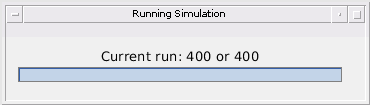

target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    41.2835       NaN       NaN       NaN       NaN
   41.2723       NaN       NaN       NaN       NaN
   41.2770       NaN       NaN       NaN       NaN
   41.2877       NaN       NaN       NaN       NaN
   41.2819       NaN       NaN       NaN       NaN
   37.6664       NaN       NaN       NaN       NaN
   36.1392       NaN       NaN       NaN       NaN
   29.9785   30.2159       NaN       NaN       NaN
   28.8417       NaN       NaN       NaN       NaN
   29.6202       NaN       NaN       NaN       NaN


actual_ranges =     40    40    40    40    40    40    40    40    40    40


estimated_velocities =    -0.0003       NaN       NaN       NaN       NaN
    0.0015       NaN       NaN       NaN       NaN
   -0.0010       NaN       NaN       NaN       NaN
    0.0001       NaN       NaN       NaN       NaN
    0.0005       NaN       NaN       NaN       NaN
    0.0124       NaN       NaN       NaN       NaN
   -0.0063       NaN       NaN       NaN       NaN
   -0.0335  -26.2579       NaN       NaN       NaN
   -0.0107       NaN       NaN       NaN       NaN
   -0.0160       NaN       NaN       NaN       NaN


actual_velocities =      0     0     0     0     0     0     0     0     0     0


detected =      1     1     1     1     1     1     1     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges =     1.2835
    1.2723
    1.2770
    1.2877
    1.2819
    2.3336
    3.8608
         0
         0
         0


percent_error_velocities =     0.0003
    0.0015
    0.0010
    0.0001
    0.0005
    0.0124
    0.0063
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges =    10.0000    9.0331    8.0662    7.0993    6.1324    5.1655    4.1986    3.2317    2.2648    1.2979


estimated_velocities =    NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities =     29    29    29    29    29    29    29    29    29    29


detected =      0     0     0     0     0     0     0     0     0     0


col_detection =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =   121.6963       NaN       NaN       NaN       NaN
  121.9610       NaN       NaN       NaN       NaN
  122.5917       NaN       NaN       NaN       NaN
  119.8235       NaN       NaN       NaN       NaN
  120.1238       NaN       NaN       NaN       NaN
  121.3110  120.6005       NaN       NaN       NaN
  120.8701       NaN       NaN       NaN       NaN
  118.7805       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =   122.0000  121.5999  121.1998  120.7997  120.3996  119.9995  119.5994  119.1993  118.7992  118.3991


estimated_velocities =    11.9916       NaN       NaN       NaN       NaN
   11.9966       NaN       NaN       NaN       NaN
   12.0318       NaN       NaN       NaN       NaN
   11.9937       NaN       NaN       NaN       NaN
   11.9870       NaN       NaN       NaN       NaN
    0.2347   11.9328       NaN       NaN       NaN
   12.0240       NaN       NaN       NaN       NaN
   12.0171       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     12    12    12    12    12    12    12    12    12    12


detected =      1     1     1     1     1     1     1     1     0     0


col_detection =      1
     1
     1
     1
     1
     2
     1
     1
     0
     0


false_positives =      0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges =     0.3037
    0.3611
    1.3919
    0.9762
    0.2759
    0.6010
    1.2707
    0.4188
         0
         0


percent_error_velocities =     0.0084
    0.0034
    0.0318
    0.0063
    0.0130
    0.0672
    0.0240
    0.0171
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    58.1450       NaN       NaN       NaN       NaN
   57.7945       NaN       NaN       NaN       NaN
   58.6851       NaN       NaN       NaN       NaN
   60.0567       NaN       NaN       NaN       NaN
   59.7359       NaN       NaN       NaN       NaN
   57.9606       NaN       NaN       NaN       NaN
   57.1090       NaN       NaN       NaN       NaN
   50.6347       NaN       NaN       NaN       NaN
   50.8787       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =    58.0000   58.3668   58.7335   59.1003   59.4670   59.8338   60.2005   60.5673   60.9340   61.3008


estimated_velocities =   -10.9829       NaN       NaN       NaN       NaN
  -10.9854       NaN       NaN       NaN       NaN
  -10.9719       NaN       NaN       NaN       NaN
  -10.9808       NaN       NaN       NaN       NaN
  -10.9820       NaN       NaN       NaN       NaN
  -10.9928       NaN       NaN       NaN       NaN
  -11.0207       NaN       NaN       NaN       NaN
  -11.0676       NaN       NaN       NaN       NaN
  -11.0333       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =    -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected =      1     1     1     1     1     1     1     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges =     0.1450
    0.5723
    0.0484
    0.9565
    0.2689
    1.8732
    3.0916
         0
         0
         0


percent_error_velocities =     0.0171
    0.0146
    0.0281
    0.0192
    0.0180
    0.0072
    0.0207
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    30.8260       NaN       NaN       NaN       NaN
   27.8810       NaN       NaN       NaN       NaN
   28.4063       NaN       NaN       NaN       NaN
   28.8430       NaN       NaN       NaN       NaN
   29.3988       NaN       NaN       NaN       NaN
   26.5460       NaN       NaN       NaN       NaN
   27.2078       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =    30.0000   29.6666   29.3332   28.9998   28.6663   28.3329   27.9995   27.6661   27.3327   26.9993


estimated_velocities =     9.9912       NaN       NaN       NaN       NaN
    9.9936       NaN       NaN       NaN       NaN
    9.9936       NaN       NaN       NaN       NaN
    9.9935       NaN       NaN       NaN       NaN
    9.9935       NaN       NaN       NaN       NaN
    9.9825       NaN       NaN       NaN       NaN
   10.0002       NaN       NaN       NaN       NaN
    9.9712       NaN       NaN       NaN       NaN
    9.9347       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     10    10    10    10    10    10    10    10    10    10


detected =      1     1     1     1     1     1     1     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges =     0.8260
    1.7855
    0.9269
    0.1568
    0.7324
    1.7869
    0.7917
         0
         0
         0


percent_error_velocities =     0.0088
    0.0064
    0.0064
    0.0065
    0.0065
    0.0175
    0.0002
         0
         0
         0


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =   140.8077       NaN       NaN       NaN       NaN
  143.5435       NaN       NaN       NaN       NaN
  142.6803       NaN       NaN       NaN       NaN
  141.8004       NaN       NaN       NaN       NaN
  144.9949       NaN       NaN       NaN       NaN
  143.5211       NaN       NaN       NaN       NaN
  144.2706       NaN       NaN       NaN       NaN
  144.5824       NaN       NaN       NaN       NaN
  146.8245       NaN       NaN       NaN       NaN
  147.1572       NaN       NaN       NaN       NaN


actual_ranges =   141.0000  141.5001  142.0002  142.5004  143.0005  143.5006  144.0007  144.5009  145.0010  145.5011


estimated_velocities =   -14.9915       NaN       NaN       NaN       NaN
  -14.9876       NaN       NaN       NaN       NaN
  -14.9988       NaN       NaN       NaN       NaN
  -14.9928       NaN       NaN       NaN       NaN
  -14.9821       NaN       NaN       NaN       NaN
  -14.9870       NaN       NaN       NaN       NaN
  -14.9804       NaN       NaN       NaN       NaN
  -15.0050       NaN       NaN       NaN       NaN
  -15.0800       NaN       NaN       NaN       NaN
  -15.0002       NaN       NaN       NaN       NaN


actual_velocities =    -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected =      1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1923
    2.0434
    0.6801
    0.7000
    1.9944
    0.0205
    0.2699
    0.0815
    1.8235
    1.6561


percent_error_velocities = 10×1
    0.0085
    0.0124
    0.0012
    0.0072
    0.0179
    0.0130
    0.0196
    0.0050
    0.0800
    0.0002


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   34.3893       NaN       NaN       NaN       NaN
   34.7704       NaN       NaN       NaN       NaN
   32.2732       NaN       NaN       NaN       NaN
   32.6882       NaN       NaN       NaN       NaN
   33.2879       NaN       NaN       NaN       NaN
   34.2165       NaN       NaN       NaN       NaN
   31.9081       NaN       NaN       NaN       NaN
   32.4432       NaN       NaN       NaN       NaN
   21.2130       NaN       NaN       NaN       NaN
   20.2480       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   34.5666   34.1331   33.6997   33.2662   32.8328   32.3994   31.9659   31.5325   31.0990


estimated_velocities = 10×5
   13.0154       NaN       NaN       NaN       NaN
   13.0135       NaN       NaN       NaN       NaN
   13.0133       NaN       NaN       NaN       NaN
   13.0160       NaN       NaN       NaN       NaN
   13.0158       NaN       NaN       NaN       NaN
   13.0075       NaN       NaN       NaN       NaN
   12.9977       NaN       NaN       NaN       NaN
   12.9975       NaN       NaN       NaN       NaN
   13.0185       NaN       NaN       NaN       NaN
   12.9644       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.6107
    0.2038
    1.8599
    1.0115
    0.0217
    1.3837
    0.4913
    0.4772
         0
         0


percent_error_velocities = 10×1
    0.0154
    0.0135
    0.0133
    0.0160
    0.0158
    0.0075
    0.0023
    0.0025
         0
         0


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   14.0000   13.5332   13.0664   12.5997   12.1329   11.6661   11.1993   10.7325   10.2658    9.7990


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   18.1906       NaN       NaN       NaN       NaN
   18.6149       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   17.0000   16.6332   16.2665   15.8997   15.5330   15.1662   14.7995   14.4327   14.0660   13.6992


estimated_velocities = 10×5
   10.9829       NaN       NaN       NaN       NaN
   10.9833       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   10.9841       NaN       NaN       NaN       NaN
   10.9833       NaN       NaN       NaN       NaN
   10.9825       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     0     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     0
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.1906
    1.9816
         0
    4.4309
    4.7977
    3.0244
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0171
    0.0167
         0
    0.0159
    0.0167
    0.0175
         0
         0
         0
         0


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   20.3307       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   18.0000   17.1331   16.2662   15.3994   14.5325   13.6656   12.7987   11.9319   11.0650   10.1981


estimated_velocities = 10×5
   25.9191       NaN       NaN       NaN       NaN
   25.9862       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     0     0     0     0     0     0     0     0


col_detection = 10×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.3307
    1.0575
         0
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0809
    0.0138
         0
         0
         0
         0
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  115.6116       NaN       NaN       NaN       NaN
  115.4072       NaN       NaN       NaN       NaN
  115.1822       NaN       NaN       NaN       NaN
  114.9933       NaN       NaN       NaN       NaN
  114.8421       NaN       NaN       NaN       NaN
  114.7402       NaN       NaN       NaN       NaN
  114.2794       NaN       NaN       NaN       NaN
  114.3932       NaN       NaN       NaN       NaN
  115.4764       NaN       NaN       NaN       NaN
  115.6481       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  114.0000  114.1334  114.2667  114.4001  114.5335  114.6668  114.8002  114.9336  115.0669  115.2003


estimated_velocities = 10×5
   -4.0016       NaN       NaN       NaN       NaN
   -4.0120       NaN       NaN       NaN       NaN
   -4.0162       NaN       NaN       NaN       NaN
   -4.0119       NaN       NaN       NaN       NaN
   -4.0078       NaN       NaN       NaN       NaN
   -4.0126       NaN       NaN       NaN       NaN
   -4.0555       NaN       NaN       NaN       NaN
   -3.9917       NaN       NaN       NaN       NaN
   -4.0360       NaN       NaN       NaN       NaN
   -4.0233       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.6116
    1.2738
    0.9155
    0.5932
    0.3086
    0.0734
    0.5208
    0.5404
    0.4095
    0.4478


percent_error_velocities = 10×1
    0.0016
    0.0120
    0.0162
    0.0119
    0.0078
    0.0126
    0.0555
    0.0083
    0.0360
    0.0233


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  137.5805       NaN       NaN       NaN       NaN
  137.3846       NaN       NaN       NaN       NaN
  137.0984       NaN       NaN       NaN       NaN
  136.9287       NaN       NaN       NaN       NaN
  140.5485       NaN       NaN       NaN       NaN
  137.9113       NaN       NaN       NaN       NaN
  140.6004  140.2482  140.2701       NaN       NaN
  140.4139       NaN       NaN       NaN       NaN
  140.4993       NaN       NaN       NaN       NaN
  140.9819       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  138.0000  138.1667  138.3334  138.5001  138.6668  138.8335  139.0002  139.1670  139.3337  139.5004


estimated_velocities = 10×5
   -4.9939       NaN       NaN       NaN       NaN
   -4.9872       NaN       NaN       NaN       NaN
   -4.9931       NaN       NaN       NaN       NaN
   -4.9928       NaN       NaN       NaN       NaN
   -4.9851       NaN       NaN       NaN       NaN
   -4.9934       NaN       NaN       NaN       NaN
  -22.5084   12.3536   -5.0296       NaN       NaN
   -4.9952       NaN       NaN       NaN       NaN
   -4.9973       NaN       NaN       NaN       NaN
   -5.0400       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     3
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.4195
    0.7821
    1.2350
    1.5714
    1.8817
    0.9222
    1.2699
    1.2469
    1.1656
    1.4816


percent_error_velocities = 10×1
    0.0061
    0.0128
    0.0069
    0.0072
    0.0149
    0.0066
    0.0296
    0.0048
    0.0027
    0.0400


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   11.0000   11.7002   12.4003   13.1005   13.8007   14.5009   15.2010   15.9012   16.6014   17.3015


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -20.9801       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     0     0     0     0     0     0     0     0     0     1


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
         0
    3.0291


percent_error_velocities = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0199


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   89.7925       NaN       NaN       NaN       NaN
   90.0319       NaN       NaN       NaN       NaN
   90.3648       NaN       NaN       NaN       NaN
   87.5795       NaN       NaN       NaN       NaN
   87.8031       NaN       NaN       NaN       NaN
   85.5396       NaN       NaN       NaN       NaN
   87.9459       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   77.6746       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   90.0000   89.7333   89.4665   89.1998   88.9331   88.6663   88.3996   88.1329   87.8661   87.5994


estimated_velocities = 10×5
    8.0137       NaN       NaN       NaN       NaN
    8.0144       NaN       NaN       NaN       NaN
    8.0171       NaN       NaN       NaN       NaN
    8.0189       NaN       NaN       NaN       NaN
    8.0179       NaN       NaN       NaN       NaN
    7.9829       NaN       NaN       NaN       NaN
    7.9706       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    7.9732       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.2075
    0.2986
    0.8982
    1.6203
    1.1300
    3.1268
    0.4537
         0
         0
         0


percent_error_velocities = 10×1
    0.0137
    0.0144
    0.0171
    0.0189
    0.0179
    0.0171
    0.0294
         0
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   32.1320       NaN       NaN       NaN       NaN
   32.9643       NaN       NaN       NaN       NaN
   33.9843       NaN       NaN       NaN       NaN
   31.3277       NaN       NaN       NaN       NaN
   31.9037       NaN       NaN       NaN       NaN
   32.1529       NaN       NaN       NaN       NaN
   24.2046       NaN       NaN       NaN       NaN
   29.8367       NaN       NaN       NaN       NaN
   19.9438   19.7164       NaN       NaN       NaN
   28.1785       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   33.4332   32.8664   32.2996   31.7328   31.1660   30.5992   30.0324   29.4656   28.8988


estimated_velocities = 10×5
   17.0016       NaN       NaN       NaN       NaN
   17.0038       NaN       NaN       NaN       NaN
   17.0023       NaN       NaN       NaN       NaN
   17.0009       NaN       NaN       NaN       NaN
   17.0034       NaN       NaN       NaN       NaN
   16.9663       NaN       NaN       NaN       NaN
   17.0170       NaN       NaN       NaN       NaN
   16.9956       NaN       NaN       NaN       NaN
   27.1114   17.0103       NaN       NaN       NaN
   17.0033       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     0     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     0


percent_error_ranges = 10×1
    1.8680
    0.4689
    1.1179
    0.9718
    0.1709
    0.9869
         0
    0.1956
         0
    0.7203


percent_error_velocities = 10×1
    0.0016
    0.0038
    0.0023
    0.0009
    0.0034
    0.0337
         0
    0.0044
         0
    0.0033


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   38.7457       NaN       NaN       NaN       NaN
   36.9324       NaN       NaN       NaN       NaN
   35.1760       NaN       NaN       NaN       NaN
   33.0212       NaN       NaN       NaN       NaN
   34.6372       NaN       NaN       NaN       NaN
   28.2714       NaN       NaN       NaN       NaN
   31.0686       NaN       NaN       NaN       NaN
   22.3190       NaN       NaN       NaN       NaN
   19.8744       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   39.0000   37.8664   36.7328   35.5992   34.4656   33.3320   32.1983   31.0647   29.9311   28.7975


estimated_velocities = 10×5
   33.9922       NaN       NaN       NaN       NaN
   33.9949       NaN       NaN       NaN       NaN
   33.9952       NaN       NaN       NaN       NaN
   33.9950       NaN       NaN       NaN       NaN
   33.9914       NaN       NaN       NaN       NaN
   33.9634       NaN       NaN       NaN       NaN
   33.9874       NaN       NaN       NaN       NaN
   33.9833       NaN       NaN       NaN       NaN
   33.9784       NaN       NaN       NaN       NaN
   34.0199       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.2543
    0.9340
    1.5568
    2.5779
    0.1717
    5.0605
    1.1297
         0
         0
         0


percent_error_velocities = 10×1
    0.0078
    0.0051
    0.0048
    0.0050
    0.0086
    0.0366
    0.0126
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   18.1906       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   18.8310       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   19.8949       NaN       NaN       NaN       NaN
   18.8060       NaN       NaN       NaN       NaN
   19.1170       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   15.0000   15.5335   16.0669   16.6004   17.1339   17.6673   18.2008   18.7342   19.2677   19.8012


estimated_velocities = 10×5
  -15.9839       NaN       NaN       NaN       NaN
  -15.9841       NaN       NaN       NaN       NaN
  -15.9743       NaN       NaN       NaN       NaN
  -15.9809       NaN       NaN       NaN       NaN
  -15.9833       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -15.9777       NaN       NaN       NaN       NaN
  -15.9840       NaN       NaN       NaN       NaN
  -15.9690       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     0     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    3.1906
    4.7972
    4.2637
    2.2306
    1.0567
         0
         0
    1.1606
    0.4617
    0.6842


percent_error_velocities = 10×1
    0.0161
    0.0159
    0.0257
    0.0191
    0.0167
         0
         0
    0.0223
    0.0160
    0.0310


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  135.2410       NaN       NaN       NaN       NaN
  138.3524       NaN       NaN       NaN       NaN
  141.1324       NaN       NaN       NaN       NaN
  139.5330       NaN       NaN       NaN       NaN
  141.8819       NaN       NaN       NaN       NaN
  139.5052       NaN       NaN       NaN       NaN
  142.2732       NaN       NaN       NaN       NaN
  142.6895       NaN       NaN       NaN       NaN
  143.2214       NaN       NaN       NaN       NaN
  145.4006       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.7669  138.5337  139.3006  140.0674  140.8343  141.6011  142.3680  143.1348  143.9017


estimated_velocities = 10×5
  -23.0204       NaN       NaN       NaN       NaN
  -23.0162       NaN       NaN       NaN       NaN
  -23.0017       NaN       NaN       NaN       NaN
  -23.0203       NaN       NaN       NaN       NaN
  -23.0015       NaN       NaN       NaN       NaN
  -22.9738       NaN       NaN       NaN       NaN
  -23.0827       NaN       NaN       NaN       NaN
  -23.0548       NaN       NaN       NaN       NaN
  -22.9980       NaN       NaN       NaN       NaN
  -22.9914       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.7590
    0.5855
    2.5987
    0.2324
    1.8145
    1.3290
    0.6721
    0.3215
    0.0866
    1.4989


percent_error_velocities = 10×1
    0.0204
    0.0162
    0.0017
    0.0203
    0.0015
    0.0262
    0.0827
    0.0548
    0.0020
    0.0086


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   34.1325       NaN       NaN       NaN       NaN
   32.3373       NaN       NaN       NaN       NaN
   30.5837       NaN       NaN       NaN       NaN
   31.7416       NaN       NaN       NaN       NaN
   30.0438       NaN       NaN       NaN       NaN
   27.5054       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   33.7997   32.5994   31.3991   30.1988   28.9985   27.7982   26.5980   25.3977   24.1974


estimated_velocities = 10×5
   35.3867       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
   13.7376       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.8675
    1.4624
    2.0157
    0.3425
    0.1550
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.6133
    0.6133
    0.6133
    0.6133
    0.6133
         0
         0
         0
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   44.7427       NaN       NaN       NaN       NaN
   45.3176       NaN       NaN       NaN       NaN
   42.8483       NaN       NaN       NaN       NaN
   43.3784       NaN       NaN       NaN       NaN
   40.7420       NaN       NaN       NaN       NaN
   36.7606       NaN       NaN       NaN       NaN
   42.1019   36.7515       NaN       NaN       NaN
   31.0273       NaN       NaN       NaN       NaN
   30.2982       NaN       NaN       NaN       NaN
   29.3251       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   45.0000   44.4332   43.8664   43.2996   42.7328   42.1660   41.5992   41.0324   40.4656   39.8988


estimated_velocities = 10×5
   17.0032       NaN       NaN       NaN       NaN
   16.9985       NaN       NaN       NaN       NaN
   17.0019       NaN       NaN       NaN       NaN
   17.0024       NaN       NaN       NaN       NaN
   17.0015       NaN       NaN       NaN       NaN
   17.0289       NaN       NaN       NaN       NaN
   16.9723  -28.6555       NaN       NaN       NaN
   16.9877       NaN       NaN       NaN       NaN
   16.9470       NaN       NaN       NaN       NaN
   16.9858       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.2573
    0.8844
    1.0181
    0.0788
    1.9908
    5.4054
    0.5027
         0
         0
         0


percent_error_velocities = 10×1
    0.0032
    0.0015
    0.0019
    0.0024
    0.0015
    0.0289
    0.0277
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   61.1734       NaN       NaN       NaN       NaN
   62.3349       NaN       NaN       NaN       NaN
   60.2540       NaN       NaN       NaN       NaN
   58.0731       NaN       NaN       NaN       NaN
   59.6095       NaN       NaN       NaN       NaN
   53.7147       NaN       NaN       NaN       NaN
   51.2912       NaN       NaN       NaN       NaN
   55.5390       NaN       NaN       NaN       NaN
   54.2643       NaN       NaN       NaN       NaN
   44.7263       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   63.0000   62.0331   61.0662   60.0993   59.1324   58.1655   57.1986   56.2317   55.2648   54.2979


estimated_velocities = 10×5
   28.9925       NaN       NaN       NaN       NaN
   28.9981       NaN       NaN       NaN       NaN
   28.9980       NaN       NaN       NaN       NaN
   28.9951       NaN       NaN       NaN       NaN
   28.9956       NaN       NaN       NaN       NaN
   29.0075       NaN       NaN       NaN       NaN
   28.9357       NaN       NaN       NaN       NaN
   28.9939       NaN       NaN       NaN       NaN
   28.9930       NaN       NaN       NaN       NaN
   28.9124       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.8266
    0.3018
    0.8122
    2.0262
    0.4772
    4.4508
    5.9074
    0.6926
    1.0005
         0


percent_error_velocities = 10×1
    0.0075
    0.0019
    0.0020
    0.0049
    0.0044
    0.0075
    0.0643
    0.0061
    0.0070
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   70.5306       NaN       NaN       NaN       NaN
   67.8250       NaN       NaN       NaN       NaN
   68.4412       NaN       NaN       NaN       NaN
   65.9701       NaN       NaN       NaN       NaN
   66.5539       NaN       NaN       NaN       NaN
   64.4286       NaN       NaN       NaN       NaN
   60.3905       NaN       NaN       NaN       NaN
   56.7118       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   53.6119       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   68.3999   67.7997   67.1996   66.5994   65.9993   65.3991   64.7990   64.1988   63.5987


estimated_velocities = 10×5
   18.0035       NaN       NaN       NaN       NaN
   18.0158       NaN       NaN       NaN       NaN
   18.0098       NaN       NaN       NaN       NaN
   18.0087       NaN       NaN       NaN       NaN
   18.0138       NaN       NaN       NaN       NaN
   18.0197       NaN       NaN       NaN       NaN
   17.9609       NaN       NaN       NaN       NaN
   17.9682       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   17.9626       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.5306
    0.5748
    0.6415
    1.2294
    0.0455
    1.5707
    5.0086
         0
         0
         0


percent_error_velocities = 10×1
    0.0035
    0.0158
    0.0098
    0.0087
    0.0138
    0.0197
    0.0391
         0
         0
         0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   84.4619       NaN       NaN       NaN       NaN
   83.9231       NaN       NaN       NaN       NaN
   87.3465       NaN       NaN       NaN       NaN
   85.9942       NaN       NaN       NaN       NaN
   85.6199       NaN       NaN       NaN       NaN
   84.8168       NaN       NaN       NaN       NaN
   84.6935       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   77.4791       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   84.4334   84.8669   85.3003   85.7338   86.1672   86.6006   87.0341   87.4675   87.9010


estimated_velocities = 10×5
  -13.0206       NaN       NaN       NaN       NaN
  -13.0156       NaN       NaN       NaN       NaN
  -13.0129       NaN       NaN       NaN       NaN
  -13.0148       NaN       NaN       NaN       NaN
  -13.0123       NaN       NaN       NaN       NaN
  -13.0235       NaN       NaN       NaN       NaN
  -13.0174       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -13.0524       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.4619
    0.5103
    2.4796
    0.6939
    0.1138
    1.3504
    1.9072
         0
         0
         0


percent_error_velocities = 10×1
    0.0206
    0.0156
    0.0129
    0.0148
    0.0123
    0.0235
    0.0174
         0
         0
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  117.9690       NaN       NaN       NaN       NaN
  115.4170       NaN       NaN       NaN       NaN
  115.9755       NaN       NaN       NaN       NaN
  113.4046       NaN       NaN       NaN       NaN
  114.1946       NaN       NaN       NaN       NaN
  114.1891       NaN       NaN       NaN       NaN
  113.2312  112.5225       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  116.3999  115.7997  115.1996  114.5994  113.9993  113.3991  112.7990  112.1988  111.5987


estimated_velocities = 10×5
   18.0183       NaN       NaN       NaN       NaN
   18.0109       NaN       NaN       NaN       NaN
   18.0152       NaN       NaN       NaN       NaN
   18.0094       NaN       NaN       NaN       NaN
   18.0117       NaN       NaN       NaN       NaN
   17.9476       NaN       NaN       NaN       NaN
   27.0464   17.9838       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.9690
    0.9828
    0.1758
    1.7949
    0.4049
    0.1898
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0183
    0.0109
    0.0152
    0.0094
    0.0117
    0.0524
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  103.9130       NaN       NaN       NaN       NaN
  106.6076       NaN       NaN       NaN       NaN
  105.6316       NaN       NaN       NaN       NaN
  108.2890       NaN       NaN       NaN       NaN
  107.3536       NaN       NaN       NaN       NaN
  108.4056       NaN       NaN       NaN       NaN
  105.1547  108.8237       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  105.6335  106.2670  106.9005  107.5340  108.1674  108.8009  109.4344  110.0679  110.7014


estimated_velocities = 10×5
  -19.0035       NaN       NaN       NaN       NaN
  -19.0032       NaN       NaN       NaN       NaN
  -19.0055       NaN       NaN       NaN       NaN
  -19.0020       NaN       NaN       NaN       NaN
  -19.0039       NaN       NaN       NaN       NaN
  -19.0441       NaN       NaN       NaN       NaN
  -18.9978   -3.3300       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    1.0870
    0.9742
    0.6354
    1.3886
    0.1804
    0.2382
    3.6463
         0
         0
         0


percent_error_velocities = 10×1
    0.0035
    0.0032
    0.0055
    0.0020
    0.0039
    0.0441
    0.0022
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   86.6912       NaN       NaN       NaN       NaN
   85.7973       NaN       NaN       NaN       NaN
   88.1517       NaN       NaN       NaN       NaN
   87.5040       NaN       NaN       NaN       NaN
   86.0152       NaN       NaN       NaN       NaN
   87.0821       NaN       NaN       NaN       NaN
   84.5715       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   80.7075       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   85.6668   86.3337   87.0005   87.6673   88.3341   89.0010   89.6678   90.3346   91.0015


estimated_velocities = 10×5
  -19.9869       NaN       NaN       NaN       NaN
  -19.9901       NaN       NaN       NaN       NaN
  -19.9874       NaN       NaN       NaN       NaN
  -19.9924       NaN       NaN       NaN       NaN
  -19.9840       NaN       NaN       NaN       NaN
  -19.9952       NaN       NaN       NaN       NaN
  -19.9918       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -19.9642       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.6912
    0.1305
    1.8180
    0.5035
    1.6521
    1.2521
    4.4295
         0
         0
         0


percent_error_velocities = 10×1
    0.0131
    0.0099
    0.0126
    0.0076
    0.0160
    0.0048
    0.0082
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   98.0138       NaN       NaN       NaN       NaN
   98.6925       NaN       NaN       NaN       NaN
   96.3909       NaN       NaN       NaN       NaN
   97.1604       NaN       NaN       NaN       NaN
   94.7479       NaN       NaN       NaN       NaN
   95.5858       NaN       NaN       NaN       NaN
   96.0241       NaN       NaN       NaN       NaN
   93.6075       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   83.4914       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000   98.2998   97.5997   96.8995   96.1993   95.4991   94.7990   94.0988   93.3986   92.6985


estimated_velocities = 10×5
   20.9898       NaN       NaN       NaN       NaN
   20.9832       NaN       NaN       NaN       NaN
   20.9944       NaN       NaN       NaN       NaN
   20.9833       NaN       NaN       NaN       NaN
   20.9812       NaN       NaN       NaN       NaN
   20.9565       NaN       NaN       NaN       NaN
   20.9628       NaN       NaN       NaN       NaN
   21.0176       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -24.3433       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.9862
    0.3927
    1.2088
    0.2610
    1.4514
    0.0867
    1.2251
    0.4913
         0
         0


percent_error_velocities = 10×1
    0.0102
    0.0168
    0.0056
    0.0167
    0.0188
    0.0435
    0.0372
    0.0176
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   86.8261       NaN       NaN       NaN       NaN
   85.8279       NaN       NaN       NaN       NaN
   85.1699       NaN       NaN       NaN       NaN
   87.7428       NaN       NaN       NaN       NaN
   87.2374       NaN       NaN       NaN       NaN
   86.6361       NaN       NaN       NaN       NaN
   84.6271       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   80.6516       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   85.5668   86.1336   86.7004   87.2672   87.8340   88.4008   88.9676   89.5344   90.1012


estimated_velocities = 10×5
  -16.9928       NaN       NaN       NaN       NaN
  -16.9970       NaN       NaN       NaN       NaN
  -17.0070       NaN       NaN       NaN       NaN
  -16.9877       NaN       NaN       NaN       NaN
  -17.0059       NaN       NaN       NaN       NaN
  -16.9649       NaN       NaN       NaN       NaN
  -16.9937       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.0502       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.8261
    0.2611
    0.9637
    1.0424
    0.0299
    1.1979
    3.7737
         0
         0
         0


percent_error_velocities = 10×1
    0.0072
    0.0030
    0.0070
    0.0123
    0.0059
    0.0351
    0.0063
         0
         0
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   83.8794       NaN       NaN       NaN       NaN
   81.2235       NaN       NaN       NaN       NaN
   82.2301       NaN       NaN       NaN       NaN
   83.3382       NaN       NaN       NaN       NaN
   80.7097       NaN       NaN       NaN       NaN
   79.4357       NaN       NaN       NaN       NaN
   75.4465       NaN       NaN       NaN       NaN
   71.5238       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   68.5949       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   83.3999   82.7997   82.1996   81.5994   80.9993   80.3991   79.7990   79.1988   78.5987


estimated_velocities = 10×5
   18.0096       NaN       NaN       NaN       NaN
   18.0210       NaN       NaN       NaN       NaN
   18.0169       NaN       NaN       NaN       NaN
   18.0172       NaN       NaN       NaN       NaN
   18.0117       NaN       NaN       NaN       NaN
   18.0293       NaN       NaN       NaN       NaN
   17.9909       NaN       NaN       NaN       NaN
   18.0479       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.0231       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.1206
    2.1764
    0.5696
    1.1387
    0.8897
    1.5635
    4.9526
         0
         0
         0


percent_error_velocities = 10×1
    0.0096
    0.0210
    0.0169
    0.0172
    0.0117
    0.0293
    0.0091
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   98.0156       NaN       NaN       NaN       NaN
   99.9546       NaN       NaN       NaN       NaN
   98.2938       NaN       NaN       NaN       NaN
  100.4326       NaN       NaN       NaN       NaN
  102.2504       NaN       NaN       NaN       NaN
  101.2871  100.6027       NaN       NaN       NaN
  102.1785       NaN       NaN       NaN       NaN
  102.7117       NaN       NaN       NaN       NaN
   96.3085       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   98.1003   99.2005  100.3008  101.4011  102.5013  103.6016  104.7019  105.8021  106.9024


estimated_velocities = 10×5
  -33.0101       NaN       NaN       NaN       NaN
  -33.0099       NaN       NaN       NaN       NaN
  -33.0033       NaN       NaN       NaN       NaN
  -33.0135       NaN       NaN       NaN       NaN
  -33.0133       NaN       NaN       NaN       NaN
   28.3271  -33.0068       NaN       NaN       NaN
  -33.0273       NaN       NaN       NaN       NaN
  -32.9870       NaN       NaN       NaN       NaN
  -32.9893       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     0


percent_error_ranges = 10×1
    1.0156
    1.8544
    0.9067
    0.1318
    0.8493
         0
    1.4231
    1.9902
         0
         0


percent_error_velocities = 10×1
    0.0101
    0.0099
    0.0033
    0.0135
    0.0133
         0
    0.0273
    0.0130
         0
         0


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   69.6939       NaN       NaN       NaN       NaN
   71.6199       NaN       NaN       NaN       NaN
   73.7712       NaN       NaN       NaN       NaN
   72.5554       NaN       NaN       NaN       NaN
   74.6482       NaN       NaN       NaN       NaN
   72.3329       NaN       NaN       NaN       NaN
   73.2875       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   67.8102       NaN       NaN       NaN       NaN
   68.6895       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   70.0000   70.9669   71.9338   72.9007   73.8676   74.8345   75.8014   76.7683   77.7352   78.7021


estimated_velocities = 10×5
  -28.9917       NaN       NaN       NaN       NaN
  -28.9961       NaN       NaN       NaN       NaN
  -28.9972       NaN       NaN       NaN       NaN
  -28.9955       NaN       NaN       NaN       NaN
  -28.9983       NaN       NaN       NaN       NaN
  -29.0144       NaN       NaN       NaN       NaN
  -28.9989       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -28.9826       NaN       NaN       NaN       NaN
  -29.0213       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.3061
    0.6530
    1.8374
    0.3453
    0.7806
    2.5016
    2.5139
         0
         0
         0


percent_error_velocities = 10×1
    0.0083
    0.0039
    0.0028
    0.0045
    0.0017
    0.0144
    0.0011
         0
         0
         0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   52.3703       NaN       NaN       NaN       NaN
   52.6813       NaN       NaN       NaN       NaN
   53.0014       NaN       NaN       NaN       NaN
   53.2978       NaN       NaN       NaN       NaN
   49.4396       NaN       NaN       NaN       NaN
   49.1269       NaN       NaN       NaN       NaN
   44.7276   49.5932       NaN       NaN       NaN
   50.5031       NaN       NaN       NaN       NaN
   41.0018       NaN       NaN       NaN       NaN
   40.2875       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   52.0000   51.8666   51.7333   51.5999   51.4665   51.3332   51.1998   51.0664   50.9331   50.7997


estimated_velocities = 10×5
    4.0119       NaN       NaN       NaN       NaN
    4.0119       NaN       NaN       NaN       NaN
    4.0129       NaN       NaN       NaN       NaN
    4.0102       NaN       NaN       NaN       NaN
    4.0090       NaN       NaN       NaN       NaN
    4.0399       NaN       NaN       NaN       NaN
   28.3125    3.9974       NaN       NaN       NaN
    4.0081       NaN       NaN       NaN       NaN
    3.9621       NaN       NaN       NaN       NaN
    3.9777       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     1


percent_error_ranges = 10×1
    0.3703
    0.8146
    1.2681
    1.6979
    2.0269
    2.2062
    1.6066
    0.5634
         0
         0


percent_error_velocities = 10×1
    0.0119
    0.0119
    0.0129
    0.0102
    0.0090
    0.0399
    0.0026
    0.0081
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   26.8762       NaN       NaN       NaN       NaN
   27.4891       NaN       NaN       NaN       NaN
   27.8256       NaN       NaN       NaN       NaN
   25.6008       NaN       NaN       NaN       NaN
   26.0229       NaN       NaN       NaN       NaN
   23.2483       NaN       NaN       NaN       NaN
   24.2427       NaN       NaN       NaN       NaN
   23.0413       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.9205       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   28.0000   27.4665   26.9331   26.3996   25.8661   25.3327   24.7992   24.2658   23.7323   23.1988


estimated_velocities = 10×5
   15.9793       NaN       NaN       NaN       NaN
   15.9828       NaN       NaN       NaN       NaN
   15.9760       NaN       NaN       NaN       NaN
   15.9820       NaN       NaN       NaN       NaN
   15.9818       NaN       NaN       NaN       NaN
   15.9830       NaN       NaN       NaN       NaN
   15.9842       NaN       NaN       NaN       NaN
   15.9448       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   15.9844       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.1238
    0.0225
    0.8925
    0.7988
    0.1568
    2.0844
    0.5565
    1.2245
         0
    0.2783


percent_error_velocities = 10×1
    0.0207
    0.0172
    0.0240
    0.0180
    0.0182
    0.0170
    0.0158
    0.0552
         0
    0.0156


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   28.0000   26.7664   25.5327   24.2991   23.0655   21.8318   20.5982   19.3646   18.1309   16.8973


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  128.8959       NaN       NaN       NaN       NaN
  127.9736       NaN       NaN       NaN       NaN
  130.2137       NaN       NaN       NaN       NaN
  128.6502       NaN       NaN       NaN       NaN
  130.9192       NaN       NaN       NaN       NaN
  130.9935       NaN       NaN       NaN       NaN
  132.1333  132.4252       NaN       NaN       NaN
  131.6142       NaN       NaN       NaN       NaN
  134.6201       NaN       NaN       NaN       NaN
  135.4702       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  127.8669  128.7338  129.6006  130.4675  131.3344  132.2013  133.0681  133.9350  134.8019


estimated_velocities = 10×5
  -25.9720       NaN       NaN       NaN       NaN
  -25.9941       NaN       NaN       NaN       NaN
  -25.9838       NaN       NaN       NaN       NaN
  -25.9727       NaN       NaN       NaN       NaN
  -25.9884       NaN       NaN       NaN       NaN
  -26.0722       NaN       NaN       NaN       NaN
    2.4829  -25.9918       NaN       NaN       NaN
  -26.0485       NaN       NaN       NaN       NaN
  -25.9873       NaN       NaN       NaN       NaN
  -26.0103       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    1.8959
    0.1068
    1.4799
    0.9504
    0.4517
    0.3409
         0
    1.4539
    0.6851
    0.6683


percent_error_velocities = 10×1
    0.0280
    0.0059
    0.0162
    0.0273
    0.0116
    0.0722
         0
    0.0485
    0.0127
    0.0103


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   87.0909       NaN       NaN       NaN       NaN
   87.3023       NaN       NaN       NaN       NaN
   87.5612       NaN       NaN       NaN       NaN
   87.8138       NaN       NaN       NaN       NaN
   87.7190       NaN       NaN       NaN       NaN
   85.1534   84.8395       NaN       NaN       NaN
   84.0992       NaN       NaN       NaN       NaN
   80.2526       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   75.9928       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   86.8333   86.6666   86.4999   86.3332   86.1665   85.9998   85.8330   85.6663   85.4996


estimated_velocities = 10×5
    4.9968       NaN       NaN       NaN       NaN
    4.9982       NaN       NaN       NaN       NaN
    4.9937       NaN       NaN       NaN       NaN
    4.9865       NaN       NaN       NaN       NaN
    4.9929       NaN       NaN       NaN       NaN
  -24.3247    4.9788       NaN       NaN       NaN
    4.9626       NaN       NaN       NaN       NaN
    5.0197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    4.9960       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0909
    0.4690
    0.8946
    1.3139
    1.3858
         0
    1.9006
    5.5805
         0
         0


percent_error_velocities = 10×1
    0.0032
    0.0018
    0.0063
    0.0135
    0.0071
         0
    0.0374
    0.0197
         0
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  142.4724       NaN       NaN       NaN       NaN
  141.1789       NaN       NaN       NaN       NaN
  143.5710       NaN       NaN       NaN       NaN
  142.3751       NaN       NaN       NaN       NaN
  144.8543       NaN       NaN       NaN       NaN
  142.9924       NaN       NaN       NaN       NaN
  144.8528       NaN       NaN       NaN       NaN
  145.4872       NaN       NaN       NaN       NaN
  146.2597       NaN       NaN       NaN       NaN
  148.5058       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  140.0000  140.7669  141.5337  142.3006  143.0674  143.8343  144.6011  145.3680  146.1348  146.9017


estimated_velocities = 10×5
  -23.0132       NaN       NaN       NaN       NaN
  -23.0226       NaN       NaN       NaN       NaN
  -23.0302       NaN       NaN       NaN       NaN
  -23.0137       NaN       NaN       NaN       NaN
  -23.0187       NaN       NaN       NaN       NaN
  -23.0046       NaN       NaN       NaN       NaN
  -23.0012       NaN       NaN       NaN       NaN
  -23.0450       NaN       NaN       NaN       NaN
  -23.0082       NaN       NaN       NaN       NaN
  -23.0216       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.4724
    0.4121
    2.0373
    0.0745
    1.7869
    0.8418
    0.2516
    0.1192
    0.1248
    1.6041


percent_error_velocities = 10×1
    0.0132
    0.0226
    0.0302
    0.0137
    0.0187
    0.0046
    0.0012
    0.0450
    0.0082
    0.0216


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.7624       NaN       NaN       NaN       NaN
   19.2637       NaN       NaN       NaN       NaN
   20.6333       NaN       NaN       NaN       NaN
   21.4857       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   12.0000   12.9669   13.9338   14.9007   15.8676   16.8345   17.8014   18.7683   19.7352   20.7021


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -28.9990       NaN       NaN       NaN       NaN
  -28.9971       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -28.9769       NaN       NaN       NaN       NaN
  -28.9968       NaN       NaN       NaN       NaN
  -28.9905       NaN       NaN       NaN       NaN
  -28.9609       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     0     0     0     1     1     0     1     1     1     1


col_detection = 10×1
     0
     0
     0
     1
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
    3.2899
    4.4630
         0
    0.9609
    0.4954
    0.8981
    0.7835


percent_error_velocities = 10×1
         0
         0
         0
    0.0010
    0.0029
         0
    0.0231
    0.0032
    0.0095
    0.0391


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  129.1483       NaN       NaN       NaN       NaN
  129.2899       NaN       NaN       NaN       NaN
  129.4376       NaN       NaN       NaN       NaN
  129.7168       NaN       NaN       NaN       NaN
  129.9825       NaN       NaN       NaN       NaN
  128.7736       NaN       NaN       NaN       NaN
  127.9050       NaN       NaN       NaN       NaN
  127.5045       NaN       NaN       NaN       NaN
  128.8999       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  128.9000  128.8000  128.6999  128.5999  128.4999  128.3999  128.2998  128.1998  128.0998


estimated_velocities = 10×5
    3.0119       NaN       NaN       NaN       NaN
    3.0113       NaN       NaN       NaN       NaN
    3.0054       NaN       NaN       NaN       NaN
    3.0031       NaN       NaN       NaN       NaN
    2.9926       NaN       NaN       NaN       NaN
    2.9389       NaN       NaN       NaN       NaN
    3.0092       NaN       NaN       NaN       NaN
    2.9951       NaN       NaN       NaN       NaN
    3.0058       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1483
    0.3899
    0.6376
    1.0168
    1.3826
    0.2737
    0.4948
    0.7953
    0.7001
         0


percent_error_velocities = 10×1
    0.0119
    0.0113
    0.0054
    0.0031
    0.0074
    0.0611
    0.0092
    0.0049
    0.0058
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  132.8299       NaN       NaN       NaN       NaN
  135.2561       NaN       NaN       NaN       NaN
  137.2643       NaN       NaN       NaN       NaN
  136.1372       NaN       NaN       NaN       NaN
  138.3382       NaN       NaN       NaN       NaN
  138.7407  138.0977       NaN       NaN       NaN
  140.3823       NaN       NaN       NaN       NaN
  139.5386  140.2311       NaN       NaN       NaN
  141.8619       NaN       NaN       NaN       NaN
  143.8624       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  134.9336  135.8671  136.8007  137.7342  138.6678  139.6014  140.5349  141.4685  142.4020


estimated_velocities = 10×5
  -28.0033       NaN       NaN       NaN       NaN
  -28.0151       NaN       NaN       NaN       NaN
  -28.0178       NaN       NaN       NaN       NaN
  -28.0381       NaN       NaN       NaN       NaN
  -28.0176       NaN       NaN       NaN       NaN
  -27.9729  -34.9194       NaN       NaN       NaN
  -28.0055       NaN       NaN       NaN       NaN
    5.0724  -28.0013       NaN       NaN       NaN
  -28.0059       NaN       NaN       NaN       NaN
  -28.0562       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0


percent_error_ranges = 10×1
    1.1701
    0.3225
    1.3972
    0.6635
    0.6039
    0.0728
    0.7810
    0.3039
    0.3934
    1.4604


percent_error_velocities = 10×1
    0.0033
    0.0151
    0.0178
    0.0381
    0.0176
    0.0271
    0.0055
    0.0013
    0.0059
    0.0562


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   19.4872       NaN       NaN       NaN       NaN
   22.3675       NaN       NaN       NaN       NaN
   21.8952       NaN       NaN       NaN       NaN
   21.6027       NaN       NaN       NaN       NaN
   21.2430       NaN       NaN       NaN       NaN
   24.2128       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.6701       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.3334   21.6668   22.0002   22.3337   22.6671   23.0005   23.3339   23.6673   24.0007


estimated_velocities = 10×5
   -9.9920       NaN       NaN       NaN       NaN
   -9.9928       NaN       NaN       NaN       NaN
   -9.9938       NaN       NaN       NaN       NaN
   -9.9933       NaN       NaN       NaN       NaN
   -9.9925       NaN       NaN       NaN       NaN
  -10.0061       NaN       NaN       NaN       NaN
  -10.0103       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -9.9948       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.5128
    1.0340
    0.2284
    0.3975
    1.0907
    1.5457
    4.8099
         0
    0.9972
         0


percent_error_velocities = 10×1
    0.0080
    0.0072
    0.0062
    0.0067
    0.0075
    0.0061
    0.0103
         0
    0.0052
         0


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   86.9328       NaN       NaN       NaN       NaN
   85.6844       NaN       NaN       NaN       NaN
   87.9498       NaN       NaN       NaN       NaN
   87.0368       NaN       NaN       NaN       NaN
   89.3156       NaN       NaN       NaN       NaN
   87.4879   87.7611       NaN       NaN       NaN
   89.2335       NaN       NaN       NaN       NaN
   89.1298       NaN       NaN       NaN       NaN
   90.0009       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   85.8002   86.6004   87.4006   88.2008   89.0010   89.8012   90.6014   91.4016   92.2018


estimated_velocities = 10×5
  -24.0093       NaN       NaN       NaN       NaN
  -23.9995       NaN       NaN       NaN       NaN
  -24.0007       NaN       NaN       NaN       NaN
  -23.9939       NaN       NaN       NaN       NaN
  -23.9938       NaN       NaN       NaN       NaN
   12.7317  -23.9968       NaN       NaN       NaN
  -23.9850       NaN       NaN       NaN       NaN
  -23.9994       NaN       NaN       NaN       NaN
  -24.0279       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.9328
    0.1157
    1.3494
    0.3638
    1.1148
    1.2399
    0.5676
    1.4716
    1.4007
         0


percent_error_velocities = 10×1
    0.0093
    0.0005
    0.0007
    0.0061
    0.0062
    0.0032
    0.0150
    0.0006
    0.0279
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  128.4207       NaN       NaN       NaN       NaN
  125.8282       NaN       NaN       NaN       NaN
  126.4117       NaN       NaN       NaN       NaN
  123.7877       NaN       NaN       NaN       NaN
  124.4110       NaN       NaN       NaN       NaN
  125.3496       NaN       NaN       NaN       NaN
  123.9440       NaN       NaN       NaN       NaN
  123.2767       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  126.4332  125.8664  125.2996  124.7328  124.1660  123.5992  123.0324  122.4656  121.8988


estimated_velocities = 10×5
   16.9875       NaN       NaN       NaN       NaN
   17.0071       NaN       NaN       NaN       NaN
   16.9851       NaN       NaN       NaN       NaN
   17.0056       NaN       NaN       NaN       NaN
   17.0083       NaN       NaN       NaN       NaN
   16.9709       NaN       NaN       NaN       NaN
   16.9471       NaN       NaN       NaN       NaN
   16.9585       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.4207
    0.6050
    0.5454
    1.5119
    0.3217
    1.1836
    0.3449
    0.2443
         0
         0


percent_error_velocities = 10×1
    0.0125
    0.0071
    0.0149
    0.0056
    0.0083
    0.0291
    0.0529
    0.0415
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   44.8638       NaN       NaN       NaN       NaN
   45.0401       NaN       NaN       NaN       NaN
   45.3126       NaN       NaN       NaN       NaN
   45.4372       NaN       NaN       NaN       NaN
   42.6944       NaN       NaN       NaN       NaN
   42.7639       NaN       NaN       NaN       NaN
   42.4374       NaN       NaN       NaN       NaN
   34.0707       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   32.2183       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   45.0000   44.7666   44.5332   44.2998   44.0664   43.8330   43.5997   43.3663   43.1329   42.8995


estimated_velocities = 10×5
    6.9931       NaN       NaN       NaN       NaN
    6.9919       NaN       NaN       NaN       NaN
    6.9923       NaN       NaN       NaN       NaN
    6.9793       NaN       NaN       NaN       NaN
    6.9934       NaN       NaN       NaN       NaN
    6.9798       NaN       NaN       NaN       NaN
    6.9857       NaN       NaN       NaN       NaN
    6.9652       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.9358       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.1362
    0.2734
    0.7794
    1.1374
    1.3721
    1.0692
    1.1623
         0
         0
         0


percent_error_velocities = 10×1
    0.0069
    0.0081
    0.0077
    0.0207
    0.0066
    0.0202
    0.0143
         0
         0
         0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   84.7730       NaN       NaN       NaN       NaN
   85.3917       NaN       NaN       NaN       NaN
   83.8178       NaN       NaN       NaN       NaN
   81.8682       NaN       NaN       NaN       NaN
   79.7101       NaN       NaN       NaN       NaN
   79.5568   78.2482       NaN       NaN       NaN
   78.0066       NaN       NaN       NaN       NaN
   71.6923       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   67.0603       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   84.9664   83.9328   82.8992   81.8657   80.8321   79.7985   78.7649   77.7313   76.6977


estimated_velocities = 10×5
   30.9848       NaN       NaN       NaN       NaN
   30.9685       NaN       NaN       NaN       NaN
   30.9895       NaN       NaN       NaN       NaN
   30.9861       NaN       NaN       NaN       NaN
   30.9761       NaN       NaN       NaN       NaN
   18.9561   31.0084       NaN       NaN       NaN
   30.9967       NaN       NaN       NaN       NaN
   30.9380       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   31.0265       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.2270
    0.4253
    0.1150
    1.0310
    2.1556
         0
    1.7919
         0
         0
         0


percent_error_velocities = 10×1
    0.0152
    0.0315
    0.0105
    0.0139
    0.0239
         0
    0.0033
         0
         0
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   55.0396       NaN       NaN       NaN       NaN
   52.6183       NaN       NaN       NaN       NaN
   53.4909       NaN       NaN       NaN       NaN
   51.1521       NaN       NaN       NaN       NaN
   51.9493       NaN       NaN       NaN       NaN
   53.0136       NaN       NaN       NaN       NaN
   49.8419       NaN       NaN       NaN       NaN
   41.6370       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   38.5817       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   55.0000   54.2665   53.5330   52.7995   52.0660   51.3324   50.5989   49.8654   49.1319   48.3984


estimated_velocities = 10×5
   22.0093       NaN       NaN       NaN       NaN
   22.0074       NaN       NaN       NaN       NaN
   22.0068       NaN       NaN       NaN       NaN
   22.0079       NaN       NaN       NaN       NaN
   22.0062       NaN       NaN       NaN       NaN
   22.0007       NaN       NaN       NaN       NaN
   21.9882       NaN       NaN       NaN       NaN
   22.0369       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   21.9657       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.0396
    1.6482
    0.0421
    1.6473
    0.1167
    1.6811
    0.7570
         0
         0
         0


percent_error_velocities = 10×1
    0.0093
    0.0074
    0.0068
    0.0079
    0.0062
    0.0007
    0.0118
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   64.0327       NaN       NaN       NaN       NaN
   66.4586       NaN       NaN       NaN       NaN
   65.6797       NaN       NaN       NaN       NaN
   68.3332       NaN       NaN       NaN       NaN
   67.0084       NaN       NaN       NaN       NaN
   65.4530       NaN       NaN       NaN       NaN
   63.1941       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   59.5249       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   64.0000   64.6668   65.3337   66.0005   66.6673   67.3341   68.0010   68.6678   69.3346   70.0015


estimated_velocities = 10×5
  -19.9872       NaN       NaN       NaN       NaN
  -19.9890       NaN       NaN       NaN       NaN
  -19.9870       NaN       NaN       NaN       NaN
  -19.9824       NaN       NaN       NaN       NaN
  -19.9889       NaN       NaN       NaN       NaN
  -20.0516       NaN       NaN       NaN       NaN
  -19.9717       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -20.0570       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0327
    1.7917
    0.3460
    2.3327
    0.3410
    1.8812
    4.8069
         0
         0
         0


percent_error_velocities = 10×1
    0.0128
    0.0110
    0.0130
    0.0176
    0.0111
    0.0516
    0.0283
         0
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  139.8201       NaN       NaN       NaN       NaN
  137.5512       NaN       NaN       NaN       NaN
  139.4356       NaN       NaN       NaN       NaN
  137.2462       NaN       NaN       NaN       NaN
  135.2615       NaN       NaN       NaN       NaN
  137.2608       NaN       NaN       NaN       NaN
  135.9847       NaN       NaN       NaN       NaN
  135.2629       NaN       NaN       NaN       NaN
  134.5981       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  141.0000  139.9331  138.8661  137.7992  136.7323  135.6654  134.5984  133.5315  132.4646  131.3977


estimated_velocities = 10×5
   32.0140       NaN       NaN       NaN       NaN
   32.0298       NaN       NaN       NaN       NaN
   32.0294       NaN       NaN       NaN       NaN
   32.0130       NaN       NaN       NaN       NaN
   32.0235       NaN       NaN       NaN       NaN
   31.9601       NaN       NaN       NaN       NaN
   32.0154       NaN       NaN       NaN       NaN
   32.0375       NaN       NaN       NaN       NaN
   31.9544       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.1799
    2.3819
    0.5695
    0.5530
    1.4708
    1.5954
    1.3863
    1.7314
    2.1335
         0


percent_error_velocities = 10×1
    0.0140
    0.0298
    0.0294
    0.0130
    0.0235
    0.0399
    0.0154
    0.0375
    0.0456
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   83.8282       NaN       NaN       NaN       NaN
   81.5014       NaN       NaN       NaN       NaN
   82.6015       NaN       NaN       NaN       NaN
   80.0675       NaN       NaN       NaN       NaN
   81.1391       NaN       NaN       NaN       NaN
   81.5491       NaN       NaN       NaN       NaN
   78.7780       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   68.7008       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   83.2665   82.5330   81.7995   81.0660   80.3324   79.5989   78.8654   78.1319   77.3984


estimated_velocities = 10×5
   22.0051       NaN       NaN       NaN       NaN
   22.0068       NaN       NaN       NaN       NaN
   22.0110       NaN       NaN       NaN       NaN
   22.0048       NaN       NaN       NaN       NaN
   22.0049       NaN       NaN       NaN       NaN
   21.9682       NaN       NaN       NaN       NaN
   22.0080       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   21.9958       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1718
    1.7651
    0.0686
    1.7320
    0.0731
    1.2167
    0.8209
         0
         0
         0


percent_error_velocities = 10×1
    0.0051
    0.0068
    0.0110
    0.0048
    0.0049
    0.0318
    0.0080
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   17.0000   16.0331   15.0662   14.0993   13.1324   12.1655   11.1986   10.2317    9.2648    8.2979


estimated_velocities = 10×5
   28.9986       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.1906
         0
         0
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0014
         0
         0
         0
         0
         0
         0
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   49.3485       NaN       NaN       NaN       NaN
   47.1085       NaN       NaN       NaN       NaN
   48.0118       NaN       NaN       NaN       NaN
   45.6901       NaN       NaN       NaN       NaN
   46.9219       NaN       NaN       NaN       NaN
   40.7204   42.4294       NaN       NaN       NaN
   44.9374       NaN       NaN       NaN       NaN
   41.8399       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   42.6866   30.8548       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   48.2331   47.4663   46.6994   45.9326   45.1657   44.3989   43.6320   42.8652   42.0983


estimated_velocities = 10×5
   23.0140       NaN       NaN       NaN       NaN
   23.0129       NaN       NaN       NaN       NaN
   23.0086       NaN       NaN       NaN       NaN
   23.0133       NaN       NaN       NaN       NaN
   23.0122       NaN       NaN       NaN       NaN
   22.9945  -23.9379       NaN       NaN       NaN
   22.9999       NaN       NaN       NaN       NaN
   23.0130       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.9969   22.9535       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.3485
    1.1246
    0.5455
    1.0094
    0.9893
    4.4453
    0.5385
    1.7921
         0
    0.5882


percent_error_velocities = 10×1
    0.0140
    0.0129
    0.0086
    0.0133
    0.0122
    0.0055
    0.0001
    0.0130
         0
    0.0031


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   57.6540       NaN       NaN       NaN       NaN
   57.0915       NaN       NaN       NaN       NaN
   56.6525       NaN       NaN       NaN       NaN
   56.0403       NaN       NaN       NaN       NaN
   59.5165       NaN       NaN       NaN       NaN
   54.8208   53.7660       NaN       NaN       NaN
   52.4718       NaN       NaN       NaN       NaN
   49.3973       NaN       NaN       NaN       NaN
   48.1516       NaN       NaN       NaN       NaN
   47.5838       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   56.0000   56.3334   56.6668   57.0002   57.3337   57.6671   58.0005   58.3339   58.6673   59.0007


estimated_velocities = 10×5
   -9.9899       NaN       NaN       NaN       NaN
   -9.9948       NaN       NaN       NaN       NaN
   -9.9934       NaN       NaN       NaN       NaN
   -9.9981       NaN       NaN       NaN       NaN
   -9.9929       NaN       NaN       NaN       NaN
   16.8822  -10.0162       NaN       NaN       NaN
   -9.9523       NaN       NaN       NaN       NaN
  -10.0745       NaN       NaN       NaN       NaN
  -10.0222       NaN       NaN       NaN       NaN
  -10.0827       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.6540
    0.7581
    0.0143
    0.9600
    2.1828
         0
    5.5287
         0
         0
         0


percent_error_velocities = 10×1
    0.0101
    0.0052
    0.0066
    0.0019
    0.0071
         0
    0.0477
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   21.6091       NaN       NaN       NaN       NaN
   22.9268       NaN       NaN       NaN       NaN
   20.4340       NaN       NaN       NaN       NaN
   21.4372       NaN       NaN       NaN       NaN
   19.1452       NaN       NaN       NaN       NaN
   20.0244       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   23.2331   22.4663   21.6994   20.9326   20.1657   19.3989   18.6320   17.8652   17.0983


estimated_velocities = 10×5
   23.0109       NaN       NaN       NaN       NaN
   23.0139       NaN       NaN       NaN       NaN
   23.0010       NaN       NaN       NaN       NaN
   23.0136       NaN       NaN       NaN       NaN
   23.0105       NaN       NaN       NaN       NaN
   23.0048       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   23.0079       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.3909
    0.3064
    2.0322
    0.2622
    1.7874
    0.1413
         0
         0
         0
    1.0923


percent_error_velocities = 10×1
    0.0109
    0.0139
    0.0010
    0.0136
    0.0105
    0.0048
         0
         0
         0
    0.0079


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   58.5938       NaN       NaN       NaN       NaN
   59.1428       NaN       NaN       NaN       NaN
   59.4012       NaN       NaN       NaN       NaN
   59.5602       NaN       NaN       NaN       NaN
   59.7604       NaN       NaN       NaN       NaN
   59.5006       NaN       NaN       NaN       NaN
   59.2823       NaN       NaN       NaN       NaN
   49.6278       NaN       NaN       NaN       NaN
   48.5514       NaN       NaN       NaN       NaN
   47.8804       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   60.0000   59.8000   59.5999   59.3999   59.1998   58.9998   58.7997   58.5997   58.3996   58.1996


estimated_velocities = 10×5
    5.9828       NaN       NaN       NaN       NaN
    5.9871       NaN       NaN       NaN       NaN
    5.9850       NaN       NaN       NaN       NaN
    5.9854       NaN       NaN       NaN       NaN
    5.9845       NaN       NaN       NaN       NaN
    5.9797       NaN       NaN       NaN       NaN
    5.9599       NaN       NaN       NaN       NaN
    5.9967       NaN       NaN       NaN       NaN
    5.9822       NaN       NaN       NaN       NaN
    5.9640       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.4062
    0.6572
    0.1987
    0.1603
    0.5606
    0.5009
    0.4826
         0
         0
         0


percent_error_velocities = 10×1
    0.0172
    0.0129
    0.0150
    0.0146
    0.0155
    0.0203
    0.0401
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  127.4299       NaN       NaN       NaN       NaN
  130.5260       NaN       NaN       NaN       NaN
  129.8712       NaN       NaN       NaN       NaN
  129.2539       NaN       NaN       NaN       NaN
  128.7765       NaN       NaN       NaN       NaN
  129.1810       NaN       NaN       NaN       NaN
  128.6132       NaN       NaN       NaN       NaN
  130.4565       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  128.3668  128.7335  129.1003  129.4670  129.8338  130.2005  130.5673  130.9340  131.3008


estimated_velocities = 10×5
  -10.9877       NaN       NaN       NaN       NaN
  -10.9579       NaN       NaN       NaN       NaN
  -10.9907       NaN       NaN       NaN       NaN
  -10.9877       NaN       NaN       NaN       NaN
  -10.9815       NaN       NaN       NaN       NaN
  -11.0039       NaN       NaN       NaN       NaN
  -11.0627       NaN       NaN       NaN       NaN
  -11.0562       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.5701
    2.1592
    1.1377
    0.1537
    0.6905
    0.6527
    1.5873
    0.1108
         0
         0


percent_error_velocities = 10×1
    0.0123
    0.0421
    0.0093
    0.0123
    0.0185
    0.0039
    0.0627
    0.0562
         0
         0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   84.2184       NaN       NaN       NaN       NaN
   84.1613       NaN       NaN       NaN       NaN
   84.0679       NaN       NaN       NaN       NaN
   83.9197       NaN       NaN       NaN       NaN
   83.7878       NaN       NaN       NaN       NaN
   81.7175       NaN       NaN       NaN       NaN
   79.6924       NaN       NaN       NaN       NaN
   76.3731       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   74.7479       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   84.1000   84.2000   84.3001   84.4001   84.5001   84.6001   84.7002   84.8002   84.9002


estimated_velocities = 10×5
   -3.0195       NaN       NaN       NaN       NaN
   -3.0155       NaN       NaN       NaN       NaN
   -3.0101       NaN       NaN       NaN       NaN
   -3.0148       NaN       NaN       NaN       NaN
   -3.0117       NaN       NaN       NaN       NaN
   -2.9483       NaN       NaN       NaN       NaN
   -3.0108       NaN       NaN       NaN       NaN
   -3.0825       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -3.0488       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.2184
    0.0612
    0.1322
    0.3804
    0.6123
    2.7826
    4.9078
         0
         0
         0


percent_error_velocities = 10×1
    0.0195
    0.0155
    0.0101
    0.0148
    0.0117
    0.0517
    0.0108
         0
         0
         0


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   10.0000    9.1331    8.2662    7.3994    6.5325    5.6656    4.7987    3.9319    3.0650    2.1981


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   18.0000   16.7997   15.5994   14.3991   13.1988   11.9985   10.7982    9.5980    8.3977    7.1974


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  118.1572       NaN       NaN       NaN       NaN
  118.0543       NaN       NaN       NaN       NaN
  118.1477       NaN       NaN       NaN       NaN
  118.0605       NaN       NaN       NaN       NaN
  117.8930       NaN       NaN       NaN       NaN
  117.7788       NaN       NaN       NaN       NaN
  115.9723       NaN       NaN       NaN       NaN
  117.4704       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  117.0333  117.0667  117.1000  117.1334  117.1667  117.2000  117.2334  117.2667  117.3001


estimated_velocities = 10×5
   -0.9992       NaN       NaN       NaN       NaN
   -0.9904       NaN       NaN       NaN       NaN
   -0.9785       NaN       NaN       NaN       NaN
   -0.9834       NaN       NaN       NaN       NaN
   -0.9804       NaN       NaN       NaN       NaN
   -1.0526       NaN       NaN       NaN       NaN
   -0.9514       NaN       NaN       NaN       NaN
   -1.0364       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.1572
    1.0210
    1.0810
    0.9604
    0.7597
    0.6121
    1.2277
    0.2370
         0
         0


percent_error_velocities = 10×1
    0.0008
    0.0096
    0.0215
    0.0166
    0.0196
    0.0526
    0.0486
    0.0364
         0
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   87.5538       NaN       NaN       NaN       NaN
   88.3494       NaN       NaN       NaN       NaN
   85.9625       NaN       NaN       NaN       NaN
   87.0594       NaN       NaN       NaN       NaN
   84.7555       NaN       NaN       NaN       NaN
   82.6987       NaN       NaN       NaN       NaN
   83.4392       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   89.0000   88.2665   87.5330   86.7995   86.0660   85.3324   84.5989   83.8654   83.1319   82.3984


estimated_velocities = 10×5
   22.0110       NaN       NaN       NaN       NaN
   22.0075       NaN       NaN       NaN       NaN
   22.0116       NaN       NaN       NaN       NaN
   22.0104       NaN       NaN       NaN       NaN
   22.0114       NaN       NaN       NaN       NaN
   21.9640       NaN       NaN       NaN       NaN
   21.9638       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.4462
    0.0829
    1.5704
    0.2599
    1.3104
    2.6338
    1.1597
         0
         0
         0


percent_error_velocities = 10×1
    0.0110
    0.0075
    0.0116
    0.0104
    0.0114
    0.0360
    0.0362
         0
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   14.0000   13.0664   12.1329   11.1993   10.2658    9.3322    8.3986    7.4651    6.5315    5.5980


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   74.7010       NaN       NaN       NaN       NaN
   74.7337       NaN       NaN       NaN       NaN
   78.2338       NaN       NaN       NaN       NaN
   77.5860       NaN       NaN       NaN       NaN
   77.4698       NaN       NaN       NaN       NaN
   76.7420       NaN       NaN       NaN       NaN
   76.4805       NaN       NaN       NaN       NaN
   76.3352       NaN       NaN       NaN       NaN
   67.8063       NaN       NaN       NaN       NaN
   76.8806       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   76.0000   76.1000   76.2000   76.3001   76.4001   76.5001   76.6001   76.7002   76.8002   76.9002


estimated_velocities = 10×5
   -3.0148       NaN       NaN       NaN       NaN
   -3.0054       NaN       NaN       NaN       NaN
   -3.0007       NaN       NaN       NaN       NaN
   -3.0238       NaN       NaN       NaN       NaN
   -3.0143       NaN       NaN       NaN       NaN
   -3.0107       NaN       NaN       NaN       NaN
   -2.9920       NaN       NaN       NaN       NaN
   -3.0175       NaN       NaN       NaN       NaN
   -3.0404       NaN       NaN       NaN       NaN
   -3.0120       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    1.2990
    1.3663
    2.0337
    1.2859
    1.0697
    0.2419
    0.1196
    0.3649
         0
    0.0196


percent_error_velocities = 10×1
    0.0148
    0.0054
    0.0007
    0.0238
    0.0143
    0.0107
    0.0080
    0.0175
         0
    0.0120


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  113.0820       NaN       NaN       NaN       NaN
  113.4848       NaN       NaN       NaN       NaN
  111.2314       NaN       NaN       NaN       NaN
  111.7292       NaN       NaN       NaN       NaN
  109.0916       NaN       NaN       NaN       NaN
  110.0593       NaN       NaN       NaN       NaN
  108.6875       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  109.2846       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  113.0000  112.4665  111.9331  111.3996  110.8661  110.3327  109.7992  109.2658  108.7323  108.1988


estimated_velocities = 10×5
   15.9794       NaN       NaN       NaN       NaN
   15.9425       NaN       NaN       NaN       NaN
   15.9876       NaN       NaN       NaN       NaN
   15.9720       NaN       NaN       NaN       NaN
   15.9710       NaN       NaN       NaN       NaN
   16.0043       NaN       NaN       NaN       NaN
   15.9883       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   15.9727       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0820
    1.0182
    0.7017
    0.3295
    1.7746
    0.2734
    1.1117
         0
    0.5523
         0


percent_error_velocities = 10×1
    0.0206
    0.0575
    0.0124
    0.0280
    0.0290
    0.0043
    0.0117
         0
    0.0273
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   78.8513       NaN       NaN       NaN       NaN
   78.8627       NaN       NaN       NaN       NaN
   78.8442       NaN       NaN       NaN       NaN
   78.8416       NaN       NaN       NaN       NaN
   78.8693       NaN       NaN       NaN       NaN
   75.2470       NaN       NaN       NaN       NaN
   78.2630       NaN       NaN       NaN       NaN
   70.6534       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   68.6739       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    78    78    78    78    78    78    78    78    78    78


estimated_velocities = 10×5
   -0.0037       NaN       NaN       NaN       NaN
   -0.0007       NaN       NaN       NaN       NaN
    0.0009       NaN       NaN       NaN       NaN
   -0.0027       NaN       NaN       NaN       NaN
    0.0026       NaN       NaN       NaN       NaN
    0.0336       NaN       NaN       NaN       NaN
   -0.0082       NaN       NaN       NaN       NaN
   -0.0335       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.0650       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.8513
    0.8627
    0.8442
    0.8416
    0.8693
    2.7530
    0.2630
         0
         0
         0


percent_error_velocities = 10×1
    0.0037
    0.0007
    0.0009
    0.0027
    0.0026
    0.0336
    0.0082
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  115.8117       NaN       NaN       NaN       NaN
  116.3736       NaN       NaN       NaN       NaN
  113.5436       NaN       NaN       NaN       NaN
  114.2611       NaN       NaN       NaN       NaN
  114.9642       NaN       NaN       NaN       NaN
  115.1841       NaN       NaN       NaN       NaN
  112.7779       NaN       NaN       NaN       NaN
  112.8131       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  116.0000  115.5666  115.1331  114.6997  114.2662  113.8328  113.3994  112.9659  112.5325  112.0990


estimated_velocities = 10×5
   13.0189       NaN       NaN       NaN       NaN
   13.0282       NaN       NaN       NaN       NaN
   13.0255       NaN       NaN       NaN       NaN
   13.0124       NaN       NaN       NaN       NaN
   13.0191       NaN       NaN       NaN       NaN
   12.9993       NaN       NaN       NaN       NaN
   13.0180       NaN       NaN       NaN       NaN
   12.9949       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1883
    0.8071
    1.5895
    0.4386
    0.6980
    1.3513
    0.6215
    0.1528
         0
         0


percent_error_velocities = 10×1
    0.0189
    0.0282
    0.0255
    0.0124
    0.0191
    0.0007
    0.0180
    0.0051
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   87.4581       NaN       NaN       NaN       NaN
   86.0786       NaN       NaN       NaN       NaN
   89.1257       NaN       NaN       NaN       NaN
   88.0864       NaN       NaN       NaN       NaN
   90.6294       NaN       NaN       NaN       NaN
   89.6837       NaN       NaN       NaN       NaN
   88.2246   88.1123       NaN       NaN       NaN
   91.2726       NaN       NaN       NaN       NaN
   83.1102       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   87.6335   88.2670   88.9005   89.5340   90.1674   90.8009   91.4344   92.0679   92.7014


estimated_velocities = 10×5
  -19.0033       NaN       NaN       NaN       NaN
  -18.9932       NaN       NaN       NaN       NaN
  -19.0059       NaN       NaN       NaN       NaN
  -19.0052       NaN       NaN       NaN       NaN
  -19.0058       NaN       NaN       NaN       NaN
  -19.0211       NaN       NaN       NaN       NaN
   -8.6507  -19.0232       NaN       NaN       NaN
  -19.0381       NaN       NaN       NaN       NaN
  -19.0240       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     0


percent_error_ranges = 10×1
    0.4581
    1.5548
    0.8587
    0.8140
    1.0955
    0.4837
         0
    0.1618
         0
         0


percent_error_velocities = 10×1
    0.0033
    0.0068
    0.0059
    0.0052
    0.0058
    0.0211
         0
    0.0381
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   57.3868       NaN       NaN       NaN       NaN
   54.6902       NaN       NaN       NaN       NaN
   55.6284       NaN       NaN       NaN       NaN
   53.2179       NaN       NaN       NaN       NaN
   53.8475       NaN       NaN       NaN       NaN
   47.3862       NaN       NaN       NaN       NaN
   46.9840       NaN       NaN       NaN       NaN
   49.5061   43.2561       NaN       NaN       NaN
   40.8433       NaN       NaN       NaN       NaN
   39.9462       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   56.0000   55.2998   54.5997   53.8995   53.1993   52.4991   51.7990   51.0988   50.3986   49.6985


estimated_velocities = 10×5
   20.9853       NaN       NaN       NaN       NaN
   20.9797       NaN       NaN       NaN       NaN
   20.9815       NaN       NaN       NaN       NaN
   20.9837       NaN       NaN       NaN       NaN
   20.9805       NaN       NaN       NaN       NaN
   20.9953       NaN       NaN       NaN       NaN
   20.9231       NaN       NaN       NaN       NaN
   20.9816    1.2094       NaN       NaN       NaN
   21.0635       NaN       NaN       NaN       NaN
   20.9992       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.3868
    0.6096
    1.0287
    0.6816
    0.6482
    5.1130
    4.8150
    1.5927
         0
         0


percent_error_velocities = 10×1
    0.0147
    0.0203
    0.0185
    0.0163
    0.0195
    0.0047
    0.0769
    0.0184
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  122.0295       NaN       NaN       NaN       NaN
  125.5287       NaN       NaN       NaN       NaN
  124.9044       NaN       NaN       NaN       NaN
  124.5217       NaN       NaN       NaN       NaN
  123.9492       NaN       NaN       NaN       NaN
  125.7919       NaN       NaN       NaN       NaN
  124.7841       NaN       NaN       NaN       NaN
  126.3206       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  127.7905       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  124.0000  124.3334  124.6668  125.0002  125.3337  125.6671  126.0005  126.3339  126.6673  127.0007


estimated_velocities = 10×5
  -10.0010       NaN       NaN       NaN       NaN
  -10.0013       NaN       NaN       NaN       NaN
   -9.9906       NaN       NaN       NaN       NaN
  -10.0033       NaN       NaN       NaN       NaN
   -9.9825       NaN       NaN       NaN       NaN
  -10.0153       NaN       NaN       NaN       NaN
  -10.0446       NaN       NaN       NaN       NaN
  -10.0564       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.5892       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.9705
    1.1953
    0.2376
    0.4785
    1.3844
    0.1249
    1.2164
    0.0133
         0
         0


percent_error_velocities = 10×1
    0.0010
    0.0013
    0.0094
    0.0033
    0.0175
    0.0153
    0.0446
    0.0564
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  116.9359       NaN       NaN       NaN       NaN
  117.3280       NaN       NaN       NaN       NaN
  117.4680       NaN       NaN       NaN       NaN
  117.7515       NaN       NaN       NaN       NaN
  118.0656       NaN       NaN       NaN       NaN
  116.6247       NaN       NaN       NaN       NaN
  115.8351  116.3282       NaN       NaN       NaN
  115.3941       NaN       NaN       NaN       NaN
  116.4324       NaN       NaN       NaN       NaN
  117.3129       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  117.7333  117.4665  117.1998  116.9331  116.6663  116.3996  116.1329  115.8661  115.5994


estimated_velocities = 10×5
    8.0219       NaN       NaN       NaN       NaN
    8.0028       NaN       NaN       NaN       NaN
    8.0142       NaN       NaN       NaN       NaN
    8.0269       NaN       NaN       NaN       NaN
    8.0200       NaN       NaN       NaN       NaN
    7.9434       NaN       NaN       NaN       NaN
    0.9660    8.0097       NaN       NaN       NaN
    8.0298       NaN       NaN       NaN       NaN
    7.9739       NaN       NaN       NaN       NaN
    8.0186       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    1.0641
    0.4053
    0.0015
    0.5517
    1.1325
    0.0416
    0.0714
    0.7388
    0.5663
    1.7135


percent_error_velocities = 10×1
    0.0219
    0.0028
    0.0142
    0.0269
    0.0200
    0.0566
    0.0097
    0.0298
    0.0261
    0.0186


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   24.4032       NaN       NaN       NaN       NaN
   27.5076       NaN       NaN       NaN       NaN
   26.4701       NaN       NaN       NaN       NaN
   26.0310       NaN       NaN       NaN       NaN
   25.5972       NaN       NaN       NaN       NaN
   27.3863       NaN       NaN       NaN       NaN
   25.6973       NaN       NaN       NaN       NaN
   26.9574       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   25.0000   25.4334   25.8669   26.3003   26.7338   27.1672   27.6006   28.0341   28.4675   28.9010


estimated_velocities = 10×5
  -13.0158       NaN       NaN       NaN       NaN
  -13.0157       NaN       NaN       NaN       NaN
  -13.0147       NaN       NaN       NaN       NaN
  -13.0163       NaN       NaN       NaN       NaN
  -13.0126       NaN       NaN       NaN       NaN
  -13.0322       NaN       NaN       NaN       NaN
  -13.0582       NaN       NaN       NaN       NaN
  -13.0333       NaN       NaN       NaN       NaN
  -13.0523       NaN       NaN       NaN       NaN
  -12.9662       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.5968
    2.0742
    0.6032
    0.2693
    1.1366
    0.2191
    1.9033
    1.0767
         0
         0


percent_error_velocities = 10×1
    0.0158
    0.0157
    0.0147
    0.0163
    0.0126
    0.0322
    0.0582
    0.0333
         0
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   44.7256       NaN       NaN       NaN       NaN
   45.2950       NaN       NaN       NaN       NaN
   42.9181       NaN       NaN       NaN       NaN
   43.5205       NaN       NaN       NaN       NaN
   40.9759       NaN       NaN       NaN       NaN
   41.1530       NaN       NaN       NaN       NaN
   35.1657       NaN       NaN       NaN       NaN
   31.0150       NaN       NaN       NaN       NaN
   30.3121       NaN       NaN       NaN       NaN
   38.1453       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   45.0000   44.3999   43.7997   43.1996   42.5994   41.9993   41.3991   40.7990   40.1988   39.5987


estimated_velocities = 10×5
   18.0149       NaN       NaN       NaN       NaN
   18.0139       NaN       NaN       NaN       NaN
   18.0144       NaN       NaN       NaN       NaN
   18.0130       NaN       NaN       NaN       NaN
   18.0134       NaN       NaN       NaN       NaN
   18.0062       NaN       NaN       NaN       NaN
   18.0542       NaN       NaN       NaN       NaN
   18.0028       NaN       NaN       NaN       NaN
   17.9922       NaN       NaN       NaN       NaN
   18.0197       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    0.2744
    0.8952
    0.8816
    0.3209
    1.6236
    0.8463
    6.2334
         0
         0
    1.4534


percent_error_velocities = 10×1
    0.0149
    0.0139
    0.0144
    0.0130
    0.0134
    0.0062
    0.0542
         0
         0
    0.0197


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   54.8897       NaN       NaN       NaN       NaN
   52.9631       NaN       NaN       NaN       NaN
   53.4786       NaN       NaN       NaN       NaN
   51.7840       NaN       NaN       NaN       NaN
   49.8276       NaN       NaN       NaN       NaN
   47.3656       NaN       NaN       NaN       NaN
   43.5458   43.6472       NaN       NaN       NaN
   46.7626       NaN       NaN       NaN       NaN
   37.7781       NaN       NaN       NaN       NaN
   35.3950       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   55.0000   54.0331   53.0662   52.0993   51.1324   50.1655   49.1986   48.2317   47.2648   46.2979


estimated_velocities = 10×5
   28.9975       NaN       NaN       NaN       NaN
   28.9949       NaN       NaN       NaN       NaN
   28.9862       NaN       NaN       NaN       NaN
   28.9968       NaN       NaN       NaN       NaN
   28.9984       NaN       NaN       NaN       NaN
   29.0141       NaN       NaN       NaN       NaN
  -14.0232   29.0507       NaN       NaN       NaN
   29.0050       NaN       NaN       NaN       NaN
   29.0123       NaN       NaN       NaN       NaN
   28.9558       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     1


percent_error_ranges = 10×1
    0.1103
    1.0700
    0.4124
    0.3153
    1.3048
    2.7999
    5.5514
    1.4691
         0
         0


percent_error_velocities = 10×1
    0.0025
    0.0051
    0.0138
    0.0032
    0.0016
    0.0141
    0.0507
    0.0050
         0
         0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   33.8579       NaN       NaN       NaN       NaN
   34.0837       NaN       NaN       NaN       NaN
   34.2324       NaN       NaN       NaN       NaN
   30.6087       NaN       NaN       NaN       NaN
   31.1875       NaN       NaN       NaN       NaN
   29.4518       NaN       NaN       NaN       NaN
   31.2000       NaN       NaN       NaN       NaN
   31.6664       NaN       NaN       NaN       NaN
   29.8197   21.4216       NaN       NaN       NaN
   20.2313   20.3273       NaN       NaN       NaN


actual_ranges = 1×10
   33.0000   32.8666   32.7333   32.5999   32.4665   32.3332   32.1998   32.0664   31.9331   31.7997


estimated_velocities = 10×5
    4.0111       NaN       NaN       NaN       NaN
    4.0116       NaN       NaN       NaN       NaN
    4.0118       NaN       NaN       NaN       NaN
    4.0114       NaN       NaN       NaN       NaN
    4.0103       NaN       NaN       NaN       NaN
    4.0086       NaN       NaN       NaN       NaN
    4.0082       NaN       NaN       NaN       NaN
    4.0008       NaN       NaN       NaN       NaN
    3.9980    3.9445       NaN       NaN       NaN
   13.1482    3.9947       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.8579
    1.2171
    1.4991
    1.9912
    1.2790
    2.8814
    0.9998
    0.4001
    2.1133
         0


percent_error_velocities = 10×1
    0.0111
    0.0116
    0.0118
    0.0114
    0.0103
    0.0086
    0.0082
    0.0008
    0.0020
         0


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  107.5310       NaN       NaN       NaN       NaN
  104.7284       NaN       NaN       NaN       NaN
  105.4830       NaN       NaN       NaN       NaN
  106.2016       NaN       NaN       NaN       NaN
  102.9236       NaN       NaN       NaN       NaN
  104.2623       NaN       NaN       NaN       NaN
  104.1068       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  103.1099       NaN       NaN       NaN       NaN
   93.9860       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  107.0000  106.5332  106.0664  105.5997  105.1329  104.6661  104.1993  103.7325  103.2658  102.7990


estimated_velocities = 10×5
   14.0181       NaN       NaN       NaN       NaN
   13.9882       NaN       NaN       NaN       NaN
   14.0066       NaN       NaN       NaN       NaN
   14.0136       NaN       NaN       NaN       NaN
   14.0094       NaN       NaN       NaN       NaN
   14.0498       NaN       NaN       NaN       NaN
   13.9930       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   13.8968       NaN       NaN       NaN       NaN
   13.9758       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.5310
    1.8049
    0.5835
    0.6019
    2.2093
    0.4038
    0.0925
         0
    0.1558
         0


percent_error_velocities = 10×1
    0.0181
    0.0118
    0.0066
    0.0136
    0.0094
    0.0498
    0.0070
         0
    0.1032
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   41.6510       NaN       NaN       NaN       NaN
   39.7393       NaN       NaN       NaN       NaN
   40.8482       NaN       NaN       NaN       NaN
   38.6506       NaN       NaN       NaN       NaN
   36.5129       NaN       NaN       NaN       NaN
   35.0237   37.9634   35.1996       NaN       NaN
   29.4355       NaN       NaN       NaN       NaN
   33.3170       NaN       NaN       NaN       NaN
   34.3864       NaN       NaN       NaN       NaN
   33.5974   23.3300       NaN       NaN       NaN


actual_ranges = 1×10
   42.0000   41.0664   40.1329   39.1993   38.2658   37.3322   36.3986   35.4651   34.5315   33.5980


estimated_velocities = 10×5
   28.0107       NaN       NaN       NaN       NaN
   28.0092       NaN       NaN       NaN       NaN
   28.0083       NaN       NaN       NaN       NaN
   28.0122       NaN       NaN       NaN       NaN
   28.0118       NaN       NaN       NaN       NaN
  -25.5480   28.0309   20.0710       NaN       NaN
   27.9885       NaN       NaN       NaN       NaN
   27.9790       NaN       NaN       NaN       NaN
   28.0004       NaN       NaN       NaN       NaN
   27.9950    2.4835       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     1


percent_error_ranges = 10×1
    0.3490
    1.3272
    0.7154
    0.5487
    1.7529
    0.6312
         0
    2.1481
    0.1451
    0.0006


percent_error_velocities = 10×1
    0.0107
    0.0092
    0.0083
    0.0122
    0.0118
    0.0309
         0
    0.0210
    0.0004
    0.0050


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   87.0000   85.7664   84.5327   83.2991   82.0655   80.8318   79.5982   78.3646   77.1309   75.8973


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   45.4305       NaN       NaN       NaN       NaN
   45.2072       NaN       NaN       NaN       NaN
   49.0865       NaN       NaN       NaN       NaN
   48.9022       NaN       NaN       NaN       NaN
   48.6798       NaN       NaN       NaN       NaN
   47.8110       NaN       NaN       NaN       NaN
   47.6465       NaN       NaN       NaN       NaN
   38.9237   47.3772       NaN       NaN       NaN
   37.6752       NaN       NaN       NaN       NaN
   48.2326       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   47.1000   47.2000   47.3001   47.4001   47.5001   47.6001   47.7002   47.8002   47.9002


estimated_velocities = 10×5
   -3.0142       NaN       NaN       NaN       NaN
   -3.0156       NaN       NaN       NaN       NaN
   -3.0180       NaN       NaN       NaN       NaN
   -3.0153       NaN       NaN       NaN       NaN
   -3.0143       NaN       NaN       NaN       NaN
   -3.0149       NaN       NaN       NaN       NaN
   -3.0118       NaN       NaN       NaN       NaN
   -3.0650   -3.0359       NaN       NaN       NaN
   -3.0089       NaN       NaN       NaN       NaN
   -3.0045       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    1.5695
    1.8929
    1.8864
    1.6021
    1.2797
    0.3108
    0.0463
    0.3230
         0
    0.3324


percent_error_velocities = 10×1
    0.0142
    0.0156
    0.0180
    0.0153
    0.0143
    0.0149
    0.0118
    0.0359
         0
    0.0045


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   26.6467       NaN       NaN       NaN       NaN
   27.7680       NaN       NaN       NaN       NaN
   25.5906       NaN       NaN       NaN       NaN
   23.5041       NaN       NaN       NaN       NaN
   24.2617       NaN       NaN       NaN       NaN
   25.3784       NaN       NaN       NaN       NaN
   24.0040       NaN       NaN       NaN       NaN
   19.7070       NaN       NaN       NaN       NaN
   18.6987       NaN       NaN       NaN       NaN
   21.1311       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   28.0000   27.1331   26.2662   25.3994   24.5325   23.6656   22.7987   21.9319   21.0650   20.1981


estimated_velocities = 10×5
   25.9839       NaN       NaN       NaN       NaN
   25.9824       NaN       NaN       NaN       NaN
   25.9846       NaN       NaN       NaN       NaN
   25.9758       NaN       NaN       NaN       NaN
   25.9826       NaN       NaN       NaN       NaN
   25.9402       NaN       NaN       NaN       NaN
   26.0395       NaN       NaN       NaN       NaN
   25.9867       NaN       NaN       NaN       NaN
   25.9895       NaN       NaN       NaN       NaN
   25.9930       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.3533
    0.6349
    0.6756
    1.8952
    0.2708
    1.7128
    1.2053
    2.2248
    2.3663
    0.9330


percent_error_velocities = 10×1
    0.0161
    0.0176
    0.0154
    0.0242
    0.0174
    0.0598
    0.0395
    0.0133
    0.0105
    0.0070


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   25.9081       NaN       NaN       NaN       NaN
   24.9211       NaN       NaN       NaN       NaN
   26.9164       NaN       NaN       NaN       NaN
   25.6769       NaN       NaN       NaN       NaN
   27.9317       NaN       NaN       NaN       NaN
   24.9302       NaN       NaN       NaN       NaN
   28.3778       NaN       NaN       NaN       NaN
   19.3044       NaN       NaN       NaN       NaN
   19.7275       NaN       NaN       NaN       NaN
   20.2317       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   24.9002   25.8004   26.7007   27.6009   28.5011   29.4013   30.3015   31.2018   32.1020


estimated_velocities = 10×5
  -27.0042       NaN       NaN       NaN       NaN
  -27.0079       NaN       NaN       NaN       NaN
  -27.0110       NaN       NaN       NaN       NaN
  -27.0031       NaN       NaN       NaN       NaN
  -27.0114       NaN       NaN       NaN       NaN
  -27.0827       NaN       NaN       NaN       NaN
  -27.0021       NaN       NaN       NaN       NaN
  -27.0495       NaN       NaN       NaN       NaN
  -27.0081       NaN       NaN       NaN       NaN
  -26.9689       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.9081
    0.0209
    1.1159
    1.0238
    0.3308
    3.5709
    1.0235
         0
         0
         0


percent_error_velocities = 10×1
    0.0042
    0.0079
    0.0110
    0.0031
    0.0114
    0.0827
    0.0021
         0
         0
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   79.3912       NaN       NaN       NaN       NaN
   81.0269       NaN       NaN       NaN       NaN
   78.9661       NaN       NaN       NaN       NaN
   80.0575       NaN       NaN       NaN       NaN
   77.7589       NaN       NaN       NaN       NaN
   76.6744       NaN       NaN       NaN       NaN
   72.3149       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   64.4278       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   82.0000   81.0998   80.1996   79.2993   78.3991   77.4989   76.5987   75.6985   74.7982   73.8980


estimated_velocities = 10×5
   27.0214       NaN       NaN       NaN       NaN
   27.0108       NaN       NaN       NaN       NaN
   27.0140       NaN       NaN       NaN       NaN
   27.0069       NaN       NaN       NaN       NaN
   27.0097       NaN       NaN       NaN       NaN
   26.9292       NaN       NaN       NaN       NaN
   26.9947       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   26.9978       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    2.6088
    0.0729
    1.2335
    0.7581
    0.6403
    0.8245
    4.2837
         0
         0
         0


percent_error_velocities = 10×1
    0.0214
    0.0108
    0.0140
    0.0069
    0.0097
    0.0708
    0.0053
         0
         0
         0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   21.0786       NaN       NaN       NaN       NaN
   19.9483       NaN       NaN       NaN       NaN
   22.3630       NaN       NaN       NaN       NaN
   21.4383       NaN       NaN       NaN       NaN
   23.7723       NaN       NaN       NaN       NaN
   22.2514       NaN       NaN       NaN       NaN
   23.6601       NaN       NaN       NaN       NaN
   22.9690       NaN       NaN       NaN       NaN
   26.9111       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   20.7335   21.4670   22.2005   22.9340   23.6676   24.4011   25.1346   25.8681   26.6016


estimated_velocities = 10×5
  -22.0076       NaN       NaN       NaN       NaN
  -22.0077       NaN       NaN       NaN       NaN
  -22.0057       NaN       NaN       NaN       NaN
  -22.0056       NaN       NaN       NaN       NaN
  -22.0073       NaN       NaN       NaN       NaN
  -22.0375       NaN       NaN       NaN       NaN
  -22.0139       NaN       NaN       NaN       NaN
  -22.0091       NaN       NaN       NaN       NaN
  -22.0157       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.0786
    0.7853
    0.8960
    0.7623
    0.8382
    1.4161
    0.7410
    2.1656
    1.0430
         0


percent_error_velocities = 10×1
    0.0076
    0.0077
    0.0057
    0.0056
    0.0073
    0.0375
    0.0139
    0.0091
    0.0157
         0


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   20.1961       NaN       NaN       NaN       NaN
   18.1991       NaN       NaN       NaN       NaN
   19.1488       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   19.1331   18.2662   17.3994   16.5325   15.6656   14.7987   13.9319   13.0650   12.1981


estimated_velocities = 10×5
   25.9786       NaN       NaN       NaN       NaN
   25.9827       NaN       NaN       NaN       NaN
   25.9774       NaN       NaN       NaN       NaN
   25.9862       NaN       NaN       NaN       NaN
   25.9821       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1961
    0.9340
    0.8825
    2.9313
    1.6581
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0214
    0.0173
    0.0226
    0.0138
    0.0179
         0
         0
         0
         0
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  128.8664       NaN       NaN       NaN       NaN
  126.4943       NaN       NaN       NaN       NaN
  127.5786       NaN       NaN       NaN       NaN
  125.2430       NaN       NaN       NaN       NaN
  126.1012       NaN       NaN       NaN       NaN
  127.1297  127.0825       NaN       NaN       NaN
  124.7847       NaN       NaN       NaN       NaN
  124.4717       NaN       NaN       NaN       NaN
  123.9615       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  128.2665  127.5330  126.7995  126.0660  125.3324  124.5989  123.8654  123.1319  122.3984


estimated_velocities = 10×5
   22.0024       NaN       NaN       NaN       NaN
   22.0004       NaN       NaN       NaN       NaN
   22.0038       NaN       NaN       NaN       NaN
   22.0336       NaN       NaN       NaN       NaN
   22.0090       NaN       NaN       NaN       NaN
    3.6370   21.9348       NaN       NaN       NaN
   21.9572       NaN       NaN       NaN       NaN
   21.9484       NaN       NaN       NaN       NaN
   21.9815       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1336
    1.7722
    0.0456
    1.5564
    0.0353
    1.7501
    0.1857
    0.6063
    0.8296
         0


percent_error_velocities = 10×1
    0.0024
    0.0004
    0.0038
    0.0336
    0.0090
    0.0652
    0.0428
    0.0516
    0.0185
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  104.8716       NaN       NaN       NaN       NaN
  102.5364       NaN       NaN       NaN       NaN
  100.2023       NaN       NaN       NaN       NaN
  101.3526       NaN       NaN       NaN       NaN
   99.3003       NaN       NaN       NaN       NaN
   98.5835       NaN       NaN       NaN       NaN
   97.2837       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  104.0000  103.0998  102.1996  101.2993  100.3991   99.4989   98.5987   97.6985   96.7982   95.8980


estimated_velocities = 10×5
   27.0206       NaN       NaN       NaN       NaN
   27.0172       NaN       NaN       NaN       NaN
   27.0229       NaN       NaN       NaN       NaN
   27.0049       NaN       NaN       NaN       NaN
   27.0140       NaN       NaN       NaN       NaN
   26.9809       NaN       NaN       NaN       NaN
   26.9885       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.8716
    0.5634
    1.9972
    0.0532
    1.0989
    0.9154
    1.3150
         0
         0
         0


percent_error_velocities = 10×1
    0.0206
    0.0172
    0.0229
    0.0049
    0.0140
    0.0191
    0.0115
         0
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   31.6780       NaN       NaN       NaN       NaN
   32.2934       NaN       NaN       NaN       NaN
   29.7949       NaN       NaN       NaN       NaN
   30.2746       NaN       NaN       NaN       NaN
   27.7907       NaN       NaN       NaN       NaN
   23.3886       NaN       NaN       NaN       NaN
   29.2620       NaN       NaN       NaN       NaN
   26.9354       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   32.0000   31.4332   30.8664   30.2996   29.7328   29.1660   28.5992   28.0324   27.4656   26.8988


estimated_velocities = 10×5
   17.0026       NaN       NaN       NaN       NaN
   16.9997       NaN       NaN       NaN       NaN
   17.0015       NaN       NaN       NaN       NaN
   17.0027       NaN       NaN       NaN       NaN
   16.9992       NaN       NaN       NaN       NaN
   16.9581       NaN       NaN       NaN       NaN
   16.9985       NaN       NaN       NaN       NaN
   16.9775       NaN       NaN       NaN       NaN
   17.0249       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.3220
    0.8602
    1.0715
    0.0250
    1.9421
    5.7773
    0.6628
    1.0970
         0
         0


percent_error_velocities = 10×1
    0.0026
    0.0003
    0.0015
    0.0027
    0.0008
    0.0419
    0.0015
    0.0225
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  139.0844       NaN       NaN       NaN       NaN
  137.2387       NaN       NaN       NaN       NaN
  135.4048       NaN       NaN       NaN       NaN
  133.4547       NaN       NaN       NaN       NaN
  134.8511       NaN       NaN       NaN       NaN
  134.5373       NaN       NaN       NaN       NaN
  133.2559       NaN       NaN       NaN       NaN
  132.3845  131.9788       NaN       NaN       NaN
  131.7513       NaN       NaN       NaN       NaN
  130.7152       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  139.0000  137.8330  136.6661  135.4991  134.3322  133.1652  131.9983  130.8313  129.6644  128.4974


estimated_velocities = 10×5
   34.9854       NaN       NaN       NaN       NaN
   34.9777       NaN       NaN       NaN       NaN
   34.9805       NaN       NaN       NaN       NaN
   34.9850       NaN       NaN       NaN       NaN
   34.9722       NaN       NaN       NaN       NaN
   34.9557       NaN       NaN       NaN       NaN
   34.9931       NaN       NaN       NaN       NaN
  -28.1568   35.0039       NaN       NaN       NaN
   35.0043       NaN       NaN       NaN       NaN
   34.9654       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.0844
    0.5943
    1.2613
    2.0445
    0.5189
    1.3721
    1.2576
    1.1475
    2.0869
    2.2178


percent_error_velocities = 10×1
    0.0146
    0.0223
    0.0195
    0.0150
    0.0278
    0.0443
    0.0069
    0.0039
    0.0043
    0.0346


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   74.6421       NaN       NaN       NaN       NaN
   74.8015       NaN       NaN       NaN       NaN
   74.9490       NaN       NaN       NaN       NaN
   75.0749       NaN       NaN       NaN       NaN
   75.1590       NaN       NaN       NaN       NaN
   75.0324   75.5842       NaN       NaN       NaN
   71.6969   76.0801       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   66.7129       NaN       NaN       NaN       NaN
   65.9922       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   76.0000   75.9000   75.8000   75.6999   75.5999   75.4999   75.3999   75.2998   75.1998   75.0998


estimated_velocities = 10×5
    3.0123       NaN       NaN       NaN       NaN
    3.0144       NaN       NaN       NaN       NaN
    3.0125       NaN       NaN       NaN       NaN
    3.0176       NaN       NaN       NaN       NaN
    3.0148       NaN       NaN       NaN       NaN
    2.9954  -25.3022       NaN       NaN       NaN
   27.7924    3.0068       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.0534       NaN       NaN       NaN       NaN
    2.9669       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     1
     1


percent_error_ranges = 10×1
    1.3579
    1.0985
    0.8510
    0.6250
    0.4409
    0.4675
    0.6802
         0
         0
         0


percent_error_velocities = 10×1
    0.0123
    0.0144
    0.0125
    0.0176
    0.0148
    0.0046
    0.0068
         0
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   28.5960       NaN       NaN       NaN       NaN
   27.6100       NaN       NaN       NaN       NaN
   29.7290       NaN       NaN       NaN       NaN
   32.0557       NaN       NaN       NaN       NaN
   30.6546       NaN       NaN       NaN       NaN
   27.2963       NaN       NaN       NaN       NaN
   31.4549       NaN       NaN       NaN       NaN
   22.0271       NaN       NaN       NaN       NaN
   22.4038       NaN       NaN       NaN       NaN
   23.2195       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   27.0000   27.9002   28.8004   29.7007   30.6009   31.5011   32.4013   33.3015   34.2018   35.1020


estimated_velocities = 10×5
  -27.0028       NaN       NaN       NaN       NaN
  -27.0090       NaN       NaN       NaN       NaN
  -27.0110       NaN       NaN       NaN       NaN
  -27.0060       NaN       NaN       NaN       NaN
  -27.0115       NaN       NaN       NaN       NaN
  -27.0045       NaN       NaN       NaN       NaN
  -26.9947       NaN       NaN       NaN       NaN
  -26.9928       NaN       NaN       NaN       NaN
  -27.0428       NaN       NaN       NaN       NaN
  -27.0390       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.5960
    0.2902
    0.9285
    2.3551
    0.0537
    4.2048
    0.9464
         0
         0
         0


percent_error_velocities = 10×1
    0.0028
    0.0090
    0.0110
    0.0060
    0.0115
    0.0045
    0.0053
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  135.3095       NaN       NaN       NaN       NaN
  138.7832       NaN       NaN       NaN       NaN
  138.1246       NaN       NaN       NaN       NaN
  137.6165       NaN       NaN       NaN       NaN
  136.8290       NaN       NaN       NaN       NaN
  138.6137       NaN       NaN       NaN       NaN
  140.2408       NaN       NaN       NaN       NaN
  140.0277       NaN       NaN       NaN       NaN
  140.9344       NaN       NaN       NaN       NaN
  141.4414       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.3668  137.7335  138.1003  138.4670  138.8338  139.2005  139.5673  139.9340  140.3008


estimated_velocities = 10×5
  -10.9821       NaN       NaN       NaN       NaN
  -10.9867       NaN       NaN       NaN       NaN
  -10.9968       NaN       NaN       NaN       NaN
  -10.9975       NaN       NaN       NaN       NaN
  -10.9570       NaN       NaN       NaN       NaN
  -10.9991       NaN       NaN       NaN       NaN
  -11.0093       NaN       NaN       NaN       NaN
  -11.0457       NaN       NaN       NaN       NaN
  -10.9788       NaN       NaN       NaN       NaN
  -11.0280       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.6905
    1.4165
    0.3911
    0.4837
    1.6380
    0.2201
    1.0403
    0.4604
    1.0003
    1.1406


percent_error_velocities = 10×1
    0.0179
    0.0133
    0.0032
    0.0025
    0.0430
    0.0009
    0.0093
    0.0457
    0.0212
    0.0280


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.7603       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   13.0000   13.7335   14.4670   15.2005   15.9340   16.6676   17.4011   18.1346   18.8681   19.6016


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -22.0096       NaN       NaN       NaN       NaN
  -22.0018       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -22.0160       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -22.0197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     0     0     0     1     1     0     1     0     1     0


col_detection = 10×1
     0
     0
     0
     1
     1
     0
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
    5.1301
    4.3966
         0
    0.7895
         0
    0.1078
         0


percent_error_velocities = 10×1
         0
         0
         0
    0.0096
    0.0018
         0
    0.0160
         0
    0.0197
         0


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   96.5891       NaN       NaN       NaN       NaN
   96.3451       NaN       NaN       NaN       NaN
   96.0251       NaN       NaN       NaN       NaN
   95.3115       NaN       NaN       NaN       NaN
   98.3583       NaN       NaN       NaN       NaN
   94.0595       NaN       NaN       NaN       NaN
   96.8265       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   89.8910       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   95.0000   95.4001   95.8002   96.2003   96.6004   97.0005   97.4006   97.8007   98.2008   98.6009


estimated_velocities = 10×5
  -11.9699       NaN       NaN       NaN       NaN
  -11.9960       NaN       NaN       NaN       NaN
  -11.9865       NaN       NaN       NaN       NaN
  -12.0050       NaN       NaN       NaN       NaN
  -12.0144       NaN       NaN       NaN       NaN
  -11.9423       NaN       NaN       NaN       NaN
  -12.0019       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -12.0711       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.5891
    0.9450
    0.2249
    0.8888
    1.7579
    2.9410
    0.5740
         0
         0
         0


percent_error_velocities = 10×1
    0.0301
    0.0040
    0.0135
    0.0050
    0.0144
    0.0577
    0.0019
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   83.8233       NaN       NaN       NaN       NaN
   83.0333       NaN       NaN       NaN       NaN
   85.1468       NaN       NaN       NaN       NaN
   83.7310       NaN       NaN       NaN       NaN
   86.0275       NaN       NaN       NaN       NaN
   84.7093       NaN       NaN       NaN       NaN
   82.7313       NaN       NaN       NaN       NaN
   79.6089       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   79.1111       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   82.0000   82.8669   83.7338   84.6006   85.4675   86.3344   87.2013   88.0681   88.9350   89.8019


estimated_velocities = 10×5
  -25.9791       NaN       NaN       NaN       NaN
  -25.9848       NaN       NaN       NaN       NaN
  -25.9889       NaN       NaN       NaN       NaN
  -25.9803       NaN       NaN       NaN       NaN
  -25.9831       NaN       NaN       NaN       NaN
  -26.0756       NaN       NaN       NaN       NaN
  -26.0044       NaN       NaN       NaN       NaN
  -25.9775       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -19.3878       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.8233
    0.1664
    1.4131
    0.8696
    0.5600
    1.6251
    4.4700
         0
         0
         0


percent_error_velocities = 10×1
    0.0209
    0.0152
    0.0111
    0.0197
    0.0169
    0.0756
    0.0044
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   23.4426       NaN       NaN       NaN       NaN
   23.4712       NaN       NaN       NaN       NaN
   23.5090       NaN       NaN       NaN       NaN
   23.5428       NaN       NaN       NaN       NaN
   23.5820       NaN       NaN       NaN       NaN
   23.0632       NaN       NaN       NaN       NaN
   18.4436       NaN       NaN       NaN       NaN
   23.0193       NaN       NaN       NaN       NaN
   23.2185       NaN       NaN       NaN       NaN
   23.4004       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   23.0000   22.9667   22.9333   22.9000   22.8666   22.8333   22.8000   22.7666   22.7333   22.6999


estimated_velocities = 10×5
    0.9860       NaN       NaN       NaN       NaN
    0.9860       NaN       NaN       NaN       NaN
    0.9860       NaN       NaN       NaN       NaN
    0.9862       NaN       NaN       NaN       NaN
    0.9862       NaN       NaN       NaN       NaN
    0.9867       NaN       NaN       NaN       NaN
    0.9669       NaN       NaN       NaN       NaN
    0.9812       NaN       NaN       NaN       NaN
    0.9843       NaN       NaN       NaN       NaN
    0.9794       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.4426
    0.5046
    0.5757
    0.6428
    0.7154
    0.2299
    4.3564
    0.2527
    0.4852
    0.7005


percent_error_velocities = 10×1
    0.0140
    0.0140
    0.0140
    0.0138
    0.0138
    0.0133
    0.0331
    0.0188
    0.0157
    0.0206


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   13.0000   12.5332   12.0664   11.5997   11.1329   10.6661   10.1993    9.7325    9.2658    8.7990


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   57.6645       NaN       NaN       NaN       NaN
   55.5141       NaN       NaN       NaN       NaN
   56.6671       NaN       NaN       NaN       NaN
   54.5080       NaN       NaN       NaN       NaN
   51.9164       NaN       NaN       NaN       NaN
   52.9419       NaN       NaN       NaN       NaN
   46.8602       NaN       NaN       NaN       NaN
   43.3236       NaN       NaN       NaN       NaN
   50.1026       NaN       NaN       NaN       NaN
   40.2582       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   57.0998   56.1996   55.2993   54.3991   53.4989   52.5987   51.6985   50.7982   49.8980


estimated_velocities = 10×5
   27.0100       NaN       NaN       NaN       NaN
   27.0117       NaN       NaN       NaN       NaN
   27.0058       NaN       NaN       NaN       NaN
   27.0110       NaN       NaN       NaN       NaN
   27.0152       NaN       NaN       NaN       NaN
   27.0080       NaN       NaN       NaN       NaN
   26.9819       NaN       NaN       NaN       NaN
   26.9386       NaN       NaN       NaN       NaN
   26.9846       NaN       NaN       NaN       NaN
   26.9996       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.3355
    1.5857
    0.4675
    0.7913
    2.4828
    0.5570
    5.7385
         0
    0.6957
         0


percent_error_velocities = 10×1
    0.0100
    0.0117
    0.0058
    0.0110
    0.0152
    0.0080
    0.0181
         0
    0.0154
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   87.7424       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    6.0000    5.1665    4.3329    3.4994    2.6659    1.8323    0.9988    0.1652    0.6683    1.5018


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   24.9783       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   38.7896       NaN       NaN       NaN       NaN
   38.1194       NaN       NaN       NaN       NaN
   40.2970       NaN       NaN       NaN       NaN
   39.0270       NaN       NaN       NaN       NaN
   41.1809       NaN       NaN       NaN       NaN
   38.1604   36.0248       NaN       NaN       NaN
   40.7995       NaN       NaN       NaN       NaN
   32.6233       NaN       NaN       NaN       NaN
   33.1414       NaN       NaN       NaN       NaN
   32.5613       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   37.0000   37.8335   38.6671   39.5006   40.3341   41.1677   42.0012   42.8348   43.6683   44.5018


estimated_velocities = 10×5
  -24.9778       NaN       NaN       NaN       NaN
  -24.9852       NaN       NaN       NaN       NaN
  -24.9855       NaN       NaN       NaN       NaN
  -24.9859       NaN       NaN       NaN       NaN
  -24.9857       NaN       NaN       NaN       NaN
   15.7257  -25.0195       NaN       NaN       NaN
  -25.0173       NaN       NaN       NaN       NaN
  -24.9734       NaN       NaN       NaN       NaN
  -25.0278       NaN       NaN       NaN       NaN
  -25.0161       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.7896
    0.2859
    1.6299
    0.4736
    0.8467
         0
    1.2018
         0
         0
         0


percent_error_velocities = 10×1
    0.0222
    0.0148
    0.0145
    0.0141
    0.0143
         0
    0.0173
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   39.6045       NaN       NaN       NaN       NaN
   38.7924       NaN       NaN       NaN       NaN
   41.3660       NaN       NaN       NaN       NaN
   40.7861       NaN       NaN       NaN       NaN
   40.7030       NaN       NaN       NaN       NaN
   42.4110       NaN       NaN       NaN       NaN
   35.6785       NaN       NaN       NaN       NaN
   32.6522       NaN       NaN       NaN       NaN
   33.1309       NaN       NaN       NaN       NaN
   32.5008       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   39.0000   39.5668   40.1336   40.7004   41.2672   41.8340   42.4008   42.9676   43.5344   44.1012


estimated_velocities = 10×5
  -17.0037       NaN       NaN       NaN       NaN
  -17.0028       NaN       NaN       NaN       NaN
  -17.0004       NaN       NaN       NaN       NaN
  -17.0039       NaN       NaN       NaN       NaN
  -16.9816       NaN       NaN       NaN       NaN
  -16.9995       NaN       NaN       NaN       NaN
  -17.0019       NaN       NaN       NaN       NaN
  -17.0724       NaN       NaN       NaN       NaN
  -17.0329       NaN       NaN       NaN       NaN
  -17.0748       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.6045
    0.7744
    1.2324
    0.0857
    0.5643
    0.5770
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0037
    0.0028
    0.0004
    0.0039
    0.0184
    0.0005
         0
         0
         0
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  139.3979       NaN       NaN       NaN       NaN
  138.1911       NaN       NaN       NaN       NaN
  140.2289       NaN       NaN       NaN       NaN
  138.8625       NaN       NaN       NaN       NaN
  141.2209       NaN       NaN       NaN       NaN
  141.8809       NaN       NaN       NaN       NaN
  143.1607       NaN       NaN       NaN       NaN
  142.9373       NaN       NaN       NaN       NaN
  144.9382       NaN       NaN       NaN       NaN
  146.9712       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.9336  138.8671  139.8007  140.7342  141.6678  142.6014  143.5349  144.4685  145.4020


estimated_velocities = 10×5
  -28.0247       NaN       NaN       NaN       NaN
  -28.0274       NaN       NaN       NaN       NaN
  -28.0388       NaN       NaN       NaN       NaN
  -28.0227       NaN       NaN       NaN       NaN
  -28.0157       NaN       NaN       NaN       NaN
  -28.0308       NaN       NaN       NaN       NaN
  -27.9890       NaN       NaN       NaN       NaN
  -28.0142       NaN       NaN       NaN       NaN
  -27.9698       NaN       NaN       NaN       NaN
  -28.0283       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.3979
    0.2575
    1.3618
    0.9382
    0.4867
    0.2131
    0.5593
    0.5976
    0.4697
    1.5691


percent_error_velocities = 10×1
    0.0247
    0.0274
    0.0388
    0.0227
    0.0157
    0.0308
    0.0110
    0.0142
    0.0302
    0.0283


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  132.1939       NaN       NaN       NaN       NaN
  132.1924       NaN       NaN       NaN       NaN
  132.1681       NaN       NaN       NaN       NaN
  132.2384       NaN       NaN       NaN       NaN
  132.2728       NaN       NaN       NaN       NaN
  132.6582       NaN       NaN       NaN       NaN
  132.7583       NaN       NaN       NaN       NaN
  132.1090       NaN       NaN       NaN       NaN
  132.8611       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  131.9667  131.9333  131.9000  131.8666  131.8333  131.8000  131.7666  131.7333  131.6999


estimated_velocities = 10×5
    0.9893       NaN       NaN       NaN       NaN
    0.9782       NaN       NaN       NaN       NaN
    0.9837       NaN       NaN       NaN       NaN
    0.9778       NaN       NaN       NaN       NaN
    0.9844       NaN       NaN       NaN       NaN
    1.0021       NaN       NaN       NaN       NaN
    0.9688       NaN       NaN       NaN       NaN
    0.9545       NaN       NaN       NaN       NaN
    0.9909       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1939
    0.2258
    0.2347
    0.3384
    0.4062
    0.8249
    0.9584
    0.3423
    1.1279
         0


percent_error_velocities = 10×1
    0.0107
    0.0218
    0.0163
    0.0222
    0.0156
    0.0021
    0.0312
    0.0455
    0.0091
         0


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   34.1499       NaN       NaN       NaN       NaN
   32.3626       NaN       NaN       NaN       NaN
   30.5658       NaN       NaN       NaN       NaN
   31.7288       NaN       NaN       NaN       NaN
   30.0367       NaN       NaN       NaN       NaN
   26.6660       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   33.7997   32.5994   31.3991   30.1988   28.9985   27.7982   26.5980   25.3977   24.1974


estimated_velocities = 10×5
   35.3867       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
   26.7988       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.8501
    1.4371
    2.0336
    0.3297
    0.1621
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.6133
    0.6133
    0.6133
    0.6133
    0.6133
         0
         0
         0
         0
         0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   87.4676       NaN       NaN       NaN       NaN
   88.9495       NaN       NaN       NaN       NaN
   86.6365       NaN       NaN       NaN       NaN
   84.9182       NaN       NaN       NaN       NaN
   82.9465       NaN       NaN       NaN       NaN
   81.4985       NaN       NaN       NaN       NaN
   82.0633       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   70.2162       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   89.0000   87.9664   86.9328   85.8992   84.8657   83.8321   82.7985   81.7649   80.7313   79.6977


estimated_velocities = 10×5
   30.9901       NaN       NaN       NaN       NaN
   30.9805       NaN       NaN       NaN       NaN
   30.9821       NaN       NaN       NaN       NaN
   30.9837       NaN       NaN       NaN       NaN
   30.9595       NaN       NaN       NaN       NaN
   31.0424       NaN       NaN       NaN       NaN
   31.0019       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   30.9506       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.5324
    0.9831
    0.2963
    0.9811
    1.9192
    2.3336
    0.7351
         0
         0
         0


percent_error_velocities = 10×1
    0.0099
    0.0195
    0.0179
    0.0163
    0.0405
    0.0424
    0.0019
         0
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   89.9888       NaN       NaN       NaN       NaN
   91.5553       NaN       NaN       NaN       NaN
   89.4274       NaN       NaN       NaN       NaN
   87.2405       NaN       NaN       NaN       NaN
   88.2232       NaN       NaN       NaN       NaN
   86.6199       NaN       NaN       NaN       NaN
   84.5106       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   74.7784       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   92.0000   91.0664   90.1329   89.1993   88.2658   87.3322   86.3986   85.4651   84.5315   83.5980


estimated_velocities = 10×5
   28.0110       NaN       NaN       NaN       NaN
   28.0141       NaN       NaN       NaN       NaN
   28.0103       NaN       NaN       NaN       NaN
   27.9986       NaN       NaN       NaN       NaN
   28.0108       NaN       NaN       NaN       NaN
   27.9829       NaN       NaN       NaN       NaN
   28.0162       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   28.0343       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    2.0112
    0.4889
    0.7055
    1.9588
    0.0426
    0.7123
    1.8880
         0
         0
         0


percent_error_velocities = 10×1
    0.0110
    0.0141
    0.0103
    0.0014
    0.0108
    0.0171
    0.0162
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  106.5273       NaN       NaN       NaN       NaN
  106.9113       NaN       NaN       NaN       NaN
  109.9020       NaN       NaN       NaN       NaN
  109.6876       NaN       NaN       NaN       NaN
  109.6235       NaN       NaN       NaN       NaN
  107.7886       NaN       NaN       NaN       NaN
  108.7719  109.0151       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  100.1175       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  108.0000  108.0667  108.1334  108.2000  108.2667  108.3334  108.4001  108.4668  108.5335  108.6001


estimated_velocities = 10×5
   -1.9913       NaN       NaN       NaN       NaN
   -2.0071       NaN       NaN       NaN       NaN
   -2.0016       NaN       NaN       NaN       NaN
   -1.9866       NaN       NaN       NaN       NaN
   -1.9885       NaN       NaN       NaN       NaN
   -1.9966       NaN       NaN       NaN       NaN
   -2.0256  -29.9036       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   31.8014       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     1


percent_error_ranges = 10×1
    1.4727
    1.1553
    1.7687
    1.4875
    1.3568
    0.5448
    0.3718
         0
         0
         0


percent_error_velocities = 10×1
    0.0087
    0.0071
    0.0016
    0.0134
    0.0115
    0.0034
    0.0256
         0
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  113.7390       NaN       NaN       NaN       NaN
  114.5248       NaN       NaN       NaN       NaN
  111.5750       NaN       NaN       NaN       NaN
  112.8955       NaN       NaN       NaN       NaN
  113.5339       NaN       NaN       NaN       NaN
  112.6690       NaN       NaN       NaN       NaN
  111.6383       NaN       NaN       NaN       NaN
  110.2977       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  115.0000  114.4332  113.8664  113.2996  112.7328  112.1660  111.5992  111.0324  110.4656  109.8988


estimated_velocities = 10×5
   17.0191       NaN       NaN       NaN       NaN
   17.0041       NaN       NaN       NaN       NaN
   16.9885       NaN       NaN       NaN       NaN
   17.0115       NaN       NaN       NaN       NaN
   16.9871       NaN       NaN       NaN       NaN
   16.9954       NaN       NaN       NaN       NaN
   16.9951       NaN       NaN       NaN       NaN
   16.9946       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.2610
    0.0916
    2.2914
    0.4041
    0.8011
    0.5031
    0.0391
    0.7347
         0
         0


percent_error_velocities = 10×1
    0.0191
    0.0041
    0.0115
    0.0115
    0.0129
    0.0046
    0.0049
    0.0054
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   13.0000   11.9331   10.8661    9.7992    8.7323    7.6654    6.5984    5.5315    4.4646    3.3977


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  119.3657       NaN       NaN       NaN       NaN
  120.0652       NaN       NaN       NaN       NaN
  117.5524       NaN       NaN       NaN       NaN
  118.5249       NaN       NaN       NaN       NaN
  119.9016       NaN       NaN       NaN       NaN
  117.4720  117.6003       NaN       NaN       NaN
  117.5413       NaN       NaN       NaN       NaN
  115.4823       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  121.0000  120.3332  119.6663  118.9995  118.3327  117.6659  116.9990  116.3322  115.6654  114.9985


estimated_velocities = 10×5
   19.9809       NaN       NaN       NaN       NaN
   19.9919       NaN       NaN       NaN       NaN
   19.9723       NaN       NaN       NaN       NaN
   19.9943       NaN       NaN       NaN       NaN
   19.9755       NaN       NaN       NaN       NaN
  -20.8613   19.9727       NaN       NaN       NaN
   20.0559       NaN       NaN       NaN       NaN
   19.9777       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.6343
    0.2680
    2.1139
    0.4746
    1.5689
    0.0655
    0.5423
    0.8499
         0
         0


percent_error_velocities = 10×1
    0.0191
    0.0081
    0.0277
    0.0057
    0.0245
    0.0273
    0.0559
    0.0223
         0
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  124.2621       NaN       NaN       NaN       NaN
  124.6215       NaN       NaN       NaN       NaN
  125.5232       NaN       NaN       NaN       NaN
  122.0806       NaN       NaN       NaN       NaN
  122.8619       NaN       NaN       NaN       NaN
  125.2321       NaN       NaN       NaN       NaN
  122.9862       NaN       NaN       NaN       NaN
  121.5019       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  124.6332  124.2665  123.8997  123.5330  123.1662  122.7995  122.4327  122.0660  121.6992


estimated_velocities = 10×5
   10.9898       NaN       NaN       NaN       NaN
   10.9888       NaN       NaN       NaN       NaN
   10.9739       NaN       NaN       NaN       NaN
   10.9867       NaN       NaN       NaN       NaN
   10.9834       NaN       NaN       NaN       NaN
   10.9629       NaN       NaN       NaN       NaN
   11.0118       NaN       NaN       NaN       NaN
   11.0050       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7379
    0.0117
    1.2567
    1.8192
    0.6711
    2.0659
    0.1867
    0.9308
         0
         0


percent_error_velocities = 10×1
    0.0102
    0.0112
    0.0261
    0.0133
    0.0166
    0.0371
    0.0118
    0.0050
         0
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  142.3294       NaN       NaN       NaN       NaN
  142.5341       NaN       NaN       NaN       NaN
  142.9587       NaN       NaN       NaN       NaN
  142.9560       NaN       NaN       NaN       NaN
  142.9878       NaN       NaN       NaN       NaN
  142.1052       NaN       NaN       NaN       NaN
  141.9144       NaN       NaN       NaN       NaN
  141.1217       NaN       NaN       NaN       NaN
  142.3679       NaN       NaN       NaN       NaN
  142.7040       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  141.9000  141.8000  141.6999  141.5999  141.4999  141.3999  141.2998  141.1998  141.0998


estimated_velocities = 10×5
    3.0117       NaN       NaN       NaN       NaN
    2.9859       NaN       NaN       NaN       NaN
    2.9990       NaN       NaN       NaN       NaN
    2.9713       NaN       NaN       NaN       NaN
    3.0818       NaN       NaN       NaN       NaN
    2.9239       NaN       NaN       NaN       NaN
    3.0353       NaN       NaN       NaN       NaN
    2.9690       NaN       NaN       NaN       NaN
    3.0017       NaN       NaN       NaN       NaN
    3.0504       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.3294
    0.6341
    1.1588
    1.2560
    1.3879
    0.6053
    0.5146
    0.1782
    1.1681
    1.6042


percent_error_velocities = 10×1
    0.0117
    0.0141
    0.0010
    0.0287
    0.0818
    0.0761
    0.0353
    0.0310
    0.0017
    0.0504


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   78.7222       NaN       NaN       NaN       NaN
   79.1260       NaN       NaN       NaN       NaN
   76.3047       NaN       NaN       NaN       NaN
   76.7197       NaN       NaN       NaN       NaN
   77.0079       NaN       NaN       NaN       NaN
   76.2167       NaN       NaN       NaN       NaN
   74.1454   70.0307       NaN       NaN       NaN
   67.4122       NaN       NaN       NaN       NaN
   66.4705       NaN       NaN       NaN       NaN
   65.5250       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   78.0000   77.6666   77.3332   76.9998   76.6663   76.3329   75.9995   75.6661   75.3327   74.9993


estimated_velocities = 10×5
    9.9977       NaN       NaN       NaN       NaN
    9.9893       NaN       NaN       NaN       NaN
    9.9927       NaN       NaN       NaN       NaN
    9.9936       NaN       NaN       NaN       NaN
    9.9924       NaN       NaN       NaN       NaN
    9.9715       NaN       NaN       NaN       NaN
    9.9544    0.6112       NaN       NaN       NaN
    9.9773       NaN       NaN       NaN       NaN
    9.9757       NaN       NaN       NaN       NaN
    9.9725       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.7222
    1.4594
    1.0284
    0.2801
    0.3416
    0.1162
    1.8541
         0
         0
         0


percent_error_velocities = 10×1
    0.0023
    0.0107
    0.0073
    0.0064
    0.0076
    0.0285
    0.0456
         0
         0
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   50.0000   48.7664   47.5327   46.2991   45.0655   43.8318   42.5982   41.3646   40.1309   38.8973


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  132.4701       NaN       NaN       NaN       NaN
  130.9111       NaN       NaN       NaN       NaN
  133.9755       NaN       NaN       NaN       NaN
  132.8382       NaN       NaN       NaN       NaN
  135.3407       NaN       NaN       NaN       NaN
  136.1055       NaN       NaN       NaN       NaN
  134.4037  135.0520  136.0280       NaN       NaN
  136.6629  136.5514       NaN       NaN       NaN
  137.8606       NaN       NaN       NaN       NaN
  139.4903  139.5871       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  132.6668  133.3337  134.0005  134.6673  135.3341  136.0010  136.6678  137.3346  138.0015


estimated_velocities = 10×5
  -19.9869       NaN       NaN       NaN       NaN
  -19.9852       NaN       NaN       NaN       NaN
  -19.9892       NaN       NaN       NaN       NaN
  -20.0229       NaN       NaN       NaN       NaN
  -19.9878       NaN       NaN       NaN       NaN
  -19.9462       NaN       NaN       NaN       NaN
   -6.8507    8.1035  -20.0133       NaN       NaN
   27.5405  -20.0260       NaN       NaN       NaN
  -20.0054       NaN       NaN       NaN       NaN
  -20.0375  -33.7061       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     3
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     1


percent_error_ranges = 10×1
    0.4701
    1.7558
    0.6418
    1.1623
    0.6734
    0.7713
    0.0270
         0
    0.5260
    1.4888


percent_error_velocities = 10×1
    0.0131
    0.0148
    0.0108
    0.0229
    0.0122
    0.0538
    0.0133
         0
    0.0054
    0.0375


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  124.6872       NaN       NaN       NaN       NaN
  127.0864       NaN       NaN       NaN       NaN
  126.2985       NaN       NaN       NaN       NaN
  128.5266       NaN       NaN       NaN       NaN
  127.7750       NaN       NaN       NaN       NaN
  127.9421       NaN       NaN       NaN       NaN
  129.8336       NaN       NaN       NaN       NaN
  129.2112       NaN       NaN       NaN       NaN
  131.6048       NaN       NaN       NaN       NaN
  132.3886       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  125.7335  126.4670  127.2005  127.9340  128.6676  129.4011  130.1346  130.8681  131.6016


estimated_velocities = 10×5
  -21.9897       NaN       NaN       NaN       NaN
  -22.0094       NaN       NaN       NaN       NaN
  -22.0033       NaN       NaN       NaN       NaN
  -22.0255       NaN       NaN       NaN       NaN
  -22.0080       NaN       NaN       NaN       NaN
  -22.0188       NaN       NaN       NaN       NaN
  -22.0447       NaN       NaN       NaN       NaN
  -22.0446       NaN       NaN       NaN       NaN
  -22.0704       NaN       NaN       NaN       NaN
  -22.0492       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.3128
    1.3529
    0.1686
    1.3260
    0.1591
    0.7255
    0.4325
    0.9234
    0.7367
    0.7870


percent_error_velocities = 10×1
    0.0103
    0.0094
    0.0033
    0.0255
    0.0080
    0.0188
    0.0447
    0.0446
    0.0704
    0.0492


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  142.9833       NaN       NaN       NaN       NaN
  144.9707       NaN       NaN       NaN       NaN
  143.3199       NaN       NaN       NaN       NaN
  145.3531       NaN       NaN       NaN       NaN
  147.2734       NaN       NaN       NaN       NaN
  147.1024       NaN       NaN       NaN       NaN
  148.8242       NaN       NaN       NaN       NaN
  149.0275       NaN       NaN       NaN       NaN
  151.2295       NaN       NaN       NaN       NaN
  152.9821       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  143.1003  144.2005  145.3008  146.4011  147.5013  148.6016  149.7019  150.8021  151.9024


estimated_velocities = 10×5
  -33.0151       NaN       NaN       NaN       NaN
  -33.0162       NaN       NaN       NaN       NaN
  -33.0240       NaN       NaN       NaN       NaN
  -33.0085       NaN       NaN       NaN       NaN
  -33.0027       NaN       NaN       NaN       NaN
  -32.9996       NaN       NaN       NaN       NaN
  -33.0218       NaN       NaN       NaN       NaN
  -33.0187       NaN       NaN       NaN       NaN
  -33.0851       NaN       NaN       NaN       NaN
  -33.0702       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.9833
    1.8704
    0.8806
    0.0523
    0.8723
    0.3990
    0.2226
    0.6744
    0.4274
    1.0797


percent_error_velocities = 10×1
    0.0151
    0.0162
    0.0240
    0.0085
    0.0027
    0.0004
    0.0218
    0.0187
    0.0851
    0.0702


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  102.2744       NaN       NaN       NaN       NaN
   99.7293       NaN       NaN       NaN       NaN
   97.8271       NaN       NaN       NaN       NaN
   98.7943       NaN       NaN       NaN       NaN
   96.7026       NaN       NaN       NaN       NaN
   97.7026       NaN       NaN       NaN       NaN
   95.6632       NaN       NaN       NaN       NaN
   93.6674       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   83.8541       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  100.0331   99.0662   98.0993   97.1324   96.1655   95.1986   94.2317   93.2648   92.2979


estimated_velocities = 10×5
   28.9910       NaN       NaN       NaN       NaN
   28.9955       NaN       NaN       NaN       NaN
   29.0002       NaN       NaN       NaN       NaN
   28.9849       NaN       NaN       NaN       NaN
   28.9964       NaN       NaN       NaN       NaN
   28.9208       NaN       NaN       NaN       NaN
   29.0080       NaN       NaN       NaN       NaN
   28.9894       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   28.9634       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.2744
    0.3038
    1.2391
    0.6950
    0.4298
    1.5371
    0.4646
    0.5642
         0
         0


percent_error_velocities = 10×1
    0.0090
    0.0045
    0.0002
    0.0151
    0.0036
    0.0792
    0.0080
    0.0106
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  100.2140       NaN       NaN       NaN       NaN
   98.5922       NaN       NaN       NaN       NaN
  100.6794       NaN       NaN       NaN       NaN
  102.7705       NaN       NaN       NaN       NaN
  101.1635       NaN       NaN       NaN       NaN
  101.3191  100.4640       NaN       NaN       NaN
  102.1602       NaN       NaN       NaN       NaN
  103.0523       NaN       NaN       NaN       NaN
  105.1269       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   98.0000   99.0002  100.0005  101.0007  102.0010  103.0012  104.0015  105.0017  106.0020  107.0022


estimated_velocities = 10×5
  -29.9893       NaN       NaN       NaN       NaN
  -29.9943       NaN       NaN       NaN       NaN
  -29.9845       NaN       NaN       NaN       NaN
  -29.9779       NaN       NaN       NaN       NaN
  -29.9858       NaN       NaN       NaN       NaN
   -6.5380  -29.9526       NaN       NaN       NaN
  -30.0354       NaN       NaN       NaN       NaN
  -29.9939       NaN       NaN       NaN       NaN
  -30.0017       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.2140
    0.4080
    0.6789
    1.7698
    0.8375
         0
    1.8413
    1.9494
    0.8751
         0


percent_error_velocities = 10×1
    0.0107
    0.0057
    0.0155
    0.0221
    0.0142
         0
    0.0354
    0.0061
    0.0017
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   94.3365       NaN       NaN       NaN       NaN
   92.1007       NaN       NaN       NaN       NaN
   93.5020       NaN       NaN       NaN       NaN
   90.8964       NaN       NaN       NaN       NaN
   88.2570       NaN       NaN       NaN       NaN
   89.5924       NaN       NaN       NaN       NaN
   87.7641       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   79.9039       NaN       NaN       NaN       NaN
   77.7269       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   93.1665   92.3329   91.4994   90.6659   89.8323   88.9988   88.1652   87.3317   86.4982


estimated_velocities = 10×5
   24.9825       NaN       NaN       NaN       NaN
   24.9903       NaN       NaN       NaN       NaN
   24.9993       NaN       NaN       NaN       NaN
   24.9901       NaN       NaN       NaN       NaN
   24.9845       NaN       NaN       NaN       NaN
   24.9567       NaN       NaN       NaN       NaN
   24.9804       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   24.9318       NaN       NaN       NaN       NaN
   24.9454       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.3365
    1.0658
    1.1691
    0.6030
    2.4089
    0.2400
    1.2347
         0
         0
         0


percent_error_velocities = 10×1
    0.0175
    0.0097
    0.0007
    0.0099
    0.0155
    0.0433
    0.0196
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   44.9627       NaN       NaN       NaN       NaN
   44.9401       NaN       NaN       NaN       NaN
   44.8725       NaN       NaN       NaN       NaN
   44.8277       NaN       NaN       NaN       NaN
   44.7527       NaN       NaN       NaN       NaN
   44.1576       NaN       NaN       NaN       NaN
   43.0226       NaN       NaN       NaN       NaN
   35.5610       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   33.8193       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   45.0000   45.0667   45.1334   45.2000   45.2667   45.3334   45.4001   45.4668   45.5335   45.6001


estimated_velocities = 10×5
   -1.9887       NaN       NaN       NaN       NaN
   -1.9868       NaN       NaN       NaN       NaN
   -1.9888       NaN       NaN       NaN       NaN
   -1.9871       NaN       NaN       NaN       NaN
   -1.9867       NaN       NaN       NaN       NaN
   -2.0187       NaN       NaN       NaN       NaN
   -2.0305       NaN       NaN       NaN       NaN
   -2.0316       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0158       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.0373
    0.1266
    0.2608
    0.3724
    0.5141
    1.1758
    2.3775
         0
         0
         0


percent_error_velocities = 10×1
    0.0113
    0.0132
    0.0112
    0.0129
    0.0133
    0.0187
    0.0305
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   20.6355       NaN       NaN       NaN       NaN
   21.0922       NaN       NaN       NaN       NaN
   20.4294       NaN       NaN       NaN       NaN
   18.2797       NaN       NaN       NaN       NaN
   18.6714       NaN       NaN       NaN       NaN
   18.6338       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   19.7666   19.5332   19.2998   19.0664   18.8330   18.5997   18.3663   18.1329   17.8995


estimated_velocities = 10×5
    6.9914       NaN       NaN       NaN       NaN
    6.9909       NaN       NaN       NaN       NaN
    6.9871       NaN       NaN       NaN       NaN
    6.9897       NaN       NaN       NaN       NaN
    6.9911       NaN       NaN       NaN       NaN
    6.9824       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.6355
    1.3256
    0.8962
    1.0202
    0.3950
    0.1992
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0086
    0.0091
    0.0129
    0.0103
    0.0089
    0.0176
         0
         0
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  107.8478       NaN       NaN       NaN       NaN
  107.4307       NaN       NaN       NaN       NaN
  107.0993       NaN       NaN       NaN       NaN
  106.7194       NaN       NaN       NaN       NaN
  109.4883       NaN       NaN       NaN       NaN
  108.9137       NaN       NaN       NaN       NaN
  108.1165       NaN       NaN       NaN       NaN
  108.6655       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  107.0000  107.3334  107.6668  108.0002  108.3337  108.6671  109.0005  109.3339  109.6673  110.0007


estimated_velocities = 10×5
   -9.9960       NaN       NaN       NaN       NaN
   -9.9937       NaN       NaN       NaN       NaN
   -9.9932       NaN       NaN       NaN       NaN
  -10.0125       NaN       NaN       NaN       NaN
   -9.9950       NaN       NaN       NaN       NaN
  -10.0151       NaN       NaN       NaN       NaN
  -10.0367       NaN       NaN       NaN       NaN
   -2.1501       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.8478
    0.0973
    0.5676
    1.2809
    1.1546
    0.2466
    0.8840
         0
         0
         0


percent_error_velocities = 10×1
    0.0040
    0.0063
    0.0068
    0.0125
    0.0050
    0.0151
    0.0367
         0
         0
         0


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   92.7923       NaN       NaN       NaN       NaN
   92.1119       NaN       NaN       NaN       NaN
   94.9865       NaN       NaN       NaN       NaN
   94.4853       NaN       NaN       NaN       NaN
   94.1551       NaN       NaN       NaN       NaN
   93.7951   95.3315       NaN       NaN       NaN
   92.7026       NaN       NaN       NaN       NaN
   94.6150   92.9948       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   93.4001   93.8002   94.2003   94.6004   95.0005   95.4006   95.8007   96.2008   96.6009


estimated_velocities = 10×5
  -12.0040       NaN       NaN       NaN       NaN
  -11.9841       NaN       NaN       NaN       NaN
  -11.9869       NaN       NaN       NaN       NaN
  -12.0019       NaN       NaN       NaN       NaN
  -11.9946       NaN       NaN       NaN       NaN
    8.1311  -11.9896       NaN       NaN       NaN
  -11.9544       NaN       NaN       NaN       NaN
  -11.9783   10.9186       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.2077
    1.2881
    1.1863
    0.2850
    0.4453
    0.3310
    2.6980
    1.1857
         0
         0


percent_error_velocities = 10×1
    0.0040
    0.0159
    0.0131
    0.0019
    0.0054
    0.0104
    0.0456
    0.0217
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   23.6737       NaN       NaN       NaN       NaN
   23.0939       NaN       NaN       NaN       NaN
   25.4793       NaN       NaN       NaN       NaN
   24.7775       NaN       NaN       NaN       NaN
   27.3316       NaN       NaN       NaN       NaN
   20.5996       NaN       NaN       NaN       NaN
   24.9625       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   27.3392       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   23.0000   23.6335   24.2670   24.9005   25.5340   26.1674   26.8009   27.4344   28.0679   28.7014


estimated_velocities = 10×5
  -19.0034       NaN       NaN       NaN       NaN
  -19.0010       NaN       NaN       NaN       NaN
  -19.0034       NaN       NaN       NaN       NaN
  -19.0023       NaN       NaN       NaN       NaN
  -19.0028       NaN       NaN       NaN       NaN
  -18.9624       NaN       NaN       NaN       NaN
  -19.0025       NaN       NaN       NaN       NaN
  -19.0006       NaN       NaN       NaN       NaN
  -19.0152       NaN       NaN       NaN       NaN
  -18.9958       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    0.6737
    0.5396
    1.2123
    0.1230
    1.7976
    5.5679
    1.8384
         0
         0
    1.3622


percent_error_velocities = 10×1
    0.0034
    0.0010
    0.0034
    0.0023
    0.0028
    0.0376
    0.0025
         0
         0
    0.0042


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   34.8658       NaN       NaN       NaN       NaN
   37.1968       NaN       NaN       NaN       NaN
   36.4018       NaN       NaN       NaN       NaN
   38.6851       NaN       NaN       NaN       NaN
   37.9546       NaN       NaN       NaN       NaN
   35.5681       NaN       NaN       NaN       NaN
   32.9894       NaN       NaN       NaN       NaN
   29.7931       NaN       NaN       NaN       NaN
   40.2785       NaN       NaN       NaN       NaN
   29.5827   29.6931       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   35.7335   36.4670   37.2005   37.9340   38.6676   39.4011   40.1346   40.8681   41.6016


estimated_velocities = 10×5
  -22.0076       NaN       NaN       NaN       NaN
  -21.9997       NaN       NaN       NaN       NaN
  -22.0072       NaN       NaN       NaN       NaN
  -22.0073       NaN       NaN       NaN       NaN
  -22.0061       NaN       NaN       NaN       NaN
  -21.9988       NaN       NaN       NaN       NaN
  -21.9277       NaN       NaN       NaN       NaN
  -22.0153       NaN       NaN       NaN       NaN
  -22.0235       NaN       NaN       NaN       NaN
  -22.0128  -29.7681       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     0     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     1


percent_error_ranges = 10×1
    0.1342
    1.4633
    0.0653
    1.4845
    0.0205
    3.0995
         0
         0
    0.5896
         0


percent_error_velocities = 10×1
    0.0076
    0.0003
    0.0072
    0.0073
    0.0061
    0.0012
         0
         0
    0.0235
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  130.0408       NaN       NaN       NaN       NaN
  130.1405       NaN       NaN       NaN       NaN
  130.3316       NaN       NaN       NaN       NaN
  130.3999       NaN       NaN       NaN       NaN
  130.4942       NaN       NaN       NaN       NaN
  130.9679       NaN       NaN       NaN       NaN
  130.8960       NaN       NaN       NaN       NaN
  130.6748       NaN       NaN       NaN       NaN
  131.4915       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  131.0000  130.9000  130.8000  130.6999  130.5999  130.4999  130.3999  130.2998  130.1998  130.0998


estimated_velocities = 10×5
    3.0116       NaN       NaN       NaN       NaN
    3.0087       NaN       NaN       NaN       NaN
    3.0119       NaN       NaN       NaN       NaN
    3.0140       NaN       NaN       NaN       NaN
    3.0154       NaN       NaN       NaN       NaN
    3.0295       NaN       NaN       NaN       NaN
    2.9839       NaN       NaN       NaN       NaN
    2.9337       NaN       NaN       NaN       NaN
    2.9515       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.9592
    0.7595
    0.4683
    0.3000
    0.1057
    0.4681
    0.4961
    0.3749
    1.2917
         0


percent_error_velocities = 10×1
    0.0116
    0.0087
    0.0119
    0.0140
    0.0154
    0.0295
    0.0161
    0.0663
    0.0485
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   31.6152       NaN       NaN       NaN       NaN
   32.0924       NaN       NaN       NaN       NaN
   30.0007       NaN       NaN       NaN       NaN
   30.9188       NaN       NaN       NaN       NaN
   28.4051       NaN       NaN       NaN       NaN
   29.0280       NaN       NaN       NaN       NaN
   26.7691       NaN       NaN       NaN       NaN
   27.3322       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   25.6265       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   32.0000   31.2998   30.5997   29.8995   29.1993   28.4991   27.7990   27.0988   26.3986   25.6985


estimated_velocities = 10×5
   20.9832       NaN       NaN       NaN       NaN
   20.9745       NaN       NaN       NaN       NaN
   20.9835       NaN       NaN       NaN       NaN
   20.9690       NaN       NaN       NaN       NaN
   20.9839       NaN       NaN       NaN       NaN
   20.9709       NaN       NaN       NaN       NaN
   20.9875       NaN       NaN       NaN       NaN
   20.9854       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.9667       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.3848
    0.7926
    0.5989
    1.0193
    0.7943
    0.5288
    1.0299
    0.2334
         0
    0.0720


percent_error_velocities = 10×1
    0.0168
    0.0255
    0.0165
    0.0310
    0.0161
    0.0291
    0.0125
    0.0146
         0
    0.0333


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  106.4360       NaN       NaN       NaN       NaN
  106.9375       NaN       NaN       NaN       NaN
  107.2040       NaN       NaN       NaN       NaN
  107.6543       NaN       NaN       NaN       NaN
  104.7752       NaN       NaN       NaN       NaN
  105.5464       NaN       NaN       NaN       NaN
  105.6510       NaN       NaN       NaN       NaN
  105.9334       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   95.7572       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  108.0000  107.6332  107.2665  106.8997  106.5330  106.1662  105.7995  105.4327  105.0660  104.6992


estimated_velocities = 10×5
   10.9756       NaN       NaN       NaN       NaN
   10.9795       NaN       NaN       NaN       NaN
   10.9818       NaN       NaN       NaN       NaN
   10.9737       NaN       NaN       NaN       NaN
   10.9862       NaN       NaN       NaN       NaN
   10.9841       NaN       NaN       NaN       NaN
   10.9595       NaN       NaN       NaN       NaN
   10.9981       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   11.0002       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.5640
    0.6958
    0.0625
    0.7546
    1.7578
    0.6199
    0.1484
    0.5007
         0
         0


percent_error_velocities = 10×1
    0.0244
    0.0205
    0.0182
    0.0263
    0.0138
    0.0159
    0.0405
    0.0019
         0
         0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   89.9510       NaN       NaN       NaN       NaN
   89.8567       NaN       NaN       NaN       NaN
   89.7974       NaN       NaN       NaN       NaN
   89.6432       NaN       NaN       NaN       NaN
   89.5113       NaN       NaN       NaN       NaN
   88.8689       NaN       NaN       NaN       NaN
   86.2535       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   90.0000   90.1000   90.2000   90.3001   90.4001   90.5001   90.6001   90.7002   90.8002   90.9002


estimated_velocities = 10×5
   -3.0179       NaN       NaN       NaN       NaN
   -3.0110       NaN       NaN       NaN       NaN
   -3.0112       NaN       NaN       NaN       NaN
   -3.0105       NaN       NaN       NaN       NaN
   -3.0169       NaN       NaN       NaN       NaN
   -3.0803       NaN       NaN       NaN       NaN
   -3.0417       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0490
    0.2433
    0.4026
    0.6569
    0.8888
    1.6312
    4.3466
         0
         0
         0


percent_error_velocities = 10×1
    0.0179
    0.0110
    0.0112
    0.0105
    0.0169
    0.0803
    0.0417
         0
         0
         0


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   74.3367       NaN       NaN       NaN       NaN
   73.4191       NaN       NaN       NaN       NaN
   76.5005       NaN       NaN       NaN       NaN
   75.5870       NaN       NaN       NaN       NaN
   74.9697       NaN       NaN       NaN       NaN
   73.7287       NaN       NaN       NaN       NaN
   76.7426       NaN       NaN       NaN       NaN
   68.9550       NaN       NaN       NaN       NaN
   68.1164       NaN       NaN       NaN       NaN
   68.7794       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   74.0000   74.4668   74.9336   75.4003   75.8671   76.3339   76.8007   77.2675   77.7342   78.2010


estimated_velocities = 10×5
  -14.0057       NaN       NaN       NaN       NaN
  -14.0070       NaN       NaN       NaN       NaN
  -14.0022       NaN       NaN       NaN       NaN
  -14.0057       NaN       NaN       NaN       NaN
  -14.0025       NaN       NaN       NaN       NaN
  -14.0716       NaN       NaN       NaN       NaN
  -14.0282       NaN       NaN       NaN       NaN
  -14.0785       NaN       NaN       NaN       NaN
  -14.0391       NaN       NaN       NaN       NaN
  -14.0493       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.3367
    1.0477
    1.5670
    0.1866
    0.8974
    2.6052
    0.0581
         0
         0
         0


percent_error_velocities = 10×1
    0.0057
    0.0070
    0.0022
    0.0057
    0.0025
    0.0716
    0.0282
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  124.1589       NaN       NaN       NaN       NaN
  126.2835       NaN       NaN       NaN       NaN
  124.1959       NaN       NaN       NaN       NaN
  122.5078       NaN       NaN       NaN       NaN
  120.6077       NaN       NaN       NaN       NaN
  122.6226       NaN       NaN       NaN       NaN
  121.0479       NaN       NaN       NaN       NaN
  119.3209  119.4229       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  109.4285       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  125.8330  124.6661  123.4991  122.3322  121.1652  119.9983  118.8313  117.6644  116.4974


estimated_velocities = 10×5
   34.9992       NaN       NaN       NaN       NaN
   34.9731       NaN       NaN       NaN       NaN
   34.9778       NaN       NaN       NaN       NaN
   34.9870       NaN       NaN       NaN       NaN
   34.9755       NaN       NaN       NaN       NaN
   35.0053       NaN       NaN       NaN       NaN
   34.9560       NaN       NaN       NaN       NaN
   35.0121    8.6845       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   35.0136       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    2.8411
    0.4504
    0.4702
    0.9913
    1.7244
    1.4573
    1.0496
    0.4896
         0
         0


percent_error_velocities = 10×1
    0.0008
    0.0269
    0.0222
    0.0130
    0.0245
    0.0053
    0.0440
    0.0121
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   47.7687       NaN       NaN       NaN       NaN
   49.2256       NaN       NaN       NaN       NaN
   47.1524       NaN       NaN       NaN       NaN
   44.9394       NaN       NaN       NaN       NaN
   46.2213       NaN       NaN       NaN       NaN
   43.7712       NaN       NaN       NaN       NaN
   44.1949       NaN       NaN       NaN       NaN
   42.4523       NaN       NaN       NaN       NaN
   41.0764   32.9295       NaN       NaN       NaN
   30.7824       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   50.0000   49.0664   48.1329   47.1993   46.2658   45.3322   44.3986   43.4651   42.5315   41.5980


estimated_velocities = 10×5
   28.0142       NaN       NaN       NaN       NaN
   28.0111       NaN       NaN       NaN       NaN
   28.0113       NaN       NaN       NaN       NaN
   28.0031       NaN       NaN       NaN       NaN
   28.0141       NaN       NaN       NaN       NaN
   27.9752       NaN       NaN       NaN       NaN
   27.9553       NaN       NaN       NaN       NaN
   28.0214       NaN       NaN       NaN       NaN
   28.0080   -8.8573       NaN       NaN       NaN
   28.0227       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    2.2313
    0.1591
    0.9804
    2.2599
    0.0445
    1.5610
    0.2038
    1.0128
    1.4551
         0


percent_error_velocities = 10×1
    0.0142
    0.0111
    0.0113
    0.0031
    0.0141
    0.0248
    0.0447
    0.0214
    0.0080
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   97.3065       NaN       NaN       NaN       NaN
   97.9166       NaN       NaN       NaN       NaN
   94.4036       NaN       NaN       NaN       NaN
   95.2439       NaN       NaN       NaN       NaN
   95.6357       NaN       NaN       NaN       NaN
   94.4997       NaN       NaN       NaN       NaN
   95.4510       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   85.3779       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   96.6999   96.3999   96.0998   95.7997   95.4996   95.1996   94.8995   94.5994   94.2993


estimated_velocities = 10×5
    9.0171       NaN       NaN       NaN       NaN
    9.0065       NaN       NaN       NaN       NaN
    8.9968       NaN       NaN       NaN       NaN
    9.0063       NaN       NaN       NaN       NaN
    9.0158       NaN       NaN       NaN       NaN
    8.9529       NaN       NaN       NaN       NaN
    8.9573       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    8.9373       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.3065
    1.2166
    1.9963
    0.8559
    0.1640
    1.0000
    0.2514
         0
         0
         0


percent_error_velocities = 10×1
    0.0171
    0.0065
    0.0032
    0.0063
    0.0158
    0.0471
    0.0427
         0
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  102.6276       NaN       NaN       NaN       NaN
  102.0044       NaN       NaN       NaN       NaN
  101.6011       NaN       NaN       NaN       NaN
  100.9509       NaN       NaN       NaN       NaN
  104.5151       NaN       NaN       NaN       NaN
  101.0518       NaN       NaN       NaN       NaN
   99.7811       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   94.2125       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  101.3334  101.6668  102.0002  102.3337  102.6671  103.0005  103.3339  103.6673  104.0007


estimated_velocities = 10×5
  -10.0067       NaN       NaN       NaN       NaN
   -9.9920       NaN       NaN       NaN       NaN
   -9.9969       NaN       NaN       NaN       NaN
   -9.9920       NaN       NaN       NaN       NaN
   -9.9904       NaN       NaN       NaN       NaN
  -10.0288       NaN       NaN       NaN       NaN
   -9.9761       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -10.0390       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.6276
    0.6710
    0.0658
    1.0494
    2.1814
    1.6153
    3.2194
         0
         0
         0


percent_error_velocities = 10×1
    0.0067
    0.0080
    0.0031
    0.0080
    0.0096
    0.0288
    0.0239
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  128.4584       NaN       NaN       NaN       NaN
  125.2477       NaN       NaN       NaN       NaN
  125.7990       NaN       NaN       NaN       NaN
  126.0343       NaN       NaN       NaN       NaN
  126.1702       NaN       NaN       NaN       NaN
  126.7599  126.2444       NaN       NaN       NaN
  126.1787  126.6695       NaN       NaN       NaN
  126.1864       NaN       NaN       NaN       NaN
  125.6319       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  126.8000  126.5999  126.3999  126.1998  125.9998  125.7997  125.5997  125.3996  125.1996


estimated_velocities = 10×5
    5.9732       NaN       NaN       NaN       NaN
    5.9778       NaN       NaN       NaN       NaN
    5.9898       NaN       NaN       NaN       NaN
    5.9812       NaN       NaN       NaN       NaN
    5.9876       NaN       NaN       NaN       NaN
    6.0249  -29.8691       NaN       NaN       NaN
   18.1799    6.0409       NaN       NaN       NaN
    5.9319       NaN       NaN       NaN       NaN
    5.9880       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0


percent_error_ranges = 10×1
    1.4584
    1.5523
    0.8010
    0.3655
    0.0297
    0.7601
         0
    0.5868
    0.2323
         0


percent_error_velocities = 10×1
    0.0268
    0.0222
    0.0102
    0.0188
    0.0124
    0.0249
         0
    0.0681
    0.0120
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  122.0642       NaN       NaN       NaN       NaN
  122.8548       NaN       NaN       NaN       NaN
  123.6676       NaN       NaN       NaN       NaN
  121.1658       NaN       NaN       NaN       NaN
  121.7618       NaN       NaN       NaN       NaN
  122.3788  122.5651       NaN       NaN       NaN
  121.0516       NaN       NaN       NaN       NaN
  120.5231       NaN       NaN       NaN       NaN
  121.4128       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  124.0000  123.4332  122.8664  122.2996  121.7328  121.1660  120.5992  120.0324  119.4656  118.8988


estimated_velocities = 10×5
   16.9883       NaN       NaN       NaN       NaN
   17.0346       NaN       NaN       NaN       NaN
   17.0167       NaN       NaN       NaN       NaN
   17.0169       NaN       NaN       NaN       NaN
   17.0281       NaN       NaN       NaN       NaN
   17.0134  -20.0638       NaN       NaN       NaN
   16.9158       NaN       NaN       NaN       NaN
   16.9380       NaN       NaN       NaN       NaN
   16.9628       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.9358
    0.5784
    0.8012
    1.1338
    0.0290
    1.2128
    0.4525
    0.4907
    1.9472
         0


percent_error_velocities = 10×1
    0.0117
    0.0346
    0.0167
    0.0169
    0.0281
    0.0134
    0.0842
    0.0620
    0.0372
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   81.2434       NaN       NaN       NaN       NaN
   80.1282       NaN       NaN       NaN       NaN
   82.4663       NaN       NaN       NaN       NaN
   81.3388       NaN       NaN       NaN       NaN
   83.4834       NaN       NaN       NaN       NaN
   82.4266   79.6819       NaN       NaN       NaN
   82.3928       NaN       NaN       NaN       NaN
   75.6569       NaN       NaN       NaN       NaN
   74.8347       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   79.0000   79.8335   80.6671   81.5006   82.3341   83.1677   84.0012   84.8348   85.6683   86.5018


estimated_velocities = 10×5
  -24.9815       NaN       NaN       NaN       NaN
  -24.9883       NaN       NaN       NaN       NaN
  -24.9852       NaN       NaN       NaN       NaN
  -24.9897       NaN       NaN       NaN       NaN
  -24.9882       NaN       NaN       NaN       NaN
   15.2849  -24.9978       NaN       NaN       NaN
  -24.9700       NaN       NaN       NaN       NaN
  -25.0275       NaN       NaN       NaN       NaN
  -24.9739       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     0


percent_error_ranges = 10×1
    2.2434
    0.2946
    1.7992
    0.1619
    1.1493
         0
    1.6084
         0
         0
         0


percent_error_velocities = 10×1
    0.0185
    0.0117
    0.0148
    0.0103
    0.0118
         0
    0.0300
         0
         0
         0


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   79.4113       NaN       NaN       NaN       NaN
   81.1319       NaN       NaN       NaN       NaN
   79.1496       NaN       NaN       NaN       NaN
   76.9559       NaN       NaN       NaN       NaN
   78.4549       NaN       NaN       NaN       NaN
   76.7993       NaN       NaN       NaN       NaN
   71.3552       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   64.1581       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   82.0000   80.9998   79.9995   78.9993   77.9990   76.9988   75.9985   74.9983   73.9980   72.9978


estimated_velocities = 10×5
   29.9902       NaN       NaN       NaN       NaN
   29.9882       NaN       NaN       NaN       NaN
   29.9852       NaN       NaN       NaN       NaN
   29.9928       NaN       NaN       NaN       NaN
   29.9849       NaN       NaN       NaN       NaN
   29.9589       NaN       NaN       NaN       NaN
   29.9992       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   30.0141       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    2.5887
    0.1321
    0.8499
    2.0434
    0.4559
    0.1995
    4.6433
         0
         0
         0


percent_error_velocities = 10×1
    0.0098
    0.0118
    0.0148
    0.0072
    0.0151
    0.0411
    0.0008
         0
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   81.7703       NaN       NaN       NaN       NaN
   79.4971       NaN       NaN       NaN       NaN
   81.3193       NaN       NaN       NaN       NaN
   79.2453       NaN       NaN       NaN       NaN
   77.3195       NaN       NaN       NaN       NaN
   77.1115   77.3163   77.4109       NaN       NaN
   72.1309       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   64.4104       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   83.0000   81.9331   80.8661   79.7992   78.7323   77.6654   76.5984   75.5315   74.4646   73.3977


estimated_velocities = 10×5
   32.0242       NaN       NaN       NaN       NaN
   32.0258       NaN       NaN       NaN       NaN
   32.0178       NaN       NaN       NaN       NaN
   32.0099       NaN       NaN       NaN       NaN
   32.0092       NaN       NaN       NaN       NaN
   31.9555  -16.9424  -25.8533       NaN       NaN
   31.9729       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   31.9591       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.2297
    2.4359
    0.4532
    0.5539
    1.4128
    0.5538
    4.4675
         0
         0
         0


percent_error_velocities = 10×1
    0.0242
    0.0258
    0.0178
    0.0099
    0.0092
    0.0445
    0.0271
         0
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  106.7286       NaN       NaN       NaN       NaN
  109.6282       NaN       NaN       NaN       NaN
  109.2008       NaN       NaN       NaN       NaN
  108.9849       NaN       NaN       NaN       NaN
  108.6958       NaN       NaN       NaN       NaN
  108.8608       NaN       NaN       NaN       NaN
  107.6285       NaN       NaN       NaN       NaN
  108.8256       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  108.0000  108.2667  108.5335  108.8002  109.0669  109.3337  109.6004  109.8671  110.1339  110.4006


estimated_velocities = 10×5
   -8.0212       NaN       NaN       NaN       NaN
   -8.0232       NaN       NaN       NaN       NaN
   -8.0194       NaN       NaN       NaN       NaN
   -8.0100       NaN       NaN       NaN       NaN
   -8.0180       NaN       NaN       NaN       NaN
   -7.9910       NaN       NaN       NaN       NaN
   -8.0237       NaN       NaN       NaN       NaN
   -7.9997       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.2714
    1.3614
    0.6673
    0.1847
    0.3711
    0.4728
    1.9719
    1.0415
         0
         0


percent_error_velocities = 10×1
    0.0212
    0.0232
    0.0194
    0.0100
    0.0180
    0.0090
    0.0237
    0.0003
         0
         0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   45.4280       NaN       NaN       NaN       NaN
   45.2082       NaN       NaN       NaN       NaN
   49.0877       NaN       NaN       NaN       NaN
   48.9102       NaN       NaN       NaN       NaN
   48.6893       NaN       NaN       NaN       NaN
   47.9209       NaN       NaN       NaN       NaN
   41.6455   47.8166       NaN       NaN       NaN
   47.5231   38.6188       NaN       NaN       NaN
   37.8098       NaN       NaN       NaN       NaN
   36.9804   48.1694       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   47.1000   47.2000   47.3001   47.4001   47.5001   47.6001   47.7002   47.8002   47.9002


estimated_velocities = 10×5
   -3.0153       NaN       NaN       NaN       NaN
   -3.0116       NaN       NaN       NaN       NaN
   -3.0130       NaN       NaN       NaN       NaN
   -3.0135       NaN       NaN       NaN       NaN
   -3.0130       NaN       NaN       NaN       NaN
   -3.0005       NaN       NaN       NaN       NaN
   14.6320   -3.0132       NaN       NaN       NaN
   -3.0240  -13.4372       NaN       NaN       NaN
   -3.0448       NaN       NaN       NaN       NaN
   -3.0657   -3.0272       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     0
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.5720
    1.8918
    1.8876
    1.6101
    1.2892
    0.4208
    0.2165
    0.1770
         0
    0.2692


percent_error_velocities = 10×1
    0.0153
    0.0116
    0.0130
    0.0135
    0.0130
    0.0005
    0.0132
    0.0240
         0
    0.0272


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  145.0244       NaN       NaN       NaN       NaN
  143.7511       NaN       NaN       NaN       NaN
  146.4035       NaN       NaN       NaN       NaN
  145.4591       NaN       NaN       NaN       NaN
  147.9424       NaN       NaN       NaN       NaN
  146.1943       NaN       NaN       NaN       NaN
  147.1940       NaN       NaN       NaN       NaN
  147.0730  147.1112       NaN       NaN       NaN
  149.2950       NaN       NaN       NaN       NaN
  150.0988       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  143.0000  143.7002  144.4003  145.1005  145.8007  146.5009  147.2010  147.9012  148.6014  149.3015


estimated_velocities = 10×5
  -21.0279       NaN       NaN       NaN       NaN
  -20.9811       NaN       NaN       NaN       NaN
  -20.9555       NaN       NaN       NaN       NaN
  -20.9792       NaN       NaN       NaN       NaN
  -20.9853       NaN       NaN       NaN       NaN
  -20.9951       NaN       NaN       NaN       NaN
  -21.0568       NaN       NaN       NaN       NaN
   29.5272  -20.9951       NaN       NaN       NaN
  -21.0409       NaN       NaN       NaN       NaN
  -21.0635       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    2.0244
    0.0509
    2.0031
    0.3586
    2.1417
    0.3066
    0.0070
    0.7900
    0.6937
    0.7973


percent_error_velocities = 10×1
    0.0279
    0.0189
    0.0445
    0.0208
    0.0147
    0.0049
    0.0568
    0.0049
    0.0409
    0.0635


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    7.0000    7.8002    8.6004    9.4006   10.2008   11.0010   11.8012   12.6014   13.4016   14.2018


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  102.8622       NaN       NaN       NaN       NaN
  103.0561       NaN       NaN       NaN       NaN
  103.1848       NaN       NaN       NaN       NaN
  103.5014       NaN       NaN       NaN       NaN
  104.4272       NaN       NaN       NaN       NaN
  101.6754       NaN       NaN       NaN       NaN
  101.4543       NaN       NaN       NaN       NaN
  101.1686       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  102.8333  102.6666  102.4999  102.3332  102.1665  101.9998  101.8330  101.6663  101.4996


estimated_velocities = 10×5
    4.9966       NaN       NaN       NaN       NaN
    4.9965       NaN       NaN       NaN       NaN
    4.9921       NaN       NaN       NaN       NaN
    4.9927       NaN       NaN       NaN       NaN
    4.9972       NaN       NaN       NaN       NaN
    4.9657       NaN       NaN       NaN       NaN
    5.0178       NaN       NaN       NaN       NaN
    4.9614       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1378
    0.2228
    0.5182
    1.0015
    2.0940
    0.4911
    0.5455
    0.6645
         0
         0


percent_error_velocities = 10×1
    0.0034
    0.0035
    0.0079
    0.0073
    0.0028
    0.0343
    0.0178
    0.0386
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   79.8997       NaN       NaN       NaN       NaN
   81.9655       NaN       NaN       NaN       NaN
   81.0549       NaN       NaN       NaN       NaN
   83.2524       NaN       NaN       NaN       NaN
   85.6160       NaN       NaN       NaN       NaN
   81.0031       NaN       NaN       NaN       NaN
   84.8454       NaN       NaN       NaN       NaN
   77.9192       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   77.6115       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   80.0000   80.8669   81.7338   82.6006   83.4675   84.3344   85.2013   86.0681   86.9350   87.8019


estimated_velocities = 10×5
  -25.9868       NaN       NaN       NaN       NaN
  -25.9789       NaN       NaN       NaN       NaN
  -25.9838       NaN       NaN       NaN       NaN
  -25.9848       NaN       NaN       NaN       NaN
  -25.9862       NaN       NaN       NaN       NaN
  -25.9825       NaN       NaN       NaN       NaN
  -25.9692       NaN       NaN       NaN       NaN
  -26.0703       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -25.9456       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.1003
    1.0986
    0.6789
    0.6518
    2.1485
    3.3313
    0.3558
         0
         0
         0


percent_error_velocities = 10×1
    0.0132
    0.0211
    0.0162
    0.0152
    0.0138
    0.0175
    0.0308
         0
         0
         0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   13.0000   13.0333   13.0667   13.1000   13.1334   13.1667   13.2000   13.2334   13.2667   13.3001


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   46.9636       NaN       NaN       NaN       NaN
   47.1889       NaN       NaN       NaN       NaN
   43.6476       NaN       NaN       NaN       NaN
   44.3515       NaN       NaN       NaN       NaN
   44.5907       NaN       NaN       NaN       NaN
   44.5386       NaN       NaN       NaN       NaN
   44.7655       NaN       NaN       NaN       NaN
   44.7614       NaN       NaN       NaN       NaN
   34.7204       NaN       NaN       NaN       NaN
   33.9638       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   45.8333   45.6666   45.4999   45.3332   45.1665   44.9998   44.8330   44.6663   44.4996


estimated_velocities = 10×5
    4.9956       NaN       NaN       NaN       NaN
    4.9975       NaN       NaN       NaN       NaN
    4.9950       NaN       NaN       NaN       NaN
    4.9959       NaN       NaN       NaN       NaN
    4.9975       NaN       NaN       NaN       NaN
    4.9808       NaN       NaN       NaN       NaN
    4.9976       NaN       NaN       NaN       NaN
    4.9907       NaN       NaN       NaN       NaN
    4.9878       NaN       NaN       NaN       NaN
    4.9917       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.9636
    1.3556
    2.0190
    1.1484
    0.7425
    0.6278
    0.2343
    0.0716
         0
         0


percent_error_velocities = 10×1
    0.0044
    0.0025
    0.0050
    0.0041
    0.0025
    0.0192
    0.0024
    0.0093
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   62.3884       NaN       NaN       NaN       NaN
   60.2238       NaN       NaN       NaN       NaN
   61.7234       NaN       NaN       NaN       NaN
   59.1432       NaN       NaN       NaN       NaN
   56.8264       NaN       NaN       NaN       NaN
   57.3709       NaN       NaN       NaN       NaN
   55.3644       NaN       NaN       NaN       NaN
   47.8096       NaN       NaN       NaN       NaN
   46.7262   46.4898       NaN       NaN       NaN
   44.4643       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   62.0000   61.1665   60.3329   59.4994   58.6659   57.8323   56.9988   56.1652   55.3317   54.4982


estimated_velocities = 10×5
   24.9844       NaN       NaN       NaN       NaN
   24.9892       NaN       NaN       NaN       NaN
   24.9815       NaN       NaN       NaN       NaN
   24.9886       NaN       NaN       NaN       NaN
   24.9833       NaN       NaN       NaN       NaN
   24.9940       NaN       NaN       NaN       NaN
   24.9986       NaN       NaN       NaN       NaN
   24.9760       NaN       NaN       NaN       NaN
   25.0221  -34.8791       NaN       NaN       NaN
   24.9726       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.3884
    0.9427
    1.3904
    0.3562
    1.8395
    0.4614
    1.6343
         0
         0
         0


percent_error_velocities = 10×1
    0.0156
    0.0108
    0.0185
    0.0114
    0.0167
    0.0060
    0.0014
         0
         0
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  141.4509       NaN       NaN       NaN       NaN
  141.6042       NaN       NaN       NaN       NaN
  143.0172       NaN       NaN       NaN       NaN
  140.1803       NaN       NaN       NaN       NaN
  141.1512       NaN       NaN       NaN       NaN
  142.2027       NaN       NaN       NaN       NaN
  139.8440       NaN       NaN       NaN       NaN
  140.1745       NaN       NaN       NaN       NaN
  139.1941       NaN       NaN       NaN       NaN
  139.6606       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  143.0000  142.3332  141.6663  140.9995  140.3327  139.6659  138.9990  138.3322  137.6654  136.9985


estimated_velocities = 10×5
   19.9890       NaN       NaN       NaN       NaN
   19.9947       NaN       NaN       NaN       NaN
   19.9853       NaN       NaN       NaN       NaN
   19.9864       NaN       NaN       NaN       NaN
   20.0018       NaN       NaN       NaN       NaN
   19.9864       NaN       NaN       NaN       NaN
   19.9048       NaN       NaN       NaN       NaN
   20.0474       NaN       NaN       NaN       NaN
   19.9952       NaN       NaN       NaN       NaN
   20.0423       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.5491
    0.7290
    1.3509
    0.8192
    0.8186
    2.5369
    0.8450
    1.8423
    1.5287
    2.6621


percent_error_velocities = 10×1
    0.0110
    0.0053
    0.0147
    0.0136
    0.0018
    0.0136
    0.0952
    0.0474
    0.0048
    0.0423


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   64.5556       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   51.6759       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   67.7997   66.5994   65.3991   64.1988   62.9985   61.7982   60.5980   59.3977   58.1974


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -8.1321       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     0     0     0     1     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
         0
         0
         0
    0.8436
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
         0
    0.6133
         0
         0
         0
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  126.7717       NaN       NaN       NaN       NaN
  128.1290       NaN       NaN       NaN       NaN
  125.5435       NaN       NaN       NaN       NaN
  126.2956       NaN       NaN       NaN       NaN
  124.0058       NaN       NaN       NaN       NaN
  125.0897       NaN       NaN       NaN       NaN
  125.5131       NaN       NaN       NaN       NaN
  123.2520       NaN       NaN       NaN       NaN
  124.1289       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  127.2998  126.5997  125.8995  125.1993  124.4991  123.7990  123.0988  122.3986  121.6985


estimated_velocities = 10×5
   20.9779       NaN       NaN       NaN       NaN
   21.0064       NaN       NaN       NaN       NaN
   21.0073       NaN       NaN       NaN       NaN
   20.9748       NaN       NaN       NaN       NaN
   20.9933       NaN       NaN       NaN       NaN
   21.0072       NaN       NaN       NaN       NaN
   20.9508       NaN       NaN       NaN       NaN
   20.9414       NaN       NaN       NaN       NaN
   20.9532       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.2283
    0.8292
    1.0562
    0.3961
    1.1935
    0.5905
    1.7142
    0.1532
    1.7302
         0


percent_error_velocities = 10×1
    0.0221
    0.0064
    0.0073
    0.0252
    0.0067
    0.0072
    0.0492
    0.0586
    0.0468
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   46.8684       NaN       NaN       NaN       NaN
   44.3077       NaN       NaN       NaN       NaN
   44.8220       NaN       NaN       NaN       NaN
   43.7106       NaN       NaN       NaN       NaN
   42.9942       NaN       NaN       NaN       NaN
   42.0458       NaN       NaN       NaN       NaN
   39.6798       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   31.8665       NaN       NaN       NaN       NaN
   29.5152       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   45.4332   44.8664   44.2996   43.7328   43.1660   42.5992   42.0324   41.4656   40.8988


estimated_velocities = 10×5
   17.0047       NaN       NaN       NaN       NaN
   16.9910       NaN       NaN       NaN       NaN
   17.0041       NaN       NaN       NaN       NaN
   16.9911       NaN       NaN       NaN       NaN
   17.0031       NaN       NaN       NaN       NaN
   16.9822       NaN       NaN       NaN       NaN
   16.9570       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   16.9388       NaN       NaN       NaN       NaN
   17.0298       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.8684
    1.1255
    0.0444
    0.5890
    0.7386
    1.1202
    2.9194
         0
         0
         0


percent_error_velocities = 10×1
    0.0047
    0.0090
    0.0041
    0.0089
    0.0031
    0.0178
    0.0430
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   51.6716       NaN       NaN       NaN       NaN
   51.6522       NaN       NaN       NaN       NaN
   52.2154       NaN       NaN       NaN       NaN
   49.4909       NaN       NaN       NaN       NaN
   50.5285       NaN       NaN       NaN       NaN
   47.3580   48.3446       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.3631       NaN       NaN       NaN       NaN
   39.2704       NaN       NaN       NaN       NaN
   36.8881       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   53.0000   52.4665   51.9331   51.3996   50.8661   50.3327   49.7992   49.2658   48.7323   48.1988


estimated_velocities = 10×5
   15.9777       NaN       NaN       NaN       NaN
   15.9843       NaN       NaN       NaN       NaN
   15.9789       NaN       NaN       NaN       NaN
   15.9826       NaN       NaN       NaN       NaN
   15.9827       NaN       NaN       NaN       NaN
   16.0386    0.7467       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   15.9575       NaN       NaN       NaN       NaN
   15.9817       NaN       NaN       NaN       NaN
   16.0352       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     0     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.3284
    0.8143
    0.2823
    1.9087
    0.3376
    2.9747
         0
    0.9026
         0
         0


percent_error_velocities = 10×1
    0.0223
    0.0157
    0.0211
    0.0174
    0.0173
    0.0386
         0
    0.0425
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   66.0659       NaN       NaN       NaN       NaN
   64.5772       NaN       NaN       NaN       NaN
   67.0752       NaN       NaN       NaN       NaN
   69.2658       NaN       NaN       NaN       NaN
   68.3224       NaN       NaN       NaN       NaN
   69.0778       NaN       NaN       NaN       NaN
   64.8553       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   62.0363       NaN       NaN       NaN       NaN
   62.6521       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   65.0000   65.8669   66.7338   67.6006   68.4675   69.3344   70.2013   71.0681   71.9350   72.8019


estimated_velocities = 10×5
  -25.9848       NaN       NaN       NaN       NaN
  -25.9745       NaN       NaN       NaN       NaN
  -25.9838       NaN       NaN       NaN       NaN
  -25.9733       NaN       NaN       NaN       NaN
  -25.9889       NaN       NaN       NaN       NaN
  -25.9937       NaN       NaN       NaN       NaN
  -26.0202       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -26.0910       NaN       NaN       NaN       NaN
  -26.0396       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.0659
    1.2896
    0.3415
    1.6652
    0.1451
    0.2566
    5.3459
         0
         0
         0


percent_error_velocities = 10×1
    0.0152
    0.0255
    0.0162
    0.0267
    0.0111
    0.0063
    0.0202
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   16.0000   15.0331   14.0662   13.0993   12.1324   11.1655   10.1986    9.2317    8.2648    7.2979


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   63.9386       NaN       NaN       NaN       NaN
   64.9680       NaN       NaN       NaN       NaN
   62.9759       NaN       NaN       NaN       NaN
   64.2872       NaN       NaN       NaN       NaN
   61.9610       NaN       NaN       NaN       NaN
   60.0944       NaN       NaN       NaN       NaN
   56.2529   56.3841       NaN       NaN       NaN
   52.2090       NaN       NaN       NaN       NaN
   49.8925       NaN       NaN       NaN       NaN
   47.6358       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   66.0000   65.0998   64.1996   63.2993   62.3991   61.4989   60.5987   59.6985   58.7982   57.8980


estimated_velocities = 10×5
   27.0038       NaN       NaN       NaN       NaN
   27.0134       NaN       NaN       NaN       NaN
   27.0153       NaN       NaN       NaN       NaN
   27.0059       NaN       NaN       NaN       NaN
   27.0110       NaN       NaN       NaN       NaN
   27.0262       NaN       NaN       NaN       NaN
   26.9599  -27.4281       NaN       NaN       NaN
   27.0112       NaN       NaN       NaN       NaN
   26.9231       NaN       NaN       NaN       NaN
   26.9588       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.0614
    0.1317
    1.2237
    0.9879
    0.4381
    1.4045
    4.3457
         0
         0
         0


percent_error_velocities = 10×1
    0.0038
    0.0134
    0.0153
    0.0059
    0.0110
    0.0262
    0.0401
         0
         0
         0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  140.6379       NaN       NaN       NaN       NaN
  139.7188       NaN       NaN       NaN       NaN
  143.2398       NaN       NaN       NaN       NaN
  142.7339       NaN       NaN       NaN       NaN
  142.2898       NaN       NaN       NaN       NaN
  143.6123       NaN       NaN       NaN       NaN
  143.0730       NaN       NaN       NaN       NaN
  142.4158       NaN       NaN       NaN       NaN
  145.1324       NaN       NaN       NaN       NaN
  145.7487       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  141.0000  141.3001  141.6001  141.9002  142.2003  142.5004  142.8004  143.1005  143.4006  143.7007


estimated_velocities = 10×5
   -9.0174       NaN       NaN       NaN       NaN
   -8.9970       NaN       NaN       NaN       NaN
   -9.0162       NaN       NaN       NaN       NaN
   -9.0123       NaN       NaN       NaN       NaN
   -9.0127       NaN       NaN       NaN       NaN
   -9.0635       NaN       NaN       NaN       NaN
   -8.9507       NaN       NaN       NaN       NaN
   -8.9598       NaN       NaN       NaN       NaN
   -9.0117       NaN       NaN       NaN       NaN
   -9.0420       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.3621
    1.5813
    1.6396
    0.8337
    0.0895
    1.1119
    0.2725
    0.6847
    1.7318
    2.0480


percent_error_velocities = 10×1
    0.0174
    0.0030
    0.0162
    0.0123
    0.0127
    0.0635
    0.0493
    0.0402
    0.0117
    0.0420


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  107.3559       NaN       NaN       NaN       NaN
  105.3049       NaN       NaN       NaN       NaN
  103.1277       NaN       NaN       NaN       NaN
  104.8267       NaN       NaN       NaN       NaN
  102.5807       NaN       NaN       NaN       NaN
  101.8746       NaN       NaN       NaN       NaN
   98.9168       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   90.0615       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  107.0000  105.9998  104.9995  103.9993  102.9990  101.9988  100.9985   99.9983   98.9980   97.9978


estimated_velocities = 10×5
   29.9957       NaN       NaN       NaN       NaN
   29.9816       NaN       NaN       NaN       NaN
   29.9879       NaN       NaN       NaN       NaN
   29.9889       NaN       NaN       NaN       NaN
   29.9884       NaN       NaN       NaN       NaN
   29.9494       NaN       NaN       NaN       NaN
   29.9473       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   29.9781       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.3559
    0.6948
    1.8718
    0.8275
    0.4184
    0.1242
    2.0817
         0
         0
         0


percent_error_velocities = 10×1
    0.0043
    0.0184
    0.0121
    0.0111
    0.0116
    0.0506
    0.0527
         0
         0
         0


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   61.5247       NaN       NaN       NaN       NaN
   62.0008       NaN       NaN       NaN       NaN
   62.3307       NaN       NaN       NaN       NaN
   63.1860       NaN       NaN       NaN       NaN
   60.0719       NaN       NaN       NaN       NaN
   60.1941       NaN       NaN       NaN       NaN
   55.4038       NaN       NaN       NaN       NaN
   52.1839       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.9747       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   63.0000   62.5999   62.1998   61.7997   61.3996   60.9995   60.5994   60.1993   59.7992   59.3991


estimated_velocities = 10×5
   11.9852       NaN       NaN       NaN       NaN
   11.9970       NaN       NaN       NaN       NaN
   11.9928       NaN       NaN       NaN       NaN
   12.0075       NaN       NaN       NaN       NaN
   11.9872       NaN       NaN       NaN       NaN
   12.0108       NaN       NaN       NaN       NaN
   11.9616       NaN       NaN       NaN       NaN
   11.9459       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   12.0368       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.4753
    0.5991
    0.1309
    1.3863
    1.3277
    0.8054
    5.1956
         0
         0
         0


percent_error_velocities = 10×1
    0.0148
    0.0030
    0.0072
    0.0075
    0.0128
    0.0108
    0.0384
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  123.6138       NaN       NaN       NaN       NaN
  120.8909       NaN       NaN       NaN       NaN
  121.8365       NaN       NaN       NaN       NaN
  119.3426       NaN       NaN       NaN       NaN
  120.0194       NaN       NaN       NaN       NaN
  120.8282       NaN       NaN       NaN       NaN
  118.7898       NaN       NaN       NaN       NaN
  119.1744       NaN       NaN       NaN       NaN
  119.8668       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  122.3665  121.7330  121.0995  120.4660  119.8326  119.1991  118.5656  117.9321  117.2986


estimated_velocities = 10×5
   18.9992       NaN       NaN       NaN       NaN
   19.0151       NaN       NaN       NaN       NaN
   19.0084       NaN       NaN       NaN       NaN
   19.0042       NaN       NaN       NaN       NaN
   19.0113       NaN       NaN       NaN       NaN
   18.9962       NaN       NaN       NaN       NaN
   18.9351       NaN       NaN       NaN       NaN
   18.9932       NaN       NaN       NaN       NaN
   19.0213       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.6138
    1.4756
    0.1035
    1.7569
    0.4467
    0.9956
    0.4093
    0.6089
    1.9347
         0


percent_error_velocities = 10×1
    0.0008
    0.0151
    0.0084
    0.0042
    0.0113
    0.0038
    0.0649
    0.0068
    0.0213
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  104.9155       NaN       NaN       NaN       NaN
  102.5350       NaN       NaN       NaN       NaN
  103.3169       NaN       NaN       NaN       NaN
  100.9658       NaN       NaN       NaN       NaN
  102.5727       NaN       NaN       NaN       NaN
   99.7464       NaN       NaN       NaN       NaN
   99.8854       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   88.1000       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  104.0000  103.2331  102.4663  101.6994  100.9326  100.1657   99.3989   98.6320   97.8652   97.0983


estimated_velocities = 10×5
   23.0093       NaN       NaN       NaN       NaN
   23.0202       NaN       NaN       NaN       NaN
   23.0089       NaN       NaN       NaN       NaN
   23.0124       NaN       NaN       NaN       NaN
   23.0078       NaN       NaN       NaN       NaN
   22.9356       NaN       NaN       NaN       NaN
   22.9577       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.9645       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.9155
    0.6981
    0.8506
    0.7336
    1.6401
    0.4193
    0.4866
         0
         0
         0


percent_error_velocities = 10×1
    0.0093
    0.0202
    0.0089
    0.0124
    0.0078
    0.0644
    0.0423
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   90.3389       NaN       NaN       NaN       NaN
   94.1268       NaN       NaN       NaN       NaN
   93.6497       NaN       NaN       NaN       NaN
   93.2474       NaN       NaN       NaN       NaN
   92.9377       NaN       NaN       NaN       NaN
   92.4356       NaN       NaN       NaN       NaN
   89.6021       NaN       NaN       NaN       NaN
   85.5618       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   83.6661       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   92.0000   92.2000   92.4001   92.6001   92.8002   93.0002   93.2003   93.4003   93.6004   93.8004


estimated_velocities = 10×5
   -5.9873       NaN       NaN       NaN       NaN
   -5.9897       NaN       NaN       NaN       NaN
   -5.9782       NaN       NaN       NaN       NaN
   -5.9888       NaN       NaN       NaN       NaN
   -5.9821       NaN       NaN       NaN       NaN
   -6.0127       NaN       NaN       NaN       NaN
   -6.0383       NaN       NaN       NaN       NaN
   -5.9793       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -5.9793       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.6611
    1.9268
    1.2496
    0.6473
    0.1375
    0.5646
    3.5981
         0
         0
         0


percent_error_velocities = 10×1
    0.0127
    0.0103
    0.0218
    0.0112
    0.0179
    0.0127
    0.0383
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  100.6012       NaN       NaN       NaN       NaN
  102.9766       NaN       NaN       NaN       NaN
  101.9118       NaN       NaN       NaN       NaN
  103.7710       NaN       NaN       NaN       NaN
  102.6212       NaN       NaN       NaN       NaN
  104.0388       NaN       NaN       NaN       NaN
  104.3349       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  100.0000  100.8669  101.7338  102.6006  103.4675  104.3344  105.2013  106.0681  106.9350  107.8019


estimated_velocities = 10×5
  -25.9829       NaN       NaN       NaN       NaN
  -25.9749       NaN       NaN       NaN       NaN
  -25.9851       NaN       NaN       NaN       NaN
  -25.9910       NaN       NaN       NaN       NaN
  -25.9815       NaN       NaN       NaN       NaN
  -25.9959       NaN       NaN       NaN       NaN
  -26.0585       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.6012
    2.1097
    0.1780
    1.1703
    0.8463
    0.2956
    0.8663
         0
         0
         0


percent_error_velocities = 10×1
    0.0171
    0.0251
    0.0149
    0.0090
    0.0185
    0.0041
    0.0585
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  126.6691       NaN       NaN       NaN       NaN
  124.5383       NaN       NaN       NaN       NaN
  126.3488       NaN       NaN       NaN       NaN
  124.2951       NaN       NaN       NaN       NaN
  122.4409       NaN       NaN       NaN       NaN
  124.0606  124.1521       NaN       NaN       NaN
  122.1515       NaN       NaN       NaN       NaN
  120.0657       NaN       NaN       NaN       NaN
  121.4780       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  126.8997  125.7995  124.6992  123.5989  122.4987  121.3984  120.2981  119.1979  118.0976


estimated_velocities = 10×5
   33.0176       NaN       NaN       NaN       NaN
   33.0058       NaN       NaN       NaN       NaN
   33.0054       NaN       NaN       NaN       NaN
   33.0158       NaN       NaN       NaN       NaN
   33.0086       NaN       NaN       NaN       NaN
   18.7166   32.9972       NaN       NaN       NaN
   32.9833       NaN       NaN       NaN       NaN
   33.0177       NaN       NaN       NaN       NaN
   32.9689       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.3309
    2.3615
    0.5494
    0.4041
    1.1580
         0
    0.7531
    0.2324
    2.2801
         0


percent_error_velocities = 10×1
    0.0176
    0.0058
    0.0054
    0.0158
    0.0086
         0
    0.0167
    0.0177
    0.0311
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   85.0082       NaN       NaN       NaN       NaN
   85.4775       NaN       NaN       NaN       NaN
   86.0281       NaN       NaN       NaN       NaN
   83.5065       NaN       NaN       NaN       NaN
   83.9416       NaN       NaN       NaN       NaN
   84.4160       NaN       NaN       NaN       NaN
   80.9136       NaN       NaN       NaN       NaN
   74.7122       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   85.4999   84.9998   84.4996   83.9995   83.4994   82.9993   82.4991   81.9990   81.4989


estimated_velocities = 10×5
   14.9867       NaN       NaN       NaN       NaN
   14.9907       NaN       NaN       NaN       NaN
   14.9761       NaN       NaN       NaN       NaN
   14.9940       NaN       NaN       NaN       NaN
   14.9907       NaN       NaN       NaN       NaN
   15.0068       NaN       NaN       NaN       NaN
   15.0003       NaN       NaN       NaN       NaN
   14.9918       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.9918
    0.0224
    1.0284
    0.9931
    0.0580
    0.9166
    2.0856
         0
         0
         0


percent_error_velocities = 10×1
    0.0133
    0.0093
    0.0239
    0.0060
    0.0093
    0.0068
    0.0003
         0
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   29.5491       NaN       NaN       NaN       NaN
   30.3226       NaN       NaN       NaN       NaN
   28.1970       NaN       NaN       NaN       NaN
   29.5482       NaN       NaN       NaN       NaN
   27.1795       NaN       NaN       NaN       NaN
   23.5827   24.6502       NaN       NaN       NaN
   25.8452       NaN       NaN       NaN       NaN
   23.7027       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.9078       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   30.1665   29.3329   28.4994   27.6659   26.8323   25.9988   25.1652   24.3317   23.4982


estimated_velocities = 10×5
   24.9832       NaN       NaN       NaN       NaN
   24.9840       NaN       NaN       NaN       NaN
   24.9852       NaN       NaN       NaN       NaN
   24.9840       NaN       NaN       NaN       NaN
   24.9863       NaN       NaN       NaN       NaN
  -12.5148   24.9881       NaN       NaN       NaN
   24.9864       NaN       NaN       NaN       NaN
   24.9950       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   24.9864       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.4509
    0.1562
    1.1359
    1.0488
    0.4863
    2.1821
    0.1535
    1.4625
         0
    0.5903


percent_error_velocities = 10×1
    0.0168
    0.0160
    0.0148
    0.0160
    0.0137
    0.0119
    0.0136
    0.0050
         0
    0.0136


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   47.1795       NaN       NaN       NaN       NaN
   46.6411       NaN       NaN       NaN       NaN
   49.2227       NaN       NaN       NaN       NaN
   48.2807       NaN       NaN       NaN       NaN
   47.2519       NaN       NaN       NaN       NaN
   44.9845       NaN       NaN       NaN       NaN
   48.8963       NaN       NaN       NaN       NaN
   40.0948       NaN       NaN       NaN       NaN
   40.6692       NaN       NaN       NaN       NaN
   39.7253       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   46.6001   47.2003   47.8004   48.4006   49.0007   49.6009   50.2010   50.8012   51.4013


estimated_velocities = 10×5
  -18.0132       NaN       NaN       NaN       NaN
  -18.0151       NaN       NaN       NaN       NaN
  -18.0121       NaN       NaN       NaN       NaN
  -18.0150       NaN       NaN       NaN       NaN
  -18.0144       NaN       NaN       NaN       NaN
  -18.0474       NaN       NaN       NaN       NaN
  -17.9645       NaN       NaN       NaN       NaN
  -17.9803       NaN       NaN       NaN       NaN
  -18.0042       NaN       NaN       NaN       NaN
  -18.0396       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.1795
    0.0409
    2.0224
    0.4803
    1.1487
    4.0163
    0.7045
         0
         0
         0


percent_error_velocities = 10×1
    0.0132
    0.0151
    0.0121
    0.0150
    0.0144
    0.0474
    0.0355
         0
         0
         0


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  112.9836       NaN       NaN       NaN       NaN
  110.9430       NaN       NaN       NaN       NaN
  111.7775       NaN       NaN       NaN       NaN
  109.5968       NaN       NaN       NaN       NaN
  107.1666       NaN       NaN       NaN       NaN
  109.6443       NaN       NaN       NaN       NaN
  107.6516       NaN       NaN       NaN       NaN
  106.9821       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  113.0000  112.1331  111.2662  110.3994  109.5325  108.6656  107.7987  106.9319  106.0650  105.1981


estimated_velocities = 10×5
   25.9907       NaN       NaN       NaN       NaN
   25.9881       NaN       NaN       NaN       NaN
   25.9836       NaN       NaN       NaN       NaN
   25.9840       NaN       NaN       NaN       NaN
   26.0006       NaN       NaN       NaN       NaN
   26.0665       NaN       NaN       NaN       NaN
   26.0151       NaN       NaN       NaN       NaN
   25.9274       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0164
    1.1901
    0.5113
    0.8026
    2.3659
    0.9786
    0.1471
    0.0503
         0
         0


percent_error_velocities = 10×1
    0.0093
    0.0119
    0.0164
    0.0160
    0.0006
    0.0665
    0.0151
    0.0726
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   47.0989       NaN       NaN       NaN       NaN
   46.7464       NaN       NaN       NaN       NaN
   46.3653       NaN       NaN       NaN       NaN
   45.2746       NaN       NaN       NaN       NaN
   48.6510       NaN       NaN       NaN       NaN
   43.1095   45.0268       NaN       NaN       NaN
   41.5731       NaN       NaN       NaN       NaN
   38.2543       NaN       NaN       NaN       NaN
   37.1200       NaN       NaN       NaN       NaN
   38.0549   38.0395       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   46.3668   46.7335   47.1003   47.4670   47.8338   48.2005   48.5673   48.9340   49.3008


estimated_velocities = 10×5
  -10.9823       NaN       NaN       NaN       NaN
  -10.9832       NaN       NaN       NaN       NaN
  -10.9826       NaN       NaN       NaN       NaN
  -10.9835       NaN       NaN       NaN       NaN
  -10.9802       NaN       NaN       NaN       NaN
  -10.9552  -22.4663       NaN       NaN       NaN
  -11.0341       NaN       NaN       NaN       NaN
  -10.9931       NaN       NaN       NaN       NaN
  -11.0082       NaN       NaN       NaN       NaN
   22.4152  -10.9800       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.0989
    0.3797
    0.3682
    1.8257
    1.1840
    4.7243
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0177
    0.0168
    0.0174
    0.0165
    0.0198
    0.0448
         0
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   32.3526       NaN       NaN       NaN       NaN
   35.9894       NaN       NaN       NaN       NaN
   35.4602       NaN       NaN       NaN       NaN
   35.0366       NaN       NaN       NaN       NaN
   34.8239       NaN       NaN       NaN       NaN
   34.3755       NaN       NaN       NaN       NaN
   28.8348       NaN       NaN       NaN       NaN
   25.4641       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   23.5914       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   34.2000   34.4001   34.6001   34.8002   35.0002   35.2003   35.4003   35.6004   35.8004


estimated_velocities = 10×5
   -5.9827       NaN       NaN       NaN       NaN
   -5.9860       NaN       NaN       NaN       NaN
   -5.9842       NaN       NaN       NaN       NaN
   -5.9845       NaN       NaN       NaN       NaN
   -5.9844       NaN       NaN       NaN       NaN
   -5.9825       NaN       NaN       NaN       NaN
   -5.9245       NaN       NaN       NaN       NaN
   -6.0162       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -6.0120       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     1


percent_error_ranges = 10×1
    1.6474
    1.7894
    1.0601
    0.4364
    0.0237
    0.6248
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0173
    0.0140
    0.0158
    0.0155
    0.0156
    0.0175
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   60.0183       NaN       NaN       NaN       NaN
   59.1934       NaN       NaN       NaN       NaN
   57.3939       NaN       NaN       NaN       NaN
   57.6691       NaN       NaN       NaN       NaN
   57.8711       NaN       NaN       NaN       NaN
   54.2704       NaN       NaN       NaN       NaN
   52.9938       NaN       NaN       NaN       NaN
   49.4743   49.5218       NaN       NaN       NaN
   47.0244       NaN       NaN       NaN       NaN
   46.1181       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   58.7666   58.5332   58.2998   58.0664   57.8330   57.5997   57.3663   57.1329   56.8995


estimated_velocities = 10×5
    6.9897       NaN       NaN       NaN       NaN
    6.9850       NaN       NaN       NaN       NaN
    6.9917       NaN       NaN       NaN       NaN
    6.9897       NaN       NaN       NaN       NaN
    6.9914       NaN       NaN       NaN       NaN
    6.9452       NaN       NaN       NaN       NaN
    6.9829       NaN       NaN       NaN       NaN
    7.0094   -3.3663       NaN       NaN       NaN
    7.0354       NaN       NaN       NaN       NaN
    6.9887       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.0183
    0.4268
    1.1393
    0.6308
    0.1953
    3.5627
    4.6059
         0
         0
         0


percent_error_velocities = 10×1
    0.0103
    0.0150
    0.0083
    0.0103
    0.0086
    0.0548
    0.0171
         0
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  122.1433       NaN       NaN       NaN       NaN
  124.1382       NaN       NaN       NaN       NaN
  126.4714       NaN       NaN       NaN       NaN
  124.9086       NaN       NaN       NaN       NaN
  126.7662       NaN       NaN       NaN       NaN
  127.1758       NaN       NaN       NaN       NaN
  127.7860       NaN       NaN       NaN       NaN
  127.1706       NaN       NaN       NaN       NaN
  129.8041       NaN       NaN       NaN       NaN
  132.0263       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  122.0000  123.0002  124.0005  125.0007  126.0010  127.0012  128.0015  129.0017  130.0020  131.0022


estimated_velocities = 10×5
  -29.9846       NaN       NaN       NaN       NaN
  -29.9834       NaN       NaN       NaN       NaN
  -29.9829       NaN       NaN       NaN       NaN
  -29.9896       NaN       NaN       NaN       NaN
  -29.9789       NaN       NaN       NaN       NaN
  -30.0286       NaN       NaN       NaN       NaN
  -30.0851       NaN       NaN       NaN       NaN
  -30.0676       NaN       NaN       NaN       NaN
  -30.0160       NaN       NaN       NaN       NaN
  -30.0227       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1433
    1.1379
    2.4710
    0.0922
    0.7653
    0.1746
    0.2155
    1.8311
    0.1978
    1.0241


percent_error_velocities = 10×1
    0.0154
    0.0166
    0.0171
    0.0104
    0.0211
    0.0286
    0.0851
    0.0676
    0.0160
    0.0227


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   21.3878       NaN       NaN       NaN       NaN
   21.6058       NaN       NaN       NaN       NaN
   21.9205       NaN       NaN       NaN       NaN
   22.8412       NaN       NaN       NaN       NaN
   19.4615       NaN       NaN       NaN       NaN
   19.6289       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.3198       NaN       NaN       NaN       NaN
   21.1220       NaN       NaN       NaN       NaN
   18.2504       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   22.0000   21.6999   21.3999   21.0998   20.7997   20.4996   20.1996   19.8995   19.5994   19.2993


estimated_velocities = 10×5
    9.0094       NaN       NaN       NaN       NaN
    9.0094       NaN       NaN       NaN       NaN
    9.0086       NaN       NaN       NaN       NaN
    9.0095       NaN       NaN       NaN       NaN
    9.0089       NaN       NaN       NaN       NaN
    9.0055       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.0053       NaN       NaN       NaN       NaN
    9.0067       NaN       NaN       NaN       NaN
    9.0063       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.6122
    0.0942
    0.5206
    1.7414
    1.3382
    0.8708
         0
    0.4203
    1.5226
    1.0490


percent_error_velocities = 10×1
    0.0094
    0.0094
    0.0086
    0.0095
    0.0089
    0.0055
         0
    0.0053
    0.0067
    0.0063


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  102.4333       NaN       NaN       NaN       NaN
   98.9762       NaN       NaN       NaN       NaN
   99.7450       NaN       NaN       NaN       NaN
  100.0637       NaN       NaN       NaN       NaN
  100.3837       NaN       NaN       NaN       NaN
   99.7485       NaN       NaN       NaN       NaN
   97.2544       NaN       NaN       NaN       NaN
   98.2179       NaN       NaN       NaN       NaN
   99.1971       NaN       NaN       NaN       NaN
   89.5835       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  100.6999  100.3999  100.0998   99.7997   99.4996   99.1996   98.8995   98.5994   98.2993


estimated_velocities = 10×5
    9.0208       NaN       NaN       NaN       NaN
    9.0112       NaN       NaN       NaN       NaN
    8.9991       NaN       NaN       NaN       NaN
    9.0070       NaN       NaN       NaN       NaN
    9.0073       NaN       NaN       NaN       NaN
    9.0137       NaN       NaN       NaN       NaN
    8.9697       NaN       NaN       NaN       NaN
    9.0427       NaN       NaN       NaN       NaN
    8.9892       NaN       NaN       NaN       NaN
    8.9789       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.4333
    1.7237
    0.6548
    0.0361
    0.5840
    0.2488
    1.9451
    0.6816
    0.5977
         0


percent_error_velocities = 10×1
    0.0208
    0.0112
    0.0009
    0.0070
    0.0073
    0.0137
    0.0303
    0.0427
    0.0108
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   76.8472       NaN       NaN       NaN       NaN
   76.8707       NaN       NaN       NaN       NaN
   76.9026       NaN       NaN       NaN       NaN
   76.9029       NaN       NaN       NaN       NaN
   76.9252       NaN       NaN       NaN       NaN
   76.6898       NaN       NaN       NaN       NaN
   71.8534       NaN       NaN       NaN       NaN
   76.4907       NaN       NaN       NaN       NaN
   76.7214       NaN       NaN       NaN       NaN
   76.9958       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   77.0000   76.9667   76.9333   76.9000   76.8666   76.8333   76.8000   76.7666   76.7333   76.6999


estimated_velocities = 10×5
    0.9863       NaN       NaN       NaN       NaN
    0.9856       NaN       NaN       NaN       NaN
    0.9857       NaN       NaN       NaN       NaN
    0.9857       NaN       NaN       NaN       NaN
    0.9874       NaN       NaN       NaN       NaN
    0.9936       NaN       NaN       NaN       NaN
    0.9630       NaN       NaN       NaN       NaN
    0.9836       NaN       NaN       NaN       NaN
    0.9771       NaN       NaN       NaN       NaN
    0.9906       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1528
    0.0960
    0.0307
    0.0029
    0.0586
    0.1435
    4.9466
    0.2759
    0.0119
    0.2959


percent_error_velocities = 10×1
    0.0137
    0.0144
    0.0143
    0.0143
    0.0126
    0.0064
    0.0370
    0.0164
    0.0229
    0.0094


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  135.1750       NaN       NaN       NaN       NaN
  137.4852       NaN       NaN       NaN       NaN
  136.5060       NaN       NaN       NaN       NaN
  138.5909       NaN       NaN       NaN       NaN
  137.1844       NaN       NaN       NaN       NaN
  138.1127       NaN       NaN       NaN       NaN
  140.2849       NaN       NaN       NaN       NaN
  141.2923       NaN       NaN       NaN       NaN
  142.4941       NaN       NaN       NaN       NaN
  144.2182       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  135.0000  135.8335  136.6671  137.5006  138.3341  139.1677  140.0012  140.8348  141.6683  142.5018


estimated_velocities = 10×5
  -24.9819       NaN       NaN       NaN       NaN
  -24.9604       NaN       NaN       NaN       NaN
  -25.0047       NaN       NaN       NaN       NaN
  -25.0270       NaN       NaN       NaN       NaN
  -25.0067       NaN       NaN       NaN       NaN
  -25.0399       NaN       NaN       NaN       NaN
  -24.9918       NaN       NaN       NaN       NaN
  -25.0295       NaN       NaN       NaN       NaN
  -24.9977       NaN       NaN       NaN       NaN
  -25.0654       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1750
    1.6517
    0.1611
    1.0903
    1.1497
    1.0550
    0.2837
    0.4575
    0.8259
    1.7164


percent_error_velocities = 10×1
    0.0181
    0.0396
    0.0047
    0.0270
    0.0067
    0.0399
    0.0082
    0.0295
    0.0023
    0.0654


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  131.7471       NaN       NaN       NaN       NaN
  132.8267       NaN       NaN       NaN       NaN
  130.1815       NaN       NaN       NaN       NaN
  130.9085       NaN       NaN       NaN       NaN
  128.4508       NaN       NaN       NaN       NaN
  129.5844       NaN       NaN       NaN       NaN
  129.6210       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  128.6257       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  131.3665  130.7330  130.0995  129.4660  128.8326  128.1991  127.5656  126.9321  126.2986


estimated_velocities = 10×5
   18.9994       NaN       NaN       NaN       NaN
   19.0077       NaN       NaN       NaN       NaN
   19.0075       NaN       NaN       NaN       NaN
   19.0014       NaN       NaN       NaN       NaN
   19.0069       NaN       NaN       NaN       NaN
   18.9607       NaN       NaN       NaN       NaN
   18.9577       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.8704       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2529
    1.4602
    0.5515
    0.8089
    1.0153
    0.7518
    1.4219
         0
    1.6936
         0


percent_error_velocities = 10×1
    0.0006
    0.0077
    0.0075
    0.0014
    0.0069
    0.0393
    0.0423
         0
    0.1296
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  134.0847       NaN       NaN       NaN       NaN
  131.4301       NaN       NaN       NaN       NaN
  132.7882       NaN       NaN       NaN       NaN
  130.2016       NaN       NaN       NaN       NaN
  127.9122       NaN       NaN       NaN       NaN
  130.5251       NaN       NaN       NaN       NaN
  129.9203       NaN       NaN       NaN       NaN
  127.8193       NaN       NaN       NaN       NaN
  128.2121       NaN       NaN       NaN       NaN
  128.0453       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  133.0000  132.1998  131.3996  130.5994  129.7992  128.9990  128.1988  127.3986  126.5984  125.7982


estimated_velocities = 10×5
   23.9891       NaN       NaN       NaN       NaN
   24.0070       NaN       NaN       NaN       NaN
   23.9888       NaN       NaN       NaN       NaN
   24.0033       NaN       NaN       NaN       NaN
   23.9909       NaN       NaN       NaN       NaN
   23.9831       NaN       NaN       NaN       NaN
   24.0238       NaN       NaN       NaN       NaN
   24.0658       NaN       NaN       NaN       NaN
   23.9415       NaN       NaN       NaN       NaN
   23.9643       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.0847
    0.7697
    1.3886
    0.3978
    1.8871
    1.5261
    1.7215
    0.4207
    1.6137
    2.2470


percent_error_velocities = 10×1
    0.0109
    0.0070
    0.0112
    0.0033
    0.0091
    0.0169
    0.0238
    0.0658
    0.0585
    0.0357


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   62.3298   42.0140       NaN       NaN       NaN
   42.6819       NaN       NaN       NaN       NaN
   39.8758       NaN       NaN       NaN       NaN
   40.4153       NaN       NaN       NaN       NaN
   40.8137       NaN       NaN       NaN       NaN
   41.5385       NaN       NaN       NaN       NaN
   38.4826       NaN       NaN       NaN       NaN
   38.7226       NaN       NaN       NaN       NaN
   28.6421       NaN       NaN       NaN       NaN
   37.3589       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   42.0000   41.5666   41.1331   40.6997   40.2662   39.8328   39.3994   38.9659   38.5325   38.0990


estimated_velocities = 10×5
  -31.4892   13.0169       NaN       NaN       NaN
   13.0142       NaN       NaN       NaN       NaN
   13.0117       NaN       NaN       NaN       NaN
   13.0158       NaN       NaN       NaN       NaN
   13.0142       NaN       NaN       NaN       NaN
   12.9640       NaN       NaN       NaN       NaN
   12.9942       NaN       NaN       NaN       NaN
   13.0161       NaN       NaN       NaN       NaN
   12.9938       NaN       NaN       NaN       NaN
   12.9897       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.0140
    1.1153
    1.2573
    0.2844
    0.5474
    1.7057
    0.9167
    0.2434
         0
    0.7402


percent_error_velocities = 10×1
    0.0169
    0.0142
    0.0117
    0.0158
    0.0142
    0.0360
    0.0058
    0.0161
         0
    0.0103


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   13.0000   12.8333   12.6666   12.4999   12.3332   12.1665   11.9998   11.8330   11.6663   11.4996


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  134.3727       NaN       NaN       NaN       NaN
  134.3044       NaN       NaN       NaN       NaN
  134.1141       NaN       NaN       NaN       NaN
  133.9722       NaN       NaN       NaN       NaN
  134.0435       NaN       NaN       NaN       NaN
  134.1408       NaN       NaN       NaN       NaN
  133.9605       NaN       NaN       NaN       NaN
  134.1403       NaN       NaN       NaN       NaN
  134.8339       NaN       NaN       NaN       NaN
  135.2449       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  133.0000  133.0333  133.0667  133.1000  133.1334  133.1667  133.2000  133.2334  133.2667  133.3001


estimated_velocities = 10×5
   -0.9731       NaN       NaN       NaN       NaN
   -0.9872       NaN       NaN       NaN       NaN
   -1.0030       NaN       NaN       NaN       NaN
   -0.9944       NaN       NaN       NaN       NaN
   -0.9791       NaN       NaN       NaN       NaN
   -1.0299       NaN       NaN       NaN       NaN
   -1.0626       NaN       NaN       NaN       NaN
   -1.0283       NaN       NaN       NaN       NaN
   -1.0653       NaN       NaN       NaN       NaN
   -1.0454       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.3727
    1.2710
    1.0474
    0.8722
    0.9102
    0.9740
    0.7604
    0.9069
    1.5671
    1.9448


percent_error_velocities = 10×1
    0.0269
    0.0128
    0.0030
    0.0056
    0.0209
    0.0299
    0.0626
    0.0283
    0.0653
    0.0454


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   60.2089       NaN       NaN       NaN       NaN
   59.7766       NaN       NaN       NaN       NaN
   59.3178       NaN       NaN       NaN       NaN
   62.0978       NaN       NaN       NaN       NaN
   61.4464       NaN       NaN       NaN       NaN
   59.7636       NaN       NaN       NaN       NaN
   59.3470       NaN       NaN       NaN       NaN
   52.3748       NaN       NaN       NaN       NaN
   62.4741       NaN       NaN       NaN       NaN
   52.1418   52.1373       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   59.4334   59.8669   60.3003   60.7338   61.1672   61.6006   62.0341   62.4675   62.9010


estimated_velocities = 10×5
  -13.0112       NaN       NaN       NaN       NaN
  -13.0169       NaN       NaN       NaN       NaN
  -13.0099       NaN       NaN       NaN       NaN
  -13.0176       NaN       NaN       NaN       NaN
  -13.0181       NaN       NaN       NaN       NaN
  -13.0539       NaN       NaN       NaN       NaN
  -13.0079       NaN       NaN       NaN       NaN
  -13.0792       NaN       NaN       NaN       NaN
  -13.0038       NaN       NaN       NaN       NaN
  -31.1653  -12.9826       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.2089
    0.3432
    0.5491
    1.7975
    0.7126
    1.4036
    2.2537
         0
    0.0066
         0


percent_error_velocities = 10×1
    0.0112
    0.0169
    0.0099
    0.0176
    0.0181
    0.0539
    0.0079
         0
    0.0038
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   56.1325       NaN       NaN       NaN       NaN
   58.9502       NaN       NaN       NaN       NaN
   58.1604       NaN       NaN       NaN       NaN
   57.5796       NaN       NaN       NaN       NaN
   60.0578       NaN       NaN       NaN       NaN
   55.3935       NaN       NaN       NaN       NaN
   57.4777   53.3929       NaN       NaN       NaN
   50.6254       NaN       NaN       NaN       NaN
   50.6390       NaN       NaN       NaN       NaN
   50.4350       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   57.0000   57.5335   58.0669   58.6004   59.1339   59.6673   60.2008   60.7342   61.2677   61.8012


estimated_velocities = 10×5
  -15.9805       NaN       NaN       NaN       NaN
  -15.9804       NaN       NaN       NaN       NaN
  -15.9848       NaN       NaN       NaN       NaN
  -15.9780       NaN       NaN       NaN       NaN
  -15.9844       NaN       NaN       NaN       NaN
  -16.0212       NaN       NaN       NaN       NaN
  -16.0137  -27.4425       NaN       NaN       NaN
  -16.0247       NaN       NaN       NaN       NaN
  -28.3582       NaN       NaN       NaN       NaN
  -16.0394       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8675
    1.4167
    0.0935
    1.0208
    0.9240
    4.2738
    2.7230
         0
         0
         0


percent_error_velocities = 10×1
    0.0195
    0.0196
    0.0152
    0.0220
    0.0156
    0.0212
    0.0137
         0
         0
         0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  131.7173       NaN       NaN       NaN       NaN
  130.6964       NaN       NaN       NaN       NaN
  133.0275       NaN       NaN       NaN       NaN
  132.2600       NaN       NaN       NaN       NaN
  134.6524       NaN       NaN       NaN       NaN
  133.1431       NaN       NaN       NaN       NaN
  133.5683       NaN       NaN       NaN       NaN
  135.8443       NaN       NaN       NaN       NaN
  135.8944       NaN       NaN       NaN       NaN
  138.1800       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  130.0000  130.7335  131.4670  132.2005  132.9340  133.6676  134.4011  135.1346  135.8681  136.6016


estimated_velocities = 10×5
  -22.0071       NaN       NaN       NaN       NaN
  -22.0154       NaN       NaN       NaN       NaN
  -22.0026       NaN       NaN       NaN       NaN
  -21.9947       NaN       NaN       NaN       NaN
  -22.0024       NaN       NaN       NaN       NaN
  -22.0176       NaN       NaN       NaN       NaN
  -22.0279       NaN       NaN       NaN       NaN
  -22.0650       NaN       NaN       NaN       NaN
  -22.0332       NaN       NaN       NaN       NaN
  -22.0734       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])
figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
